# How to design efficient fMRI experiments

Rik Henson ([https://www.mrc-cbu.cam.ac.uk/people/rik.henson](https://www.mrc-cbu.cam.ac.uk/people/rik.henson/)), 2025

This notebook addresses the question of how to design fMRI experiments that are sensitive to (efficient for) a specific hypothesis (i.e, statistical planned comparison or "contrast") using the General Linear Model (GLM). The properties of the BOLD signal measured by fMRI - particularly its "sluggish" nature - can make the design of efficient experiments difficult to intuit. 

There are three sections. The first focuses on optimal designs for detecting the mean activation across a number of trials in a single voxel (or ROI). This section follows a similar format to [https://imaging.mrc-cbu.cam.ac.uk/imaging/DesignEfficiency,](https://imaging.mrc-cbu.cam.ac.uk/imaging/DesignEfficiency,) trying to explain key concepts from a signal-processing perspective, mathematical perspective and statistical perspective (see also [[Henson, 2015]](https://www.mrc-cbu.cam.ac.uk/wp-content/uploads/www/sites/3/2015/03/Henson_EN_15_Efficiency.pdf)). It is hoped that at least one of these different perspectives will aid your intuitions.

The second section focuses on estimating activation for each trial separately (assuming some variability in that activation), as leveraged for example for estimating functional connectivity between two ROIs using "beta-series regression". The final section focuses on estimating patterns of activation across voxels for each trial, as used in multi-voxel pattern analysis (MVPA). Finally, there are some answers to some common questions that I have been asked over the years. But first we start with some terminology and general advice.

## Terminology and Background 

### Trial parameters

First some terminology. An experimental condition consists of a number of "trials" (replications of that condition). The time between the offset of one trial and onset of the next is the Inter-Trial Interval (ITI). A trial consists of one or more components. These components may be brief bursts of neural activity (impulses, or "events"), or periods of sustained neural activity ("epochs"). A working memory trial, for example, may consist of stimulus (event), a retention interval (epoch) and a response (event). For consistency with previous literature, the time between the onsets of components within a trial will be referred to as the Stimulus Onset Asynchrony (SOA) - even if the components are not stimuli per se - whereas the time between the offset of one component and the onset of the next will be referred to as the Inter-Stimulus Interval (ISI). Events are in fact assumed to have zero duration (i.e, are "delta functions"), so for trials consisting of single events, the SOA=ISI=ITI. (For epochs, SOA = SD + ISI, where SD is the stimulus duration). For more information about durations, i.e, events vs. epochs, see Common Question VI below. Finally, the BOLD signal is measured every inter-scan interval or "TR", which is typically 1-3 seconds.

### The BOLD Impulse Response (BIR) and Hemodynamic Response Function (HRF)

The BOLD impulse response (BIR) is the BOLD signal you would measure every TR for up to 30 seconds after a brief burst of neural activity. The typical BIR peaks around at 4-6s, and is often followed by undershoot from approx 10-30s (at high fields, eg 7T, an initial dip around 1s has been observed, though this is often too small to be detected reliably). The peak reflects an in-rush of oxygenated blood triggered by neural activity, which reduces the concentration of deoxyhaemoglobin. Since deoxyhaemoglobin is paramagnetic, it reduces (de-phases) the fMRI signal, so reducing its concentration increases the fMRI signal (while any initial dip would reflect the initial increase in deoxyhaemoglobin due to the metabolic demands of neural activity, before it is swamped by the over-compensated arrival of fresh, oxygenated blood). 

Whereas the BIR refers to the true brain response, the Haemodynamic Response Function (HRF) refers to how it is modelled within the GLM. For example, one could approximate an empirical BIR with a "canoical" HRF consisting of two gamma functions: one modelling the peak and one modelling the undershoot (and ignore any initial dip). The parameter values for these two gamma functions can be found in the "canonical_HRF" function at the end of this notebook, and they produce this:

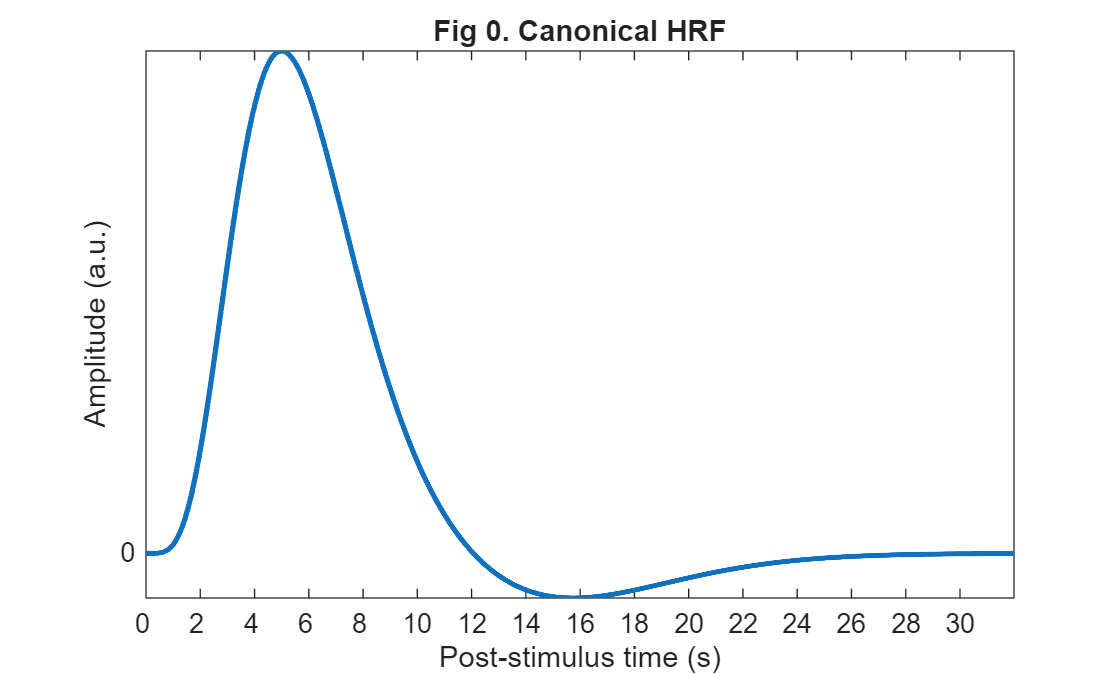

dt = 0.01; % time resolution (does not have to equal TR)
HRF = canonical_HRF(dt); % See General Functions at end
pst = dt*[1:length(HRF)]' - dt; % post-stimulus time (PST)
figure, plot(pst,HRF,'LineWidth',2);
axis([0 max(pst) min(HRF) max(HRF)])
set(gca,'YTick',[0],'XTick',[0:2:max(pst)],'XTickLabel',[0:2:max(pst)])
xlabel('Post-stimulus time (s)'); ylabel('Amplitude (a.u.)')
title('Fig 0. Canonical HRF')

However, the precise shape of the BIR varies across individuals, across brain states (e.g., with versus without drugs) and even across brain regions within the same individual and state. For this reason, the HRF is often estimated by fitting multiple temporal basis functions, though it has been argued that three such functions (dimensions) are sufficient to capture the majority of variability in the BIR [[Henson et al, 2024]](https://doi.org/10.1002/hbm.70043).

Early event-related fMRI experiments used long SOAs, in order to allow the BIR to return to baseline between stimulations (like in analysis of event-related potentials, ERPs). However, this is not necessary if the BIRs to successive events summate in linear manner, in which case it is generally more efficient, as we shall see below, to use shorter SOAs. One exception is if there are only a limited number of stimuli. In this case, longer SOAs can be more efficient simply because they entail longer scanning sessions, and hence more scans and therefore degrees of freedom (dfs) for statistical power. The effect of nonlinearities on efficiency (i.e, saturation at short SOAs) is covered later.

Subsequent fMRI experiments presented stimuli more rapidly, but interspersed them randomly with 'fixation trials' (what are called 'null events' here) and counterbalanced the order of each trial-type. This allows a very simple analysis method (developed in the ERP field) called 'selective averaging' [[Dale & Buckner, 1997]](https://doi.org/10.1002/(sici)1097-0193(1997)5:5%3C329::aid-hbm1%3E3.0.co;2-5). However, this analysis is a special case of more general linear deconvolution methods that can be implemented within the GLM, using for example a 'Finite Impulse Response' (FIR) temporal basis set. Indeed, such linear convolution can be achieved without needing the order of trial-types to be counterbalanced. 

In the efficiency demonstrations below, we will assume that the BIR is captured by a canonical HRF, so that all that needs to be estimated is its amplitude, i.e, scaling (except for the section on detection power versus estimation efficiency).

## General Advice

### Scan for as long as possible

This advice is of course conditional on the participant's comfort and ability to perform the task satisfactorily (my experience is that participants can perform a task comfortably for between 50-80mins, with breaks, within the MRI environment). Longer is better because the power of a statistical inference depends primarily on the dfs, and the dfs depend on the number of scans (volumes). One might therefore think that reducing the TR will also increase your power: This is true to a certain extent, though the "effective" dfs depend on the temporal autocorrelation of the sampled data (i.e, 100 scans rarely mean 100 independent observations), so there is a limit to the power increase afforded by TRs less than approximately 2s (though shorter TRs do allow you to estimate the noise better, by virtue of less aliasing of biorhythms, as explained in Section 1.1.5 below).

Having said this, if you are only interested in group results (i.e, extrapolating from a random sample of participants to a population), then the statistical power normally depends more heavily on the number of participants than the number of scans per participant. In other words, you are likely to have more power with 100 volumes on 20 participants, than with 400 volumes on 5 participants, given that inter-participant variability tends to exceed inter-scan variability. Nonetheless, there are practical issues, like the preparation time necessary to position the participant in the scanner, that mean that 100 volumes on 20 participants takes more total time than 400 volumes on 5 participants. One strategy is therefore to run several different experiments on each participant while they are in the scanner.

### Keep the participant as busy as possible

This refers to the idea that "deadtime" - time during which the participant is not engaged in the task of interest - should be minimised. Again, there may of course be psychological limits to the participant's performance (e.g, they may need rests), but apart from this, factors such as the ISI/ITI should be kept as short as possible (even within blocks of trials). The only situation where you might want longer intervals is if you want to measure the shape of the BIR, or some kind of "inter-stimulus baseline". From a cognitive perspective though, baseline is rarely meaningful (see Common Question IV regarding null events below).

You can stop the scanner to give participants a break (rest). Keep in mind that breaks in scanning reduce the efficiency of any temporal filtering during analysis (since the data no longer constitute a single timeseries), and can introduce potential "session" effects [[McGonigle et al, 2000]](http://www.ncbi.nlm.nih.gov/entrez/query.fcgi?cmd=Retrieve&db=pubmed&dopt=Abstract&list_uids=10860798&query_hl=9). Nonetheless, breaking the task into mulitple "runs" can be necessary, e.g., for cross-validation in MVPA (for which the data from each run need to be independent).

### Do not contrast trials that are far apart in time

One problem with fMRI is that there is a lot of low-frequency noise. This has various causes, from aliased biorhythms to gradual changes in physical parameters (e.g, ambient temperature). Thus any "signal" (induced by your experiment) that is low-frequency may be difficult to distinguish from background noise. Many analysis packages high-pass filter fMRI data (i.e, remove low-frequency components). Since contrasts between trials that are far apart in time correspond to low-frequency effects, they can be filtered out.

A typical high-pass cutoff is 0.01 Hz, based on the observation that the amplitude as a function of frequency, f, for a participant at rest has a "1/f + white noise" form (see Section 1.1.5), in which amplitude has effectively plateaued for frequencies above approximately 0.01 Hz (the inflection point of the "1/f" and "white" noise components). When summing over frequencies (in a statistical analysis), the removal of frequencies below this cut-off will increase the signal-to-noise ratio (SNR), provided that most of the signal is above this frequency (the model residuals are also more likely to be "white", i.e, have equal amplitude across frequencies, an assumption of most parametric statistics).

In the context of blocked designs, the implication is not to use blocks that are too long. For two, alternating conditions, for example, block lengths of more than 50s would cause the majority of signal (i.e, that at the fundamental frequency of the square-wave alternation) to be removed with a highpass cutoff of 0.01 Hz. In fact, the optimal block length in such an alternating design, regardless of any highpass filtering, is approx 16s (as we will see below). This problem of low-frequency noise also means that one should avoid using many conditions of which the important contrasts only involve a subset (see Common Question III below).

### Randomise the order, or inter-trial interval, of trials close together in time

As will be explained below, in order to be sensitive to differences between trials close together in time (e.g, less than 20s), one either 1) uses a fixed SOA but varies the order of different trial-types (conditions), or 2) constrains their order but varies the SOA. Thus a design in which two trials alternate every 4s is very inefficient for detecting the difference between them (as explained below). One could either randomise their order (keeping the SOA fixed at 4s), or vary their SOA (keeping the alternating order). The same logic applies to trials containing multiple neural components, as explained later.

## 1. Univariate analysis (no trial-to-trial variability)

We begin by considering the efficiency for the univariate case of single voxel, in which the true response is identical to each trial of the same type. In fact, we start with the simple question of detecting the response for a single event-type versus the inter-event baseline.

### 1.1 Signal-processing Perspective

Given that we can treat fMRI volumes as comprising a timeseries, some intuition can be gained from adopting a signal-processing perspective [[Josephs & Henson, 1999]](https://doi.org/10.1098/rstb.1999.0475). We assume what is called a "linear convolution" model, in which the predicted fMRI series is obtained by convolving a neural function (e.g. a delta function for an event) with an assumed HRF. The effect of this convolution is best understood by a series of examples. For an event occurring every 16s, the results of convolution using the canonical HRF in Fig 0 above are shown by this code:

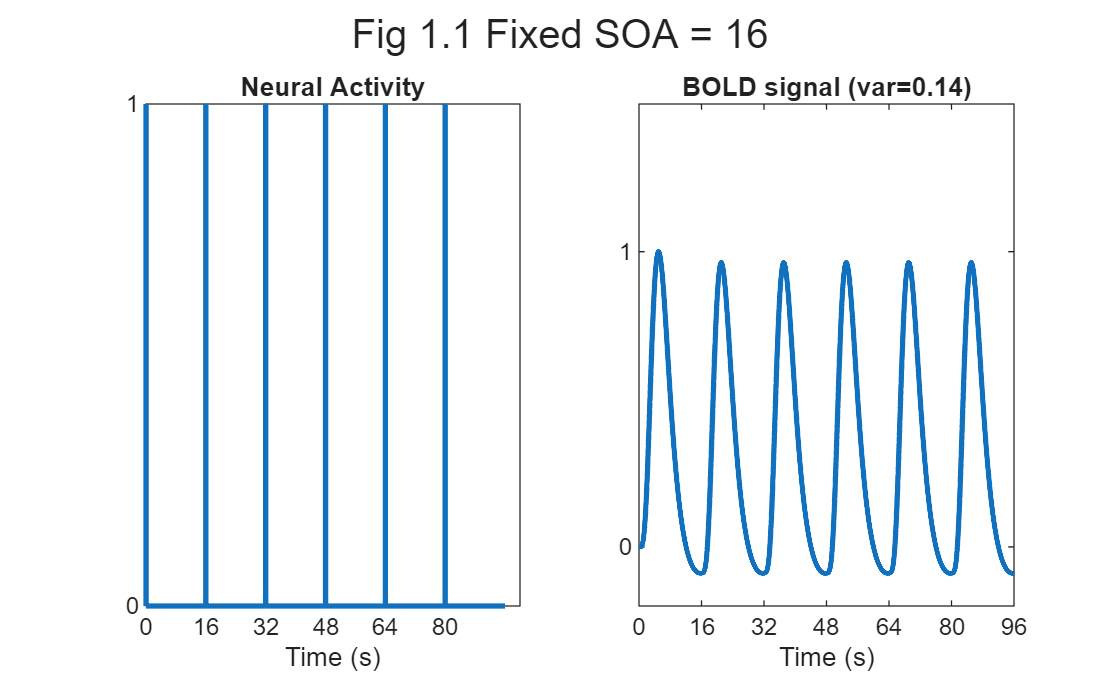

SOA = 16;
total_time = 6*SOA;      % Just 6 events for illustration
num_smp = total_time/dt; % (keeping dt from previous cell)

t = [0:(num_smp-1)]'*dt;     % absolute times
u = zeros(num_smp,1);        % hypothetical neural activity
u(1:round(SOA/dt):end) = 1;  % simulated delta function at each onset
s = lconv(u,HRF);            % BOLD timeseries predicted by linear convolution (lconv.m at end)

figure,sgtitle(sprintf('Fig 1.1 Fixed SOA = %d', SOA))
subplot(1,2,1)
stairs(t,u,'LineWidth',2);
set(gca,'YTick',[0 1],'XTick',[0:SOA:5*SOA]); xlabel('Time (s)'); title('Neural Activity')

subplot(1,2,2)
plot(t,s,'LineWidth',2);
xtick = [0:SOA:6*SOA];
set(gca,'YTick',[0 1],'XTick',xtick); xlabel('Time (s)'); 
title(sprintf('BOLD signal (var=%3.2f)',var(s)));
axis([0 total_time -0.2 1.5])

The basic idea behind maximising efficiency is to maximise the "energy" of the predicted fMRI timeseries. This is simply the sum of squared signal values at each scan. It is also proportional to the variance of the signal. In other words, to detect the signal in the presence of background noise (not shown), we want to maximise the variability of that signal. A signal that varies little will be difficult to detect in the presence of noise.

Now the above example (a fixed SOA of 16s) is not particularly efficient, as we shall see. What if we present the stimuli much faster, e.g, every 4s? 

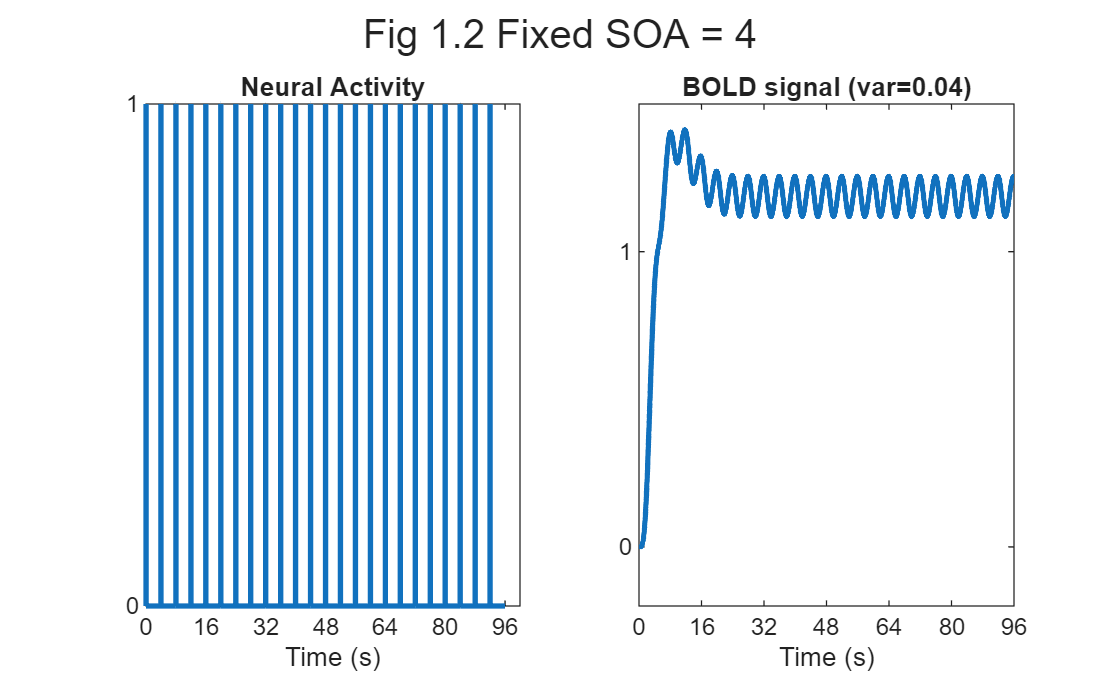

SOA = 4;
u = zeros(num_smp,1);       % hypothetical neural activity
u(1:round(SOA/dt):end) = 1; % simulated delta function at each onset
s = lconv(u,HRF);           % predicted BOLD signal timeseries

figure,sgtitle(sprintf('Fig 1.2 Fixed SOA = %d', SOA))
subplot(1,2,1)
stairs(t,u,'LineWidth',2);
set(gca,'YTick',[0 1],'XTick',xtick); xlabel('Time (s)'); title('Neural Activity')

subplot(1,2,2)
plot(t,s,'LineWidth',2);
set(gca,'YTick',[0 1],'XTick',xtick); xlabel('Time (s)'); 
title(sprintf('BOLD signal (var=%3.2f)',var(s)));
axis([0 total_time -0.2 1.5])

Because the BIRs to successive events now overlap considerably, we end up an initial build-up (transient) followed by small oscillations around a "raised baseline". Although the overall signal is high, its variance is low, and the majority of stimulus energy will be lost after highpass filtering (particularly after removal of the mean, i.e lowest frequency). So this is an even less efficient design.

#### 1.1.1. Randomised event-related design

What if we vary the SOA randomly? Let's say we have a minimal SOA (SOAmin) of 4s, but only a 50% probability of an event every SOAmin. This is called a stochastic design (and one way to implement it is simply to randomly intermix an equal number of "null events", as shown later):

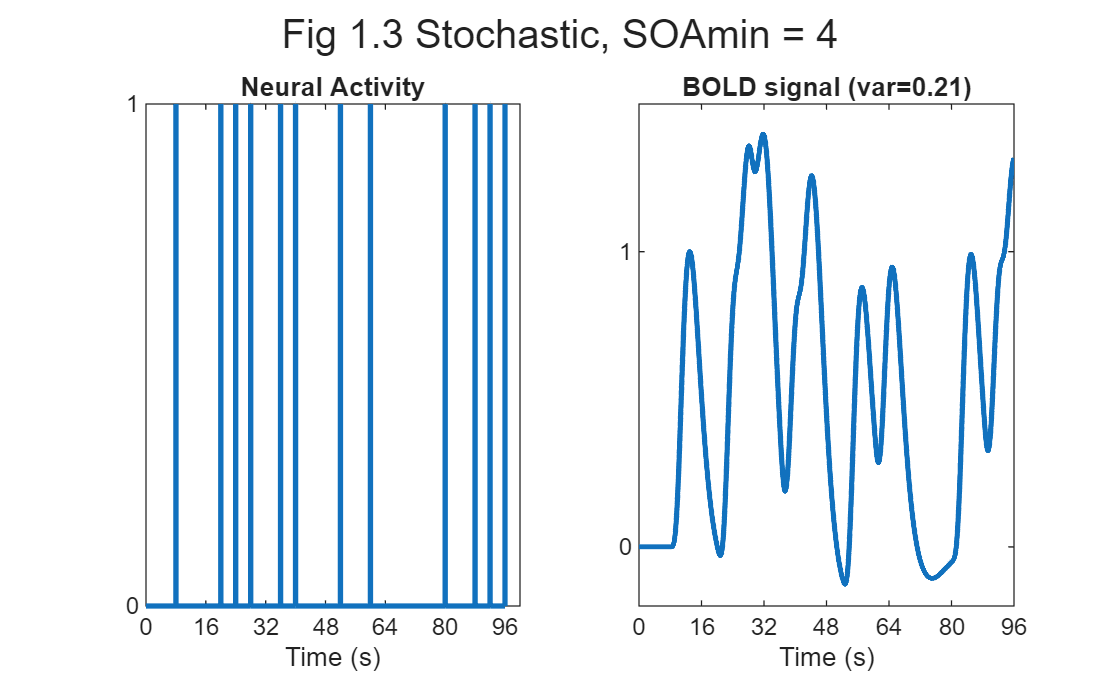

rng(2) % Set random seed just to get nice example
SOAmin = 4;
% 50% probability of event every SOAmin:
% r = find(rand(1,round(total_time/SOAmin)) > 0.5);
% ... or ensure exactly half of SOAmins within total_time are events
r = randperm(round(total_time/SOAmin));
r = r(1:round(length(r)/2));

u = zeros(num_smp,1);       % hypothetical neural activity
u(r*SOAmin/dt) = 1;         % simulated delta function at each onset
s = lconv(u,HRF);           % predicted BOLD signal timeseries

figure,sgtitle(sprintf('Fig 1.3 Stochastic, SOAmin = %d', SOAmin))
subplot(1,2,1)
stairs(t,u,'LineWidth',2);
set(gca,'YTick',[0 1],'XTick',xtick); xlabel('Time (s)'); title('Neural Activity')

subplot(1,2,2)
plot(t,s,'LineWidth',2);
set(gca,'YTick',[0 1],'XTick',xtick); xlabel('Time (s)'); 
title(sprintf('BOLD signal (var=%3.2f)',var(s)));
axis([0 total_time -0.2 1.5])

Though there are only half as many stimuli compared to Fig 1.2, this is a more efficient design (compare signal variances in "var" values). This is because there is a much larger variability in the signal (and we know ''how'' this signal varies, even though we generated the event sequence randomly, because we know the specific sequence that resulted).

#### 1.1.2. Blocked designs

We could also vary the SOA in a more systematic fashion. We could have runs of events, followed by runs of no (null) events. This corresponds to a blocked design. For example, we could have blocks of 4 stimuli presented every 4s, alternating with 16s of rest:

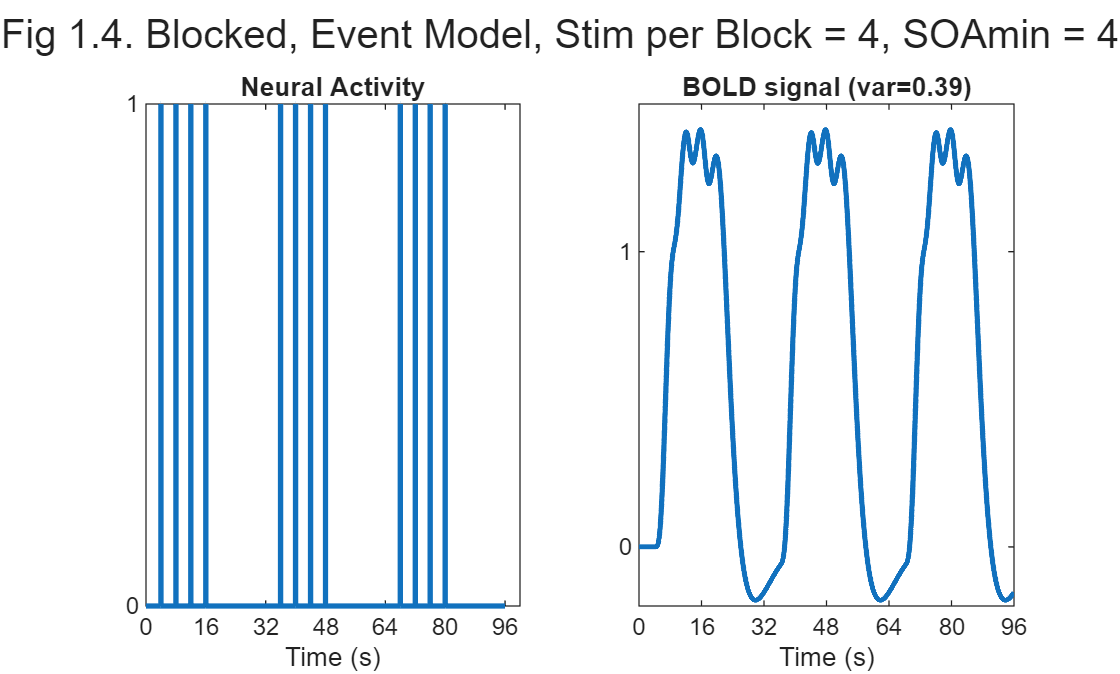

stim_per_block = 4;
r = kron([1 0], ones(1,stim_per_block));
r = find(repmat(r, 1, ceil(total_time/(length(r)*SOAmin))));
u = zeros(num_smp,1);       % hypothetical neural activity
u(r*SOAmin/dt) = 1;         % simulated delta function at each onset
s = lconv(u,HRF);           % predicted BOLD signal timeseries

figure, sgtitle(sprintf('Fig 1.4. Blocked, Event Model, Stim per Block = %d, SOAmin = %d', stim_per_block, SOAmin))
subplot(1,2,1)
stairs(t,u,'LineWidth',2);
set(gca,'YTick',[0 1],'XTick',xtick); xlabel('Time (s)'); title('Neural Activity')

subplot(1,2,2)
plot(t,s,'LineWidth',2);
set(gca,'YTick',[0 1],'XTick',xtick); xlabel('Time (s)'); 
title(sprintf('BOLD signal (var=%3.2f)',var(s)));
axis([0 total_time -0.2 1.5])

This is even more efficient than the previous stochastic design. To see why, we shall consider the Fourier transform of these timeseries. Firstly however, note that, with such short SOAs (approx 4s or less), the predicted fMRI timeseries for such a blocked design is very similar to what would obtain if neural activity were sustained throughout the block (i.e, during the ISI as well). Indeed, if you think each stimulus engages neural activity for up to 4 seconds afterwards (rather than a few hundred of milliseconds), this "epoch" model is a more accurate characteristation of neural activity than the "event" model considered so far. Epochs correspond to square-wave (or "box-car") functions:

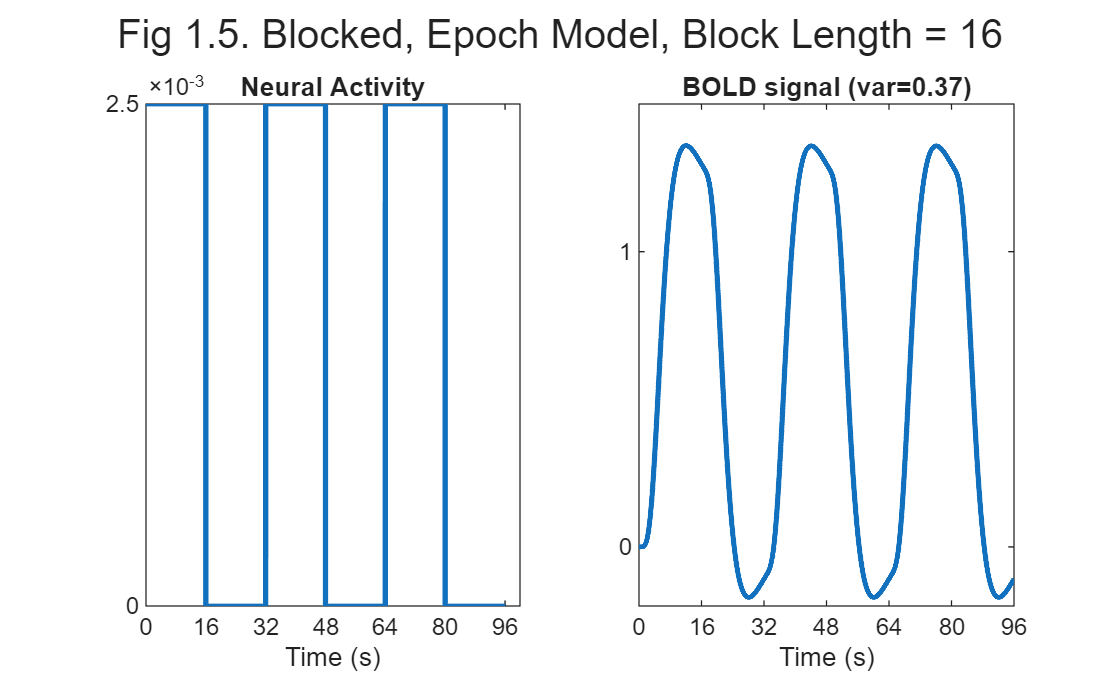

block_length = 16;
scaling = dt/SOAmin; % to approx match scale of event model 
u = kron([1 0]'*scaling, ones(block_length/dt,1)); % epoch model
u = repmat(u, round(total_time/(length(u)*dt)), 1);
s = lconv(u,HRF);   % predicted BOLD signal timeseries

figure, sgtitle(sprintf('Fig 1.5. Blocked, Epoch Model, Block Length = %d', block_length))
subplot(1,2,1)
plot(t,u,'LineWidth',2);
set(gca,'YTick',[0 scaling],'XTick',xtick); xlabel('Time (s)'); title('Neural Activity')

subplot(1,2,2)
plot(t,s,'LineWidth',2);
set(gca,'YTick',[0 1],'XTick',xtick); xlabel('Time (s)'); 
title(sprintf('BOLD signal (var=%3.2f)',var(s)));
axis([0 total_time -0.2 1.5])

(Note the signal variance cannot be compared directly across the event and epoch models because their relative scaling is somewhat arbitary.)

#### 1.1.3. Fourier Transform and HRF as a filter

Now if we take the Fourier transform of the neural activity, we get the neural spectrum in left panel of Fig 1.6 below. The amplitude spectrum (square-root of the "power spectrum") of the square-wave neural function has a dominant frequency corresponding to its "fundamental" frequency (Fo = 1/(16+16)s = 0.0312 Hz), plus a series of "harmonics" (3Fo, 5Fo, ... etc) of progressively decreasing amplitude. The fundamental frequency corresponds to the frequency of a sinusoidal that best matches the basic on-off alternation; the harmonics capture the "sharper" edges of the square-wave function relative to this fundamental sinusoid.

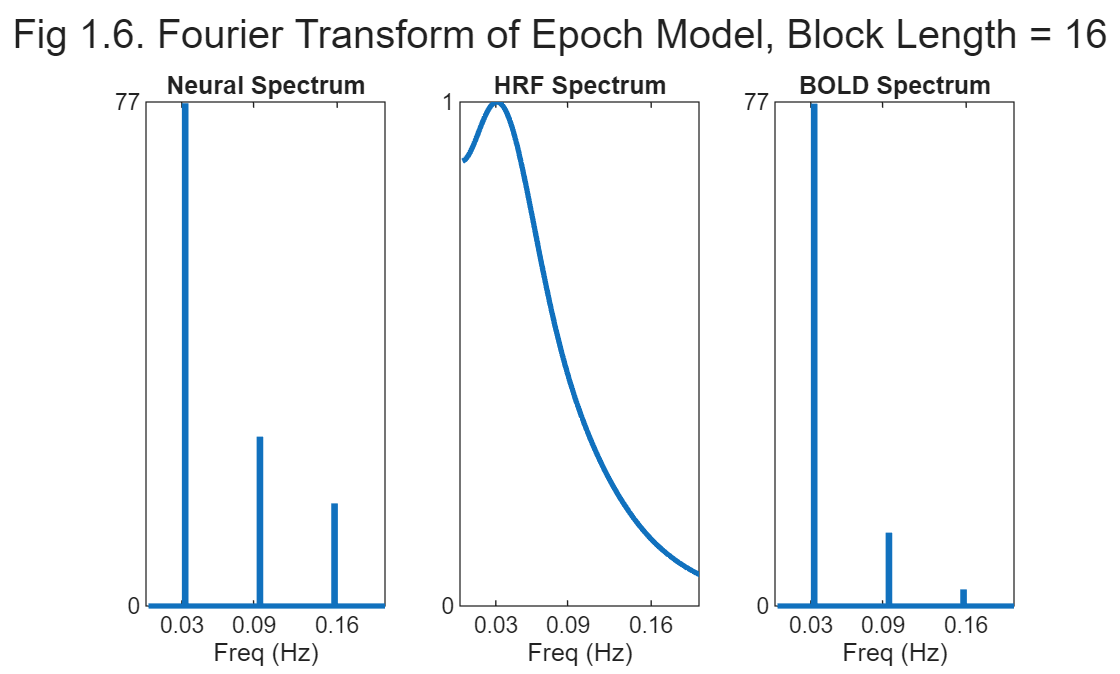

uu = repmat(u,10,1);            % increase duration to increase freq resolution
[a,f] = amp_spec(uu,dt);        % using function below
max_a = ceil(max(a(2:end)));    % (ignoring DC, ie 0 Hz)

figure, sgtitle(sprintf('Fig 1.6. Fourier Transform of Epoch Model, Block Length = %d', block_length))
subplot(1,3,1)
stairs(f(2:end),a(2:end),'LineWidth',2); % Ignore 0 Hz
F0 = 1/(2*block_length);
ftick = round([F0:2*F0:0.2],2);
set(gca,'YTick',[0 max_a],'XTick',ftick); xlabel('Freq (Hz)'); title('Neural Spectrum')
axis([0 0.2 0 max_a])

padding = (length(uu) - length(HRF))/2; % to equate freq res for HRF and u
[ha,f] = amp_spec(HRF,dt,padding);
ha = ha/max(ha(2:end)); % normalise

subplot(1,3,2)
plot(f(2:end),ha(2:end),'LineWidth',2);
set(gca,'YTick',[0 1],'XTick',ftick); xlabel('Freq (Hz)'); title('HRF Spectrum')
axis([0 0.2 0 1])

% A convolution in time is equal to multiplication in frequency (uncomment to check)
% s = lconv(u,HRF); % predicted BOLD signal timeseries
% [ba,f] = amp_spec(s,dt);
ba = a.*ha;

subplot(1,3,3)
stairs(f(2:end),ba(2:end),'LineWidth',2);
set(gca,'YTick',[0 max_a],'XTick',ftick); xlabel('Freq (Hz)'); title('BOLD Spectrum')
axis([0 0.2 0 max_a])

The Fourier transform does not affect the data or conclusions, so why bother? Well it offers a slightly different perspective. Foremost, a convolution in time is equivalent to a multiplication in frequency space. In this way, we can regard the neural activity as our original data and the HRF as a filter. If we take the Fourier transform of the HRF itself, we get the middle panel in Fig 1.6, which indicates a peak around 1/30s ~ 0.03Hz, and a diminishing tail. This filter will therefore "pass" low frequencies, but attenuate higher frequencies (which is why it is sometimes called a "lowpass filter" or "temporal smoothing kernel"). This can be seen in the right panel of Fig 1.6, where the higher harmonics have been attenuated (equivalent to the smoothed edges in right panel of Fig 1.5). In other words, the majority of the signal is "passed" by the HRF filter, which is why this 20s on/off epoch design is quite efficient, for example compared to the fixed SOA=4s design in Fig 1.2, where most of the high-frequency information is lost after HRF convolution.

#### 1.1.4. What is the most efficient design of all?

We are now in a position to answer the question: what is the most efficient design of all? The answer is one in which neural activity is modulated in a sinusoidal fashion (e.g, sinusoidal change in the luminance of a visual stimulus), with a frequency that matches the peak of the amplitude spectrum of the BIR. Assuming the BIR matches the HRF used here, this would be 0.0312Hz. Note that after convolution with the HRF, the predicted BOLD signal is also sinusoidal, just with a phase-shift relative to the neural activity. The sinusoidal modulation places **all** the stimulus energy at this single peak frequency, shown by the single line in frequency space in Fig 1.7, so no signal is lost. 

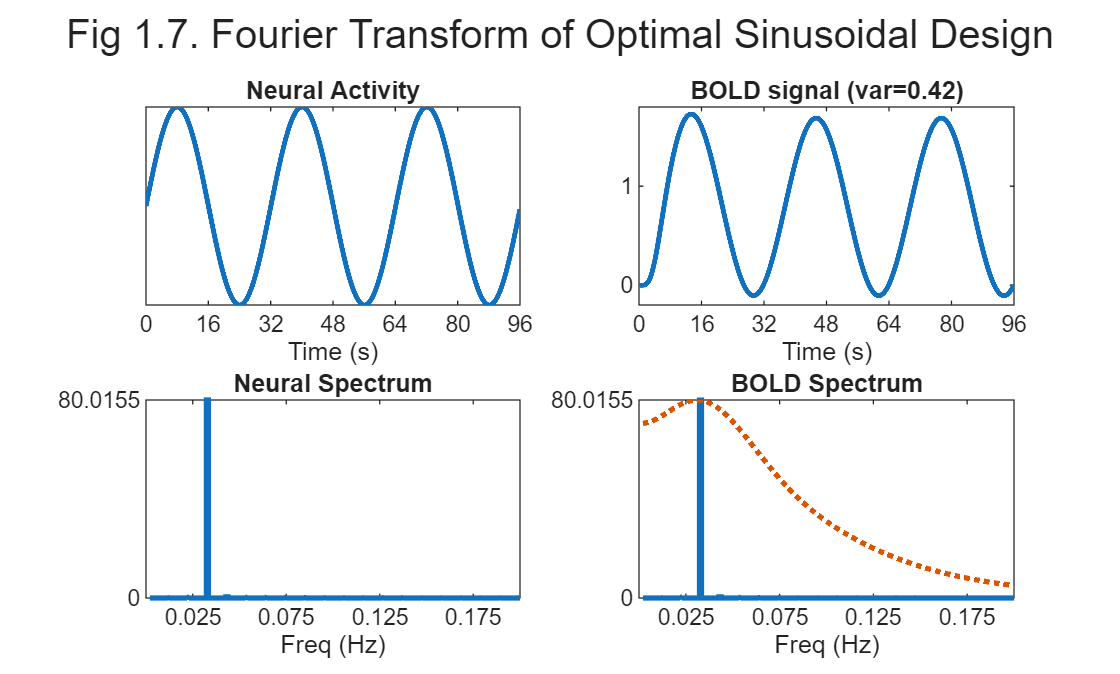

eu = u; % copying previous epoch model so can match energy
f = 0.0312; % peak frequency of HRF
t = [0:(length(eu)-1)]'*dt;
u = (sin(2*pi*t*f)+1)/2;
u = u*scaling;
u = u*sum(eu.^2)/sum(u.^2); % normalise so same total energy as epoched case
s = lconv(u,HRF);           % predicted BOLD signal timeseries

figure, sgtitle('Fig 1.7. Fourier Transform of Optimal Sinusoidal Design')
subplot(2,2,1)
plot(t,u,'LineWidth',2); 
set(gca,'YTick',[0 ceil(scaling)],'XTick',xtick); xlabel('Time (s)'); title('Neural Activity')
axis([0 total_time min(u) max(u)])

subplot(2,2,2)
plot(t,s,'LineWidth',2); 
set(gca,'YTick',[0 1],'XTick',xtick); xlabel('Time (s)'); 
title(sprintf('BOLD signal (var=%3.2f)',var(s)));
axis([0 total_time -0.2 1.8])

[a,f] = amp_spec(repmat(u,10,1),dt); % increase duration to increase freq resolution
max_a = max(a(2:end));

subplot(2,2,3)
stairs(f(2:end),a(2:end),'LineWidth',2); % Ignore 0 Hz
ftick = [0.025:0.05:0.2];
set(gca,'YTick',[0 max_a],'XTick',ftick); xlabel('Freq (Hz)'); title('Neural Spectrum')
axis([0 0.2 0 max_a])

ba = a.*ha;

subplot(2,2,4)
stairs(f(2:end),ba(2:end),'LineWidth',2);
hold on
plot(f(2:end),ha(2:end)*max(ba(2:end)),'LineWidth',2, 'LineStyle',':');
set(gca,'YTick',[0 max_a],'XTick',ftick); xlabel('Freq (Hz)'); title('BOLD Spectrum')
axis([0 0.2 0 max_a])

#### 1.1.5. High-pass filter to remove noise

So far we have been talking about maximising the signal variance. But efficiency also depends on the noise, i.e., signal-to-noise ratio (SNR). The noise in fMRI data is not "white" (equal across all frequencies), but tends to have more energy at lower-frequencies, following an approximate "1/f" distribution. The low-frequency noise reflects scanner drift (eg, changes in ambient temperature), gradual head motion and aliased biorhythms.

Aliasing occurs when a signal is not sampled at a higher enough rate, such that it "wraps round" from a high frequency into a lower frequency in the sampled data. In fMRI, we sample the BOLD signal every TR. According to the Nyquist theorem, any frequencies above half the sampling rate will be aliased, ie above 0.5Hz if TR=1s. Thus contributions to the BOLD signal like those from the pulse will appear as low-frequency noise (since the heart-rate is normally >1Hz). This is illustrated in Fig 1.8.

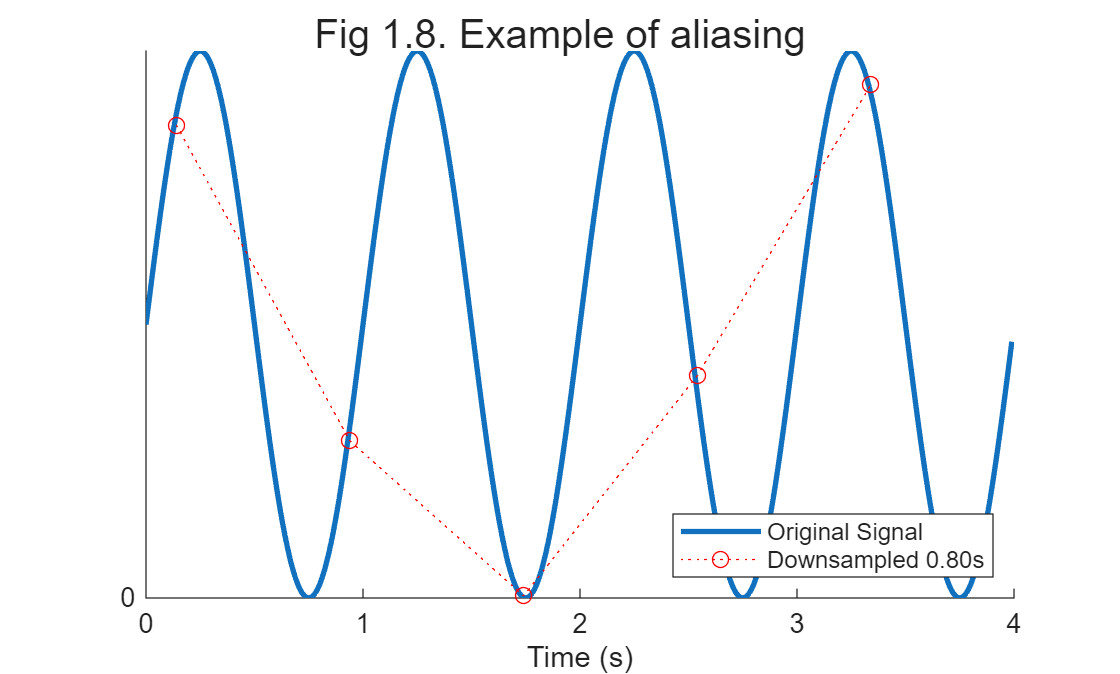

f = 1; % Eg heart-rate (60 bpm)
total_time = 4; 
t = [0:dt:(total_time-dt)]'; 
u = sin(2*pi*t*f)+1;                        % original signal
TR = 0.8;                                   % slower than Nyquist limit (every 0.5s)
s = round([((1/f)/8):TR:total_time]/dt)+1;  % down-sampled signal

figure, sgtitle(sprintf('Fig 1.8. Example of aliasing')), hold on
plot(t,u,'LineWidth',2); 
xtick = [0:(1/f):total_time];
set(gca,'YTick',[0],'XTick',xtick); xlabel('Time (s)'); 
axis([0 total_time min(u) max(u)])
plot(s*dt,u(s),':or')
legend({'Original Signal',sprintf('Downsampled %3.2fs',TR)},'Location','SouthEast')

As a result, the typical 1/f "noise" spectrum for someone at rest in the scanner is shown in the blue line in Fig 1.9. The red line shows the signal power from a sinusoidal modulation of neural activity with a period of 32sec (as in Fig 1.7). The green area shows low frequencies that would be removed by a high-pass filter with cut-off 1/100 Hz. The SNR is the sum over all frequencies, which would be larger after high-pass filtering (i.e, by removing power below 0.01Hz).

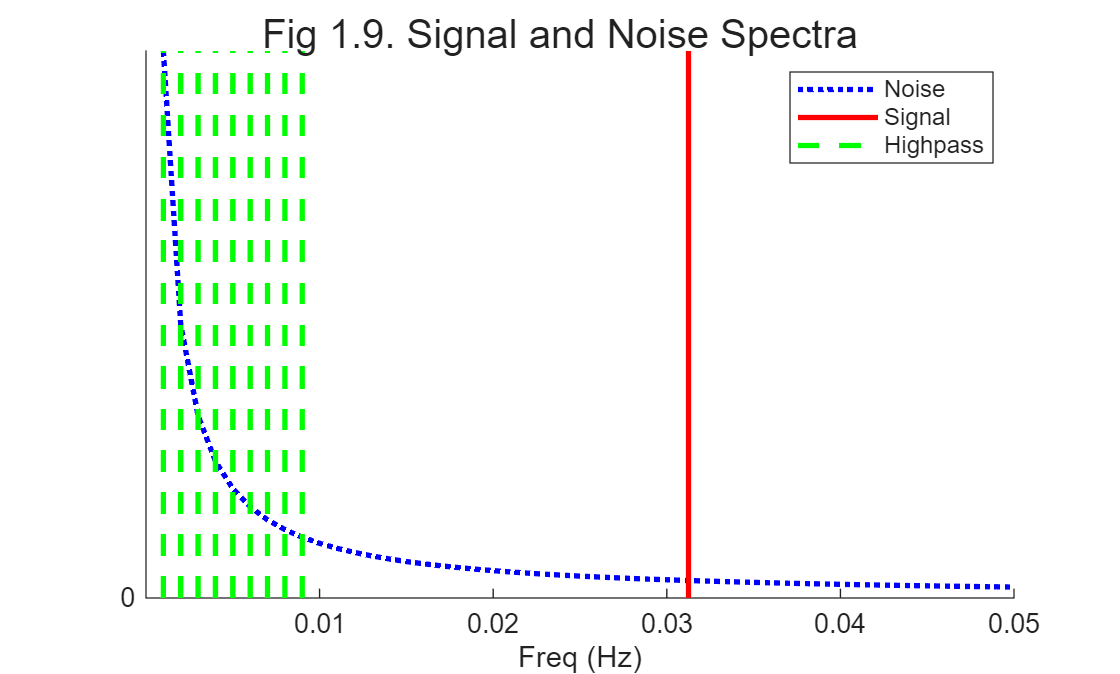

df = 0.001;                   % To increase freq resolution
f = [df:df:0.05];
ftick = [0.01:0.01:0.05];
a = 1./f;                     % 1/f amplitude spectrum

figure, sgtitle(sprintf('Fig 1.9. Signal and Noise Spectra')), hold on
plot(f, a, 'LineWidth',2, 'LineStyle',':', 'Color',[0 0 1]);
set(gca,'YTick',[0],'XTick',ftick); xlabel('Freq (Hz)'); 
line([1/32 1/32]',[0 1000]','LineWidth',2,'Color',[1 0 0]);

hpf = 1/100;                  % High-pass filter cut-off
for h = 1:length(find(f<=hpf))
    line([f(h) f(h)]',[0 1000]','LineWidth',2, 'LineStyle','--', 'Color',[0 1 0]);
end
axis([0 0.05 0 1/df])
legend({'Noise','Signal','Highpass'})


fa = a; fa(find(f<hpf))=0;
fprintf('SNR without highpass = %3.2f\nSNR with highpass = %3.2f', 1000/sum(a), 1000/sum(fa))

SNR without highpass = 0.22
SNR with highpass = 0.60

Because the filtering is commutative, we can combine the highpass filter with the lowpass filter inherent in the HRF to create a single "band-pass" filter (or "effective HRF", [[Josephs & Henson, 1999]](https://doi.org/10.1098/rstb.1999.0475)). This is shown in Fig 1.10 below, in which the highpass filter reflects the "chunk" of low-frequencies has been removed from the HRF filter in the middle panel. As a consequence, in this example of slow, on-off design with blocks of 24 trials every 4s, a large amount of power at the fundamental frequency (1/(2*24*4)=0.005 Hz) is lost, and so efficiency is reduced (e.g. in variance of signal).

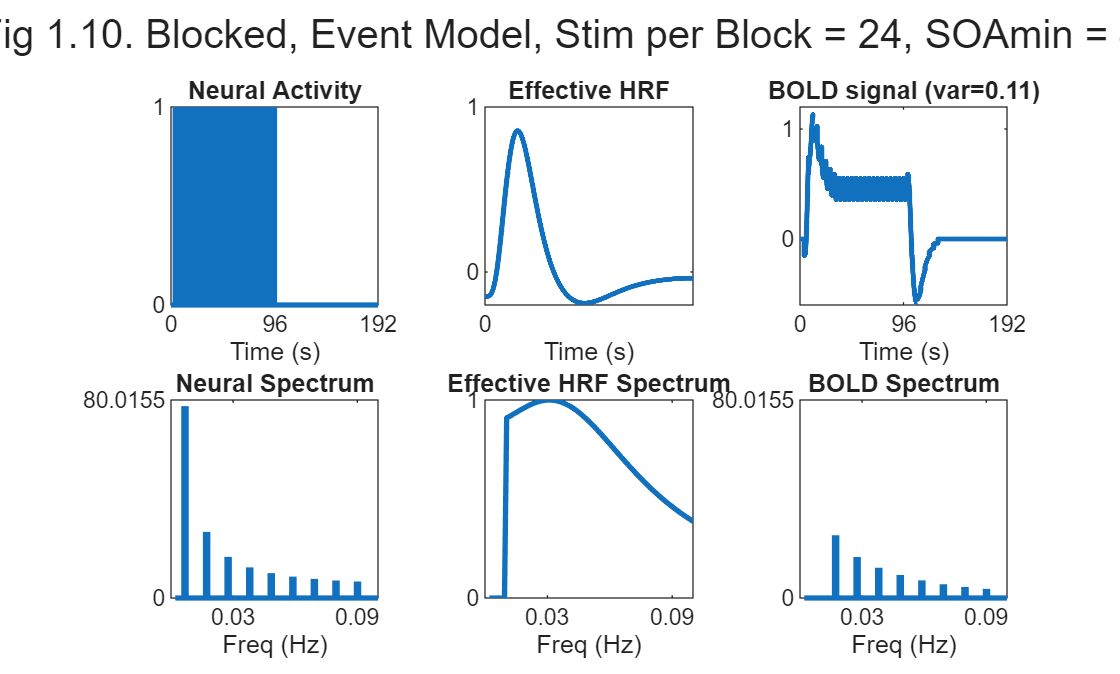

SOAmin = 4; 
total_time = 192; t = [0:dt:(total_time-dt)]'; num_smp = length(t);
stim_per_block = 24; 

r = kron([1 0]', ones(stim_per_block,1));
r = find(repmat(r, ceil(total_time/(length(r)*SOAmin)), 1));
u = zeros(num_smp,1);       % hypothetical neural activity
u(r*SOAmin/dt) = 1;         % simulated delta function at each onset

xtick = [0:stim_per_block*SOAmin:total_time];

figure, sgtitle(sprintf('Fig 1.10. Blocked, Event Model, Stim per Block = %d, SOAmin = %d', stim_per_block, SOAmin)), hold on
subplot(2,3,1)
stairs(t,u,'LineWidth',2);
set(gca,'YTick',[0 1],'XTick',xtick); xlabel('Time (s)'); title('Neural Activity')
axis([0 total_time 0 1])

hHRF = highpass(HRF, 0.01, 1/dt);

subplot(2,3,2)
plot(pst,hHRF,'LineWidth',2);
set(gca,'YTick',[0 1],'XTick',xtick); xlabel('Time (s)'); 
title(sprintf('Effective HRF'));
axis([0 32 -0.2 1])

s = lconv(u,hHRF); % predicted BOLD signal timeseries

subplot(2,3,3)
plot(t,s,'LineWidth',2);
set(gca,'YTick',[0 1],'XTick',xtick); xlabel('Time (s)'); 
title(sprintf('BOLD signal (var=%3.2f)',var(s)));
axis([0 total_time -0.6 1.2])

ha(find(f<hpf)) = 0; % remove low-frequencies (ie highpass part)

[a,f] = amp_spec(repmat(u, 5, 1),dt); % 5 replications to match length of HRF

subplot(2,3,4)
stairs(f(2:end),a(2:end),'LineWidth',2); % Ignore 0 Hz
F0 = 1/(2*block_length);
ftick = round([F0:2*F0:0.2],2);
set(gca,'YTick',[0 max_a],'XTick',ftick); xlabel('Freq (Hz)'); title('Neural Spectrum')
axis([0 0.1 0 max_a])

subplot(2,3,5)
plot(f(2:end),ha(2:end),'LineWidth',2);
set(gca,'YTick',[0 1],'XTick',ftick); xlabel('Freq (Hz)'); title('Effective HRF Spectrum')
axis([0 0.1 0 1])

ba = a.*ha;

subplot(2,3,6)
stairs(f(2:end),ba(2:end),'LineWidth',2);
set(gca,'YTick',[0 max_a],'XTick',ftick); xlabel('Freq (Hz)'); title('BOLD Spectrum')
axis([0 0.1 0 max_a])

The above example illustrates the general point that blocked designs are only efficient when the block length is not too long, with approx 16s-on, 16s-off being optimal (assuming BIR matches the canonical HRF). Block durations of up to 50s-on, 50s-off can also be ok (if the noise does not "take off" until 0.01Hz, and highpass filter reflects this). For block durations  longer than this (or contrasts between two of many different types of 50s-blocks, see Common Question III), you could decreases the highpass filter cut-off, but you will then be in danger of being swamped by low-frequency noise.

Finally, we can return to consider what happens in a stochastic design like that in Fig 1.3. The effect of the randomised SOA is to "spread" the signal energy across a range of frequencies, as shown in Fig 1.11. Some of the high and low frequency components are lost to the "effective HRF" band-pass filter, but much is passed, making it a reasonably efficient design.

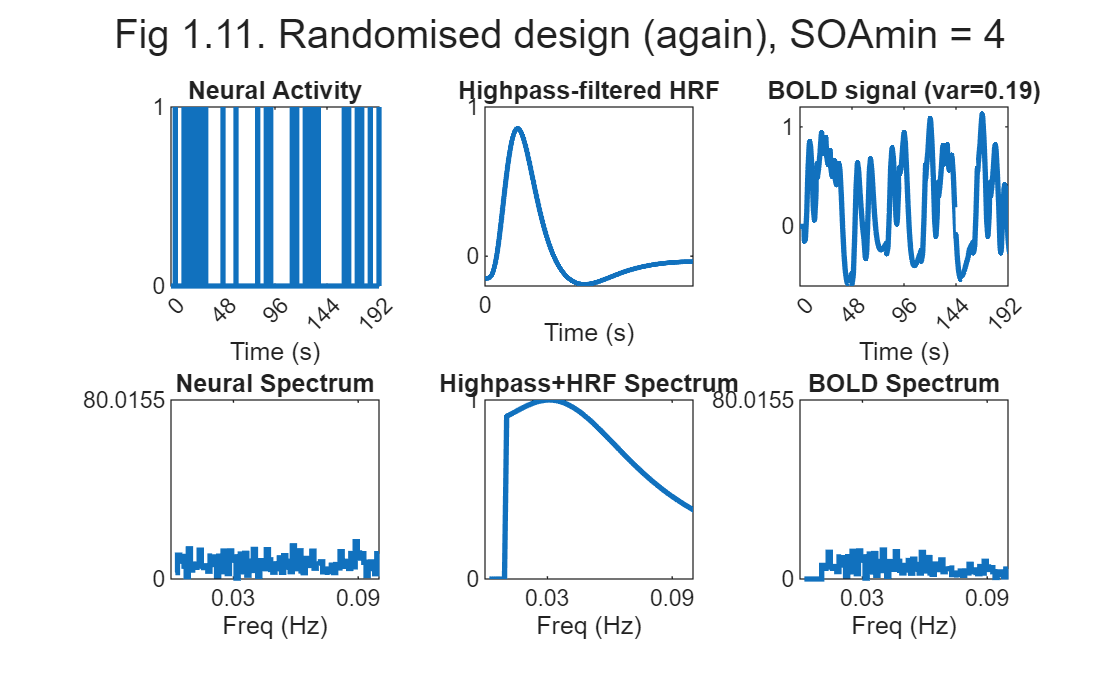

total_time = 2*(length(ha)+1)*dt; % to match freq resolution of HRF
t = [0:dt:(total_time-dt)]'; num_smp = length(t);
r = randperm(round(total_time/SOAmin));
r = r(1:round(length(r)/2));
u = zeros(num_smp,1);   % hypothetical neural activity
u(r*SOAmin/dt) = 1;     % simulated delta function at each onset

xtick = [0:12*SOA:48*SOA];

figure, sgtitle(sprintf('Fig 1.11. Randomised design (again), SOAmin = %d', SOAmin)) ;hold on
subplot(2,3,1)
stairs(t,u,'LineWidth',2);
set(gca,'YTick',[0 1],'XTick',xtick); xlabel('Time (s)'); title('Neural Activity')
axis([0 192 0 1]) % 192 to match previous plots above

subplot(2,3,2)
plot([0:dt:length(hHRF)*dt-dt],hHRF,'LineWidth',2);
set(gca,'YTick',[0 1],'XTick',xtick); xlabel('Time (s)'); 
title(sprintf('Highpass-filtered HRF'));
axis([0 32 -0.2 1])

s = lconv(u,hHRF);  % predicted BOLD signal timeseries

subplot(2,3,3)
plot(t,s,'LineWidth',2);
set(gca,'YTick',[0 1],'XTick',xtick); xlabel('Time (s)'); 
title(sprintf('BOLD signal (var=%3.2f)',var(s)));
axis([0 192 -0.6 1.2])

[a,f] = amp_spec(u,dt); % 5 replications to match length of HRF

subplot(2,3,4)
stairs(f(2:end),a(2:end),'LineWidth',2); % Ignore 0 Hz
F0 = 1/(2*block_length);
ftick = round([F0:2*F0:0.2],2);
set(gca,'YTick',[0 max_a],'XTick',ftick); xlabel('Freq (Hz)'); title('Neural Spectrum')
axis([0 0.1 0 max_a])

subplot(2,3,5)
plot(f(2:end),ha(2:end),'LineWidth',2);
set(gca,'YTick',[0 1],'XTick',ftick); xlabel('Freq (Hz)'); title('Highpass+HRF Spectrum')
axis([0 0.1 0 1])

ba = a.*ha;

subplot(2,3,6)
stairs(f(2:end),ba(2:end),'LineWidth',2);
set(gca,'YTick',[0 max_a],'XTick',ftick); xlabel('Freq (Hz)'); title('BOLD Spectrum')
axis([0 0.1 0 max_a])

### 1.2 Mathematics (statistics)

Efficiency is actually defined mathematically as follows. The equation for a T-statistic is:

T_value = @(c,B) c'*B / sqrt(var(c'*B))

T_value = function_handle with value:
    @(c,B)c'*B/sqrt(var(c'*B))


where c is a column vector of contrast weights (e.g, c=[1 -1]' to contrast two conditions) and B is a column vector of parameter estimates (regression coefficients or "Betas"). Assuming that the error, estimated from the model residuals, is drawn independently for each observation from the same Gaussian distribution ("iid"), then some maths leads to the denominator of the T-statistic being equal to:

Var_cBvar = @(c,X,sigma) sigma^2 * (c'*inv(X'*X)*c)

Var_cBvar = function_handle with value:
    @(c,X,sigma)sigma^2*(c'*inv(X'*X)*c)


where X is the design matrix (model) and sigma^2 is an estimate of the error variance derived from the sum of squares of the residuals. So, in order to maximise our T-values, we need to minimise the above quantity. Assuming that the error (noise) is independent of our experimental design (though see [[Mechelli et al. 2023]](https://doi.org/10.1016/s1053-8119(02)00040-x)), this corresponds to maxmising the statistical quantity known as "efficiency":

efficiency = @(c,X) 1/trace(c'*inv(X'*X)*c)

efficiency = function_handle with value:
    @(c,X)1/trace(c'*inv(X'*X)*c)


The "trace" operator is needed when the contrast c is a matrix (ie, F-contrast) rather than a vector (ie, T-contrast). In the examples in Section 1.1, there was only one condition and hence one column of X, being estimated against baseline (inter-stimulus interval), so c=1. This meant that the efficiency was proportional to (X'X), which is equivalent to the signal variance (energy) reported in that Section.

Note that efficiency has no units; it is a relative measure. It depends on the scaling of the design matrix and the scaling of the contrasts. It is unlikely to map simply onto real T-values; though we expect it to be at least monotonically related to them. Thus all we can really say is that one design/contrast combination is more efficient than another.

Below we apply this equation to situations with 2 conditions, where we can compare the efficiency for a differential contrast (c=[1 -1]') relative to a main effect (c=[1 1]'). But first, we will digress to consider "detection power" versus "estimation efficiency" for a single condition, which relates to different HRF models.

#### 1.2.1. Detection Power versus Estimation Efficiency (digression)

Some authors have distinguished "detection power" from "estimation efficiency" [[Liu et al, 2001]](https://doi.org/10.1006/nimg.2000.0728), which boils down to what HRF is assumed. So far, we have been considering "detection power", on the assumption that the real BIR in the data matches our assumed canonical HRF. In the context of the GLM, this means that the regressors in our design matrix X are created by convolving our specified onsets with the canonical HRF, or a single "temporal response function". To allow for variability in the shape of the BIR across brain regions and individuals, it is also possible to use multiple temporal response functions. One popular choice is an "Finite Impulse Response" (FIR) basis set, which consists of mini-epochs every few seconds. With a bin-size of 2s, for example, the BIR shape from 0-24s can be estimated by 12 basis functions capturing every 2s of post-stimulus time (0-2, 2-4, 4-6, etc). It turns out that the most efficient design for detecting an effect with an assumed HRF ("detection power", e.g., a blocked design, eg 16s on/off; as explained in previous section) differs from the most efficient design for estimating the shape of the HRF ("estimation efficiency", which turns out to be a randomised SOA design, as shown below). To see this, we can create different design matrice using different temporal response functions, and compare them using the above equation:

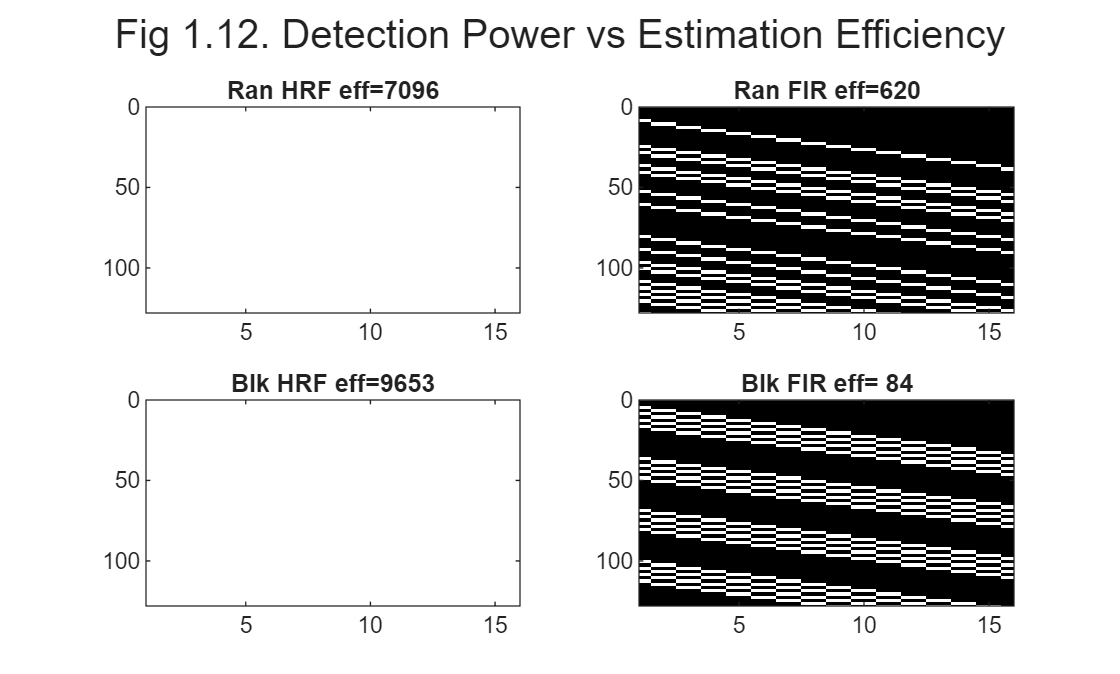

rng(2) % Just to get nice visualisation
SOAmin = 4; dt = 1; % Assume TR=dt, ie sampled every 1s
total_time = SOAmin*32;
r = randperm(round(total_time/SOAmin));
r = r(1:round(length(r)/2));
ran_u = zeros(num_smp,1);       % hypothetical neural activity for randomised design
ran_u(r*SOAmin/dt) = 1;         % simulated delta function at each onset

stim_per_block = 4;
r = kron([1 0]', ones(stim_per_block,1));
r = find(repmat(r, 1, ceil(total_time/(length(r)*SOAmin))));
blk_u = zeros(num_smp,1);       % hypothetical neural activity for blocked design
blk_u(r*SOAmin/dt) = 1;         % simulated epoch function (=delta function every dt)

HRF = canonical_HRF(dt);

bin_size = 2;
num_bins = (length(HRF)*dt)/bin_size;
FIR = kron(eye(num_bins), ones(bin_size/dt,1));
FIR = FIR * sum(HRF)/sum(FIR(:,1)); % equate basis function height

X_ran_HRF = detrend(lconv(ran_u,HRF),0);  % mean-correct to avoid need for constant term in X 
X_blk_HRF = detrend(lconv(blk_u,HRF),0);
X_ran_FIR = detrend(lconv(ran_u,FIR),0); 
X_blk_FIR = detrend(lconv(blk_u,FIR),0);

figure, sgtitle('Fig 1.12. Detection Power vs Estimation Efficiency')
subplot(2,2,1)
imagesc(X_ran_HRF), colormap('gray'); xlim([1 num_bins]); ylim([0 128/dt]);
title(sprintf('Ran HRF eff=%3.0f',100*efficiency(1, X_ran_HRF)))
subplot(2,2,2)
imagesc(X_ran_FIR), colormap('gray'); xlim([1 num_bins]); ylim([0 128/dt]);
title(sprintf('Ran FIR eff=%3.0f',100*efficiency(eye(num_bins), X_ran_FIR)))
subplot(2,2,3)
imagesc(X_blk_HRF), colormap('gray'); xlim([1 num_bins]); ylim([0 128/dt]);
title(sprintf('Blk HRF eff=%3.0f',100*efficiency(1, X_blk_HRF)))
subplot(2,2,4)
imagesc(X_blk_FIR), colormap('gray'); xlim([1 num_bins]); ylim([0 128/dt]);
title(sprintf('Blk FIR eff=%3.0f',100*efficiency(eye(num_bins), X_blk_FIR)))

Thus the detection power (efficiency using a single assumed HRF; two left panels of Fig 1.12) is higher for blocked than randomised designs, whereas the estimation efficiency (efficiency using an FIR basis set; two right panels of Fig 1.12) is higher for randomised deisgns. In other words, if you want to estimate the shape of the BIR, don't use a blocked design; or conversely, if you have a blocked design, then use a fixed HRF rather than multiple temporal response functions. We can see the problem when we add some noise and actually estimate the BIR using an FIR basis set: the true BIR (green in Fig 1.13) is less noisy when estimated from a randomised design (blue in Fig 1.13) than from a blocked design (red in Fig 1.13).

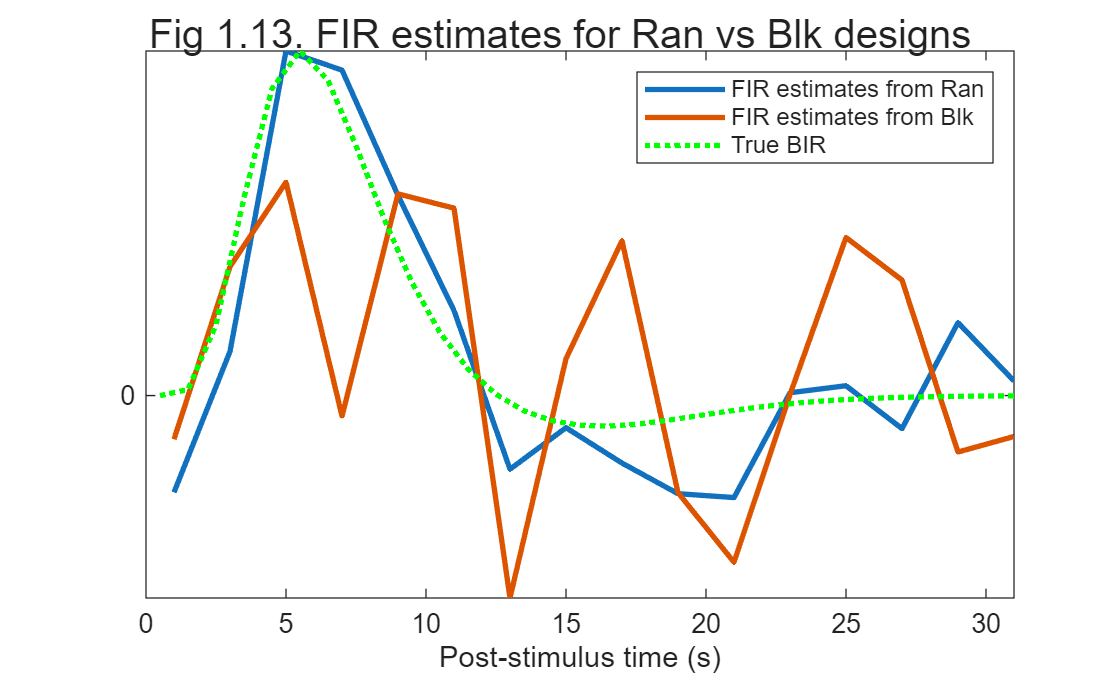

rng(3) % Just to get nice visualisation
noise = randn(size(ran_u)); % Zero-mean Gaussian noise
y_ran = X_ran_HRF + noise;
y_blk = X_blk_HRF + noise; % add same noise to both designs

BIR = nan(num_bins,2);
BIR(:,1) = pinv(X_ran_FIR)*y_ran; % These are GLM OLS estimates of Betas
BIR(:,2) = pinv(X_blk_FIR)*y_blk;

figure, sgtitle('Fig 1.13. FIR estimates for Ran vs Blk designs')
pst = [0.5:1:num_bins]*bin_size;
plot(pst, BIR, 'LineWidth', 2);
HRF = canonical_HRF(1); HRF = HRF*max(BIR(:,1))/max(HRF);
hold on, plot([0.5:1:32], HRF, 'g:', 'LineWidth', 2)
axis([0 max(pst) min(BIR(:)) max(BIR(:))])
set(gca,'YTick',[0])
xlabel('Post-stimulus time (s)');
legend({'FIR estimates from Ran','FIR estimates from Blk','True BIR'})

#### 1.2.2. Two randomised conditions

In general, we can parametrise any event-related design in terms of the probability, ''p(i,h)'', of a specific event-type ''i=1...N'' occurring every SOAmin, as a function of the history ''h'', a vector of the previous ''j=1...M'' event-types. These probabilities can be captured in terms of an (M+1)-dimensional "transition matrix" (TM). A TM is best illustrated by examples. For the simple case of a random ordering of two event-types, A and B, the first-order (M=1) 2x2 TM is given below. The function "gen_stim" uses this matrix to produce a stochastic sequence of a certain length:

TM = [    0.5 0.5;      % Probability of A following A = probability of A following B = 0.5
          0.5 0.5];     % Probability of B following A = probability of B following B = 0.5
num_trl = 128;
v = genstim(TM, num_trl); % v is vector of trial-types
c = repmat('A',1,num_trl); c(find(v==2))='B'; fprintf('First 24 trials: %s\n',c(1:24)) 

First 24 trials: AAAABABABAABABAABAABBAAB


In other words, there is a 50% probability of A or B, regardless of the previous event-type. (This transition matrix is of course rather redundant, but shown this way in order to compare with subsequent examples.)

We can now generate a design matrix for this experiment. Note that we can add the highpass filter to the design matrix using a "discrete cosine transform" (DCT), which is a set of sinusoidals of decreasing periods up to the high-pass cutoff we want (using the "dct" function below). This is equivalent to high-passing filtering the data (and model), and incorporates the potential loss of dfs (important for any subsequent statistics).

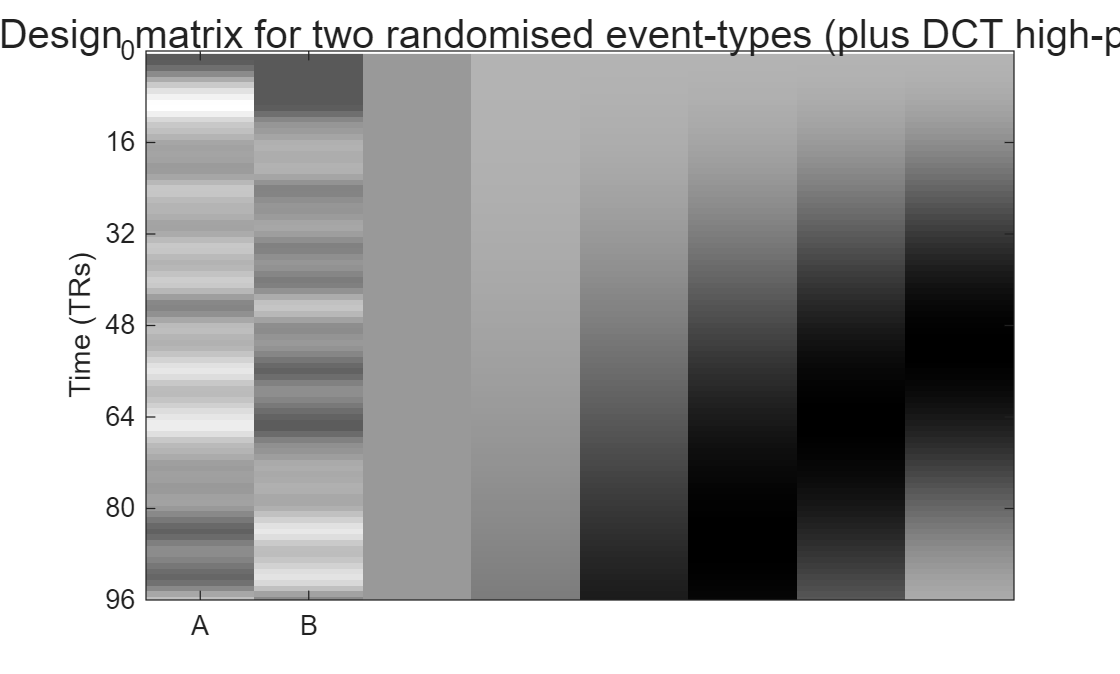

SOAmin = 2; dt = 0.1; HRF = canonical_HRF(dt);
num_types = size(TM,2);           % Number of conditions
num_smp = num_trl*SOAmin/dt;
u = zeros(num_smp,num_types);     % hypothetical neural activity
for c = 1:num_types
    ind = find(v==c)-1;
    u(ind*SOAmin/dt+1,c) = 1;
end

s = lconv(u,HRF);                 % predicted BOLD signal timeseries

TR = 1; TR_bins = round(TR/dt);
X = s((TR_bins/2):TR_bins:end,:); % downsample each TR (at middle of TR, eg middle slice in time)

H0 = 0.01; % Highpass cut-off in Hz
K = dct(size(X,1), H0, TR);
X = [X K];

figure, sgtitle('Fig 1.14. Design matrix for two randomised event-types (plus DCT high-pass filter)')
imagesc(X), colormap('gray'); ylim([0 96]);
set(gca,'Ydir','reverse')
set(gca,'XTick',[1 2],'XTickLabel',{'A','B'}); xlim([0.5 size(X,2)+0.5])
set(gca,'YTick',[0:16:96]), ylabel('Time (TRs)')

The above steps of convolving with an HRF, down-sampling each TR and adding a high-pass filter will be wrapped into the function "gen_X" from now on.

Now there are two contrasts that might be of interest. First, we might be interested in the "common effect" of A and B versus the interstimulus baseline, ie c= [+1 +1]'. Second, we might be interested in the difference in amplitude of responses elicited by each condition, which corresponds to the "differential effect" or c= [+1 -1]'. These two contrasts will have different efficiencies, which we can plot as a function of SOA in Fig 1.15:

SOAmin = [2:2:32];
eff = nan(length(SOAmin),2);
num_trl = 2^10;              % To get robust estimate
stim = genstim(TM, num_trl); % Ensure same stimulus ordering for all SOAs
for s = 1:length(SOAmin)
    v = stim(1:round(num_trl * SOAmin(1)/SOAmin(s))); % To ensure same number of trials per SOA
    fprintf('%d events at SOA %d (total time = %d)\n', length(v), SOAmin(s), length(v)*SOAmin(s))
    [X,K,KX] = gen_X(v, SOAmin(s), HRF, TR, H0);      % KX is highpassed version of X
    eff(s,1) = efficiency([1  1]', KX);
    eff(s,2) = efficiency([1 -1]', KX);
end

1024 events at SOA 2 (total time = 2048)
512 events at SOA 4 (total time = 2048)
341 events at SOA 6 (total time = 2046)
256 events at SOA 8 (total time = 2048)
205 events at SOA 10 (total time = 2050)
171 events at SOA 12 (total time = 2052)
146 events at SOA 14 (total time = 2044)
128 events at SOA 16 (total time = 2048)
114 events at SOA 18 (total time = 2052)
102 events at SOA 20 (total time = 2040)
93 events at SOA 22 (total time = 2046)
85 events at SOA 24 (total time = 2040)
79 events at SOA 26 (total time = 2054)
73 events at SOA 28 (total time = 2044)
68 events at SOA 30 (total time = 2040)
64 events at SOA 32 (total time = 2048)


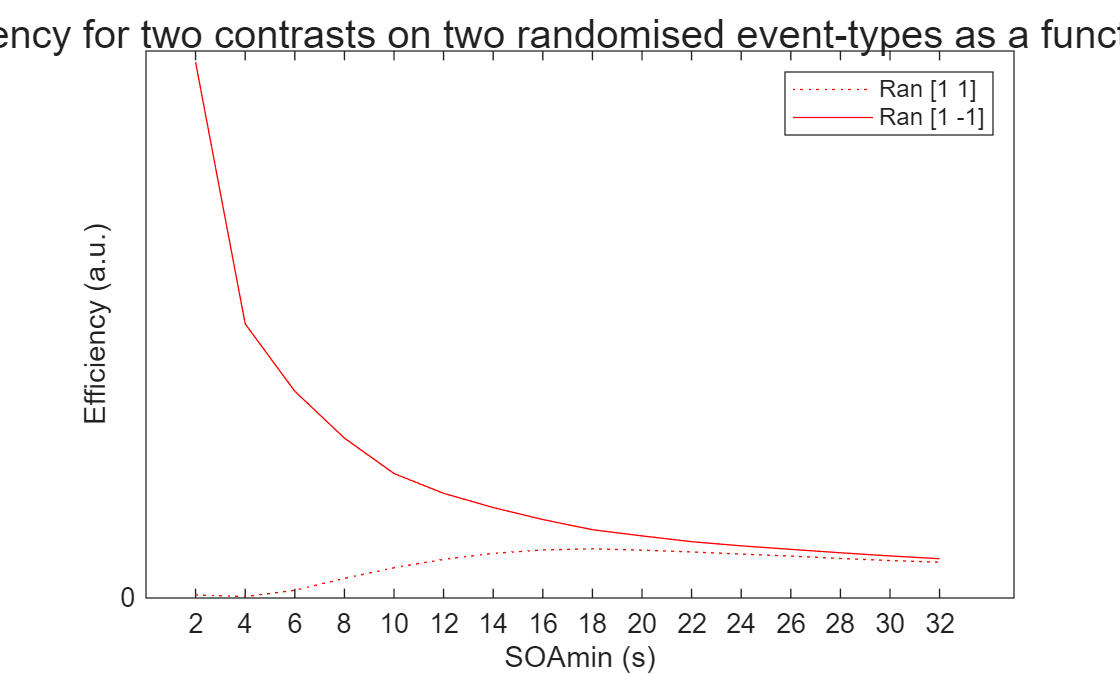


figure, sgtitle('Fig 1.15. Efficiency for two contrasts on two randomised event-types as a function of SOAmin')
p = plot(SOAmin,eff);
linestyles = {':';'-'};
linecolors = {'r';'r'};
[p(:).LineStyle] = linestyles{:};
[p(:).Color] = linecolors{:};
legend({'Ran [1 1]','Ran [1 -1]'})
set(gca,'YTick',[0],'XTick', SOAmin); xlabel('SOAmin (s)'); ylabel('Efficiency (a.u.)')

Note that efficiency will always increase with more datapoints (TRs), so it is important to equate these when comparing efficiencies as a function of SOA (i.e., to assume total experimental time is fixed). Importantly, the optimal SOA clearly differs for the two contrasts: For the common effect, the optimal SOA is approx 18s; whereas for the differential effect, the optimal SOA is the shortest SOA possible, at least under the present linear assumptions. In practice, the efficiency for the differential contrast is unlikley to increase indefinitely as the SOA decreases, because at some point the response to successive events will diminish, owing to saturation/habituation. Such nonlinearities are likely to reflect both neural and haemodynamic causes. Nonetheless, when [[Friston et al. 1999]](https://doi.org/10.1006/nimg.1999.0498) estimated such nonlinearities, they found that efficiency still increased with SOAs down to 1s, though declined below that. This suggests that high efficiency can be obtained for SOAmins as low as 1s; indeed [[Burock et al. 1998]](https://doi.org/10.1097/00001756-199811160-00030) still detected significant differential effects with SOAmin=0.5s.

#### 1.2.3. Constraints on SOA or trial order

Sometimes a randomised design is not suitable. For example, one might have two conditions that must alternate for some reason. This would correspond to the simple transition matrix below:

TM = [0 1; 1 0]; % Alternating conditions
stim = genstim(TM, num_trl); % Ensure same stimulus ordering for all SOAs
c = repmat('A',1,num_trl); c(find(stim==2))='B'; fprintf('First 24 trials: %s\n',c(1:24)) 

First 24 trials: BABABABABABABABABABABABA


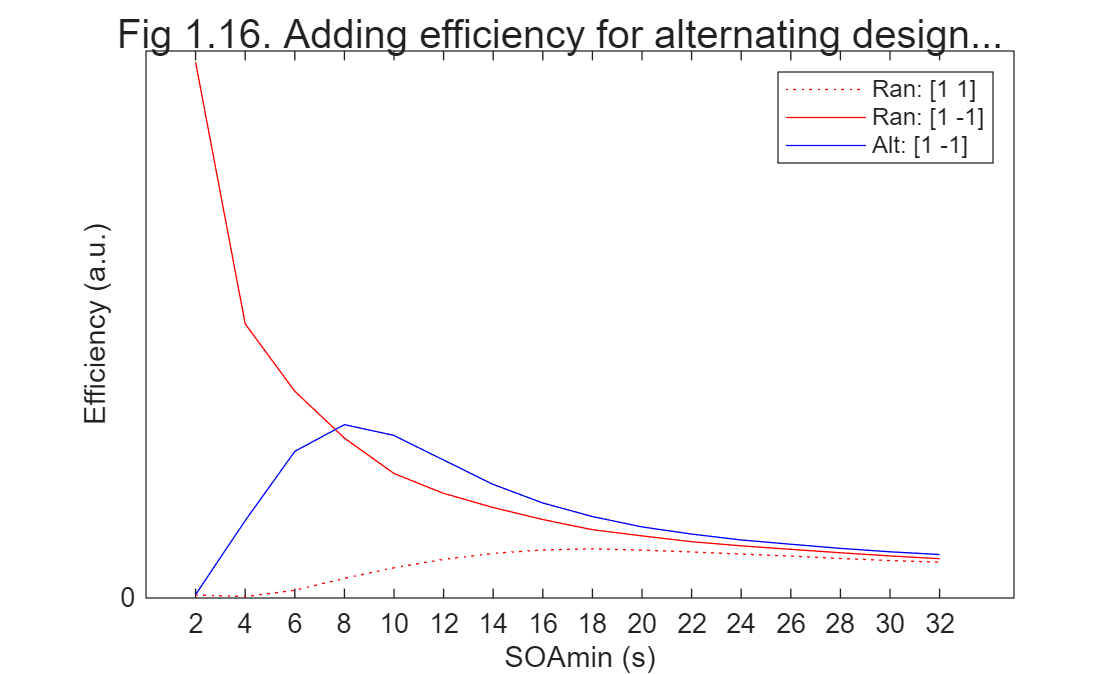

for s = 1:length(SOAmin)
    v = stim(1:round(num_trl * SOAmin(1)/SOAmin(s))); % To ensure same number of trials per SOA
    %fprintf('%d events at SOA %d (total time = %d)\n',length(v),SOAmin(s),length(v)*SOAmin(s))
    [X,K,KX] = gen_X(v, SOAmin(s), HRF, TR, H0);
    eff(s,3) = efficiency([1 -1]', KX);
end

figure, sgtitle('Fig 1.16. Adding efficiency for alternating design...')
p = plot(SOAmin,eff);
linestyles{end+1} = '-';
linecolors{end+1} = 'b';
[p(:).LineStyle] = linestyles{:};
[p(:).Color] = linecolors{:};
legend({'Ran: [1 1]','Ran: [1 -1]', 'Alt: [1 -1]'})
set(gca,'YTick',[0],'XTick', SOAmin); xlabel('SOAmin (s)'); ylabel('Efficiency (a.u.)')

Note that the optimal SOAmin in this case is around 8s. 

In another situations, there may be no constraints on the ordering of event-types, but rather the SOAmin cannot be below, say, 6s (e.g., to give enough time for a participant to respond to each stimulus). Are there stimulus orderings that are more efficiency than full randomisation? Indeed, some pseudorandom designs might help for the differential effect, as shown in Fig 1.17:

clear TM
TM(1,:,:) = [0 1; 0.5 0.5]; % Pseudorandom, ie given AA, must be a B; given AB, equal chance of A/B 
TM(2,:,:) = [0.5 0.5; 1 0]; % Pseudorandom, ie given BB, must be an A; given BA, equal chance of A/B
stim = genstim(TM, num_trl); % Ensure same stimulus ordering for all SOAs
c = repmat('A',1,num_trl); c(find(stim==2))='B'; fprintf('First 24 trials: %s\n',c(1:24)) 

First 24 trials: BAABBABABBABABAABAABAABB


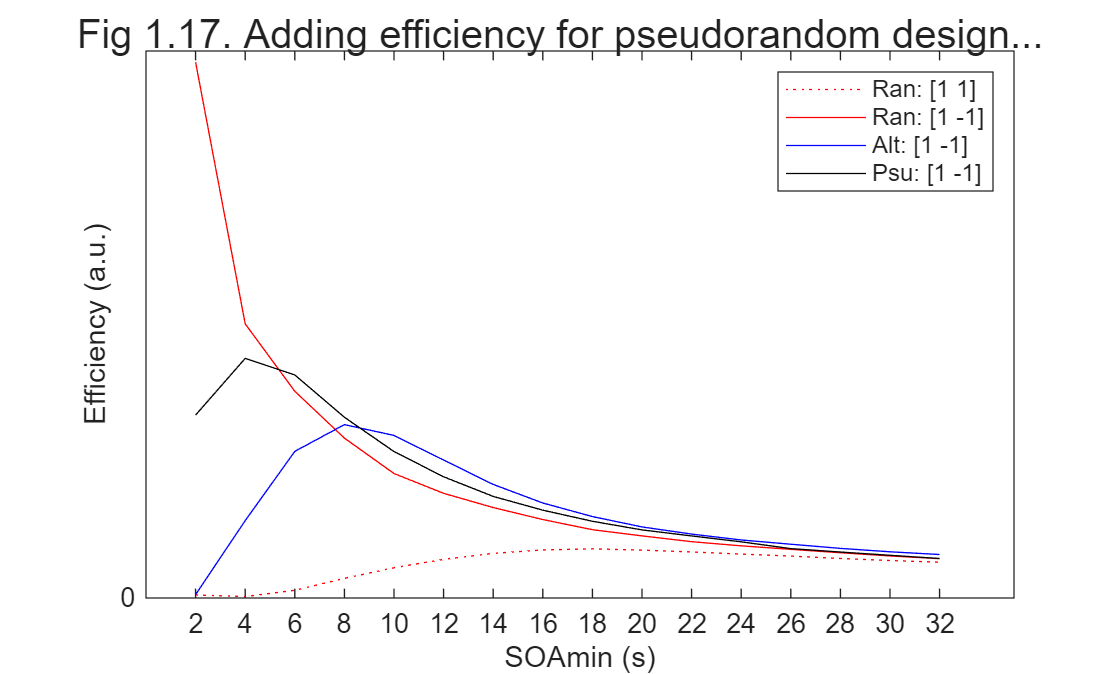

for s = 1:length(SOAmin)
    v = stim(1:round(num_trl * SOAmin(1)/SOAmin(s))); % To ensure same number of trials per SOA
    %fprintf('%d events at SOA %d (total time = %d)\n',length(v),SOAmin(s),length(v)*SOAmin(s))
    [X,K,KX] = gen_X(v, SOAmin(s), HRF, TR, H0);
    eff(s,4) = efficiency([1 -1]', KX);
end

figure, sgtitle('Fig 1.17. Adding efficiency for pseudorandom design...')
p = plot(SOAmin,eff);
linestyles{end+1} = '-';
linecolors{end+1} = 'k';
[p(:).LineStyle] = linestyles{:};
[p(:).Color] = linecolors{:};
legend({'Ran: [1 1]','Ran: [1 -1]', 'Alt: [1 -1]', 'Psu: [1 -1]'})
set(gca,'YTick',[0],'XTick', SOAmin); xlabel('SOAmin (s)'); ylabel('Efficiency (a.u.)')

This design is randomised to first-order, but fully deterministic to second-order. Importantly, its efficiency for detecting the difference between A and B is better than a fully randomised design (or alternating design) for SOAmins between 6-8s. It also has the potential advantage of being less predictable than an alternating design, which might be important for psychological reasons, though whenever structure is introduced into sequences, one should beware of potential conscious or unconscious effects of that structure on brain responses.

#### 1.2.4. Null events

Finally, we can consider the introduction of "null events" (or what are sometimes called "fixation trials"). These simply correspond to an additional event-type that is randomly intermixed with the event-types of interest. Importantly, null events should not entail any detectable change from whatever comprises the interstimulus interval (e.g, a fixation crosshair); they simply provide a convenient way of jittering the SOA between the events of interest. They correspond to transition matrices in which the rows do not sum to 1. 

Why add null events? Well, the answer is that they buy us efficiency for detecting the common effect (e.g, of A and/or B vs. interstimulus baseline) as well as the differential effect, even at short SOAs (though with a small reduction of efficiency for detecting the differential effect). This is shown in the two green lines in Fig 1.18:

clear TM
TM = [1/3 1/3; 1/3 1/3]; % equal probability of A or B or Null event
stim = genstim(TM, num_trl); % Ensure same stimulus ordering for all SOAs
c = repmat('-',1,num_trl); c(find(stim==1))='A'; c(find(stim==2))='B'; fprintf('First 24 trials: %s\n',c(1:24)) 

First 24 trials: AA-BB--B--ABAA-ABB-----A


for s = 1:length(SOAmin)
    v = stim(1:round(num_trl * SOAmin(1)/SOAmin(s))); % To ensure same number of trials per SOA
    fprintf('%d events at SOA %d (total time = %d)\n',length(find(~isnan(v))),SOAmin(s),length(v)*SOAmin(s))
    [X,K,KX] = gen_X(v, SOAmin(s), HRF, TR, H0);
    eff(s,3) = efficiency([1  1]', KX);
    eff(s,4) = efficiency([1 -1]', KX);
end

684 events at SOA 2 (total time = 2048)
336 events at SOA 4 (total time = 2048)
220 events at SOA 6 (total time = 2046)
174 events at SOA 8 (total time = 2048)
134 events at SOA 10 (total time = 2050)
109 events at SOA 12 (total time = 2052)
94 events at SOA 14 (total time = 2044)
83 events at SOA 16 (total time = 2048)
73 events at SOA 18 (total time = 2052)
63 events at SOA 20 (total time = 2040)
54 events at SOA 22 (total time = 2046)
48 events at SOA 24 (total time = 2040)
45 events at SOA 26 (total time = 2054)
41 events at SOA 28 (total time = 2044)
38 events at SOA 30 (total time = 2040)
36 events at SOA 32 (total time = 2048)


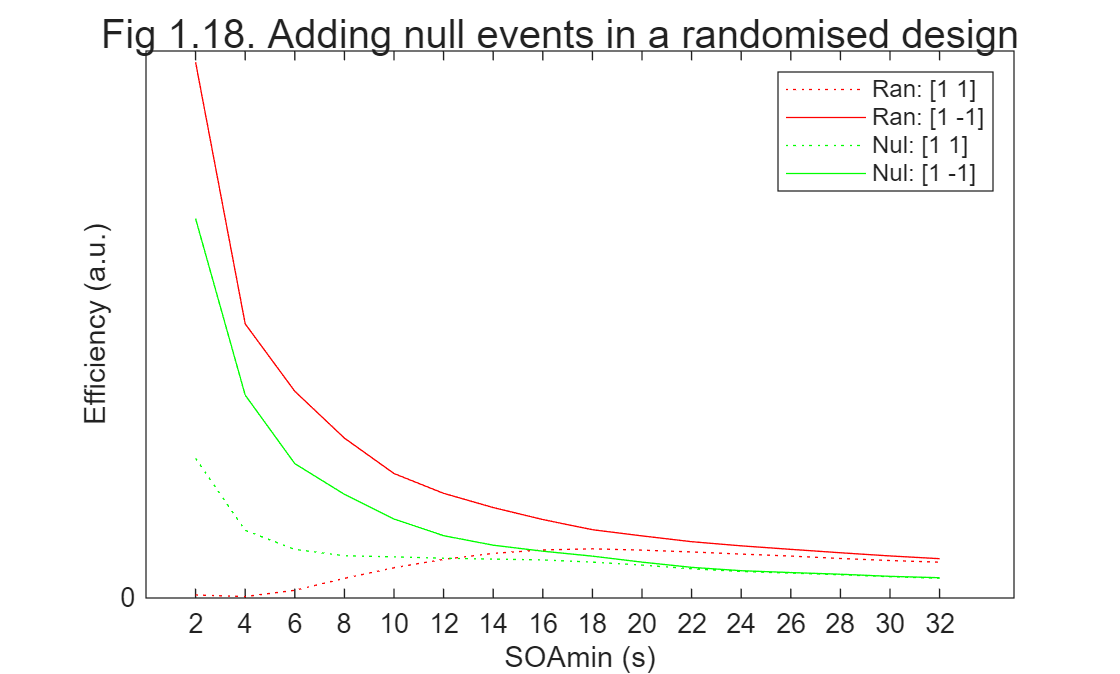


figure, sgtitle('Fig 1.18. Adding null events in a randomised design')
p = plot(SOAmin,eff);
linestyles{3} = {':'};
linecolors{3} = 'g'; linecolors{4} = 'g';
[p(:).LineStyle] = linestyles{:};
[p(:).Color] = linecolors{:};
legend({'Ran: [1 1]','Ran: [1 -1]', 'Nul: [1 1]', 'Nul: [1 -1]'})
set(gca,'YTick',[0],'XTick', SOAmin); xlabel('SOAmin (s)'); ylabel('Efficiency (a.u.)')

Null events might therefore be important if we want to be sensitive to both contrasts. For example, if A and B were happy and sad faces, we may want to ask 1) where in the brain is there a response to faces vs. baseline (regardless of expression, a [+1 +1] contrast) and 2) where, within those regions responsive to faces (i.e, using a mask or functionally-defined ROIs from the first contrast), is there a difference between happy and sad faces (the [+1 -1] contrast)?

Note that random intermixing of null events with events of interest produces an exponentially-decreasing distribution of SOAs (i.e, fewer long than short SOAs). There can be more efficient distributions of SOAs from which to generate event sequences (eg, [[Hagberg et al, 2001]](https://doi.org/10.1006/nimg.2001.0880)), and more optimal ways of ordering different event-types compared to fully randomised designs (eg, using "m-sequences", [[Buracas & Boyton, 2002]](https://doi.org/10.1006/nimg.2002.1116)).

There are also packages like ["OptSeq"](http://surfer.nmr.mgh.harvard.edu/optseq/) that can generate optimal sequences of trial-types for you, by generating large numbers of designs and selecting the one with the highest efficiency, subject to specified constraints (e.g., no runs of more than 3 consecutive trials of the same type). However, beware that, without sufficient constraints, the optimal design may converge on blocked designs (e.g, 16 trials of A every 1s, followed by 16 trials of B every 1s; see section above), which may not be optimal for psychological reasons (e.g. predictability).

Finally, null events are important if you wish to estimate the shape of the BIR (see section above on Estimation Efficiency), since they enable you to add temporal basis functions (e.g., partial derivatives of a canonical HRF). Beware that without null events, using such basis functions can be problematic when the SOA is very short: e.g., with a 1s SOA, the difference between the regressors for two randomised event-types will be correlated with the regressor for the temporal derivative of either one of them (assuming that derivative is estimated from a 1s shift); and high correlation means inefficient estimation, as the next section explains...

### 1.3 Correlated Regressors

Another way of thinking about efficiency is to think in terms of the correlation between (contrasts of) regressors within the design matrix. If we consider the equation for efficiency above, the term X'X reflects the covariance between columns of the design matrix. High covariance (correlation) between the columns of X increases the elements in inv(X'X), which can decrease efficiency (depending on the particular contrast, c).

Let's consider the earlier example of two event-types, A and B, randomly intermixed, with a relatively short SOA=6s. If we plot the resulting two regressors (after convolution with an HRF) against each other, we get the scatter plot in Fig 1.19 (where each blue circle is one TR): 

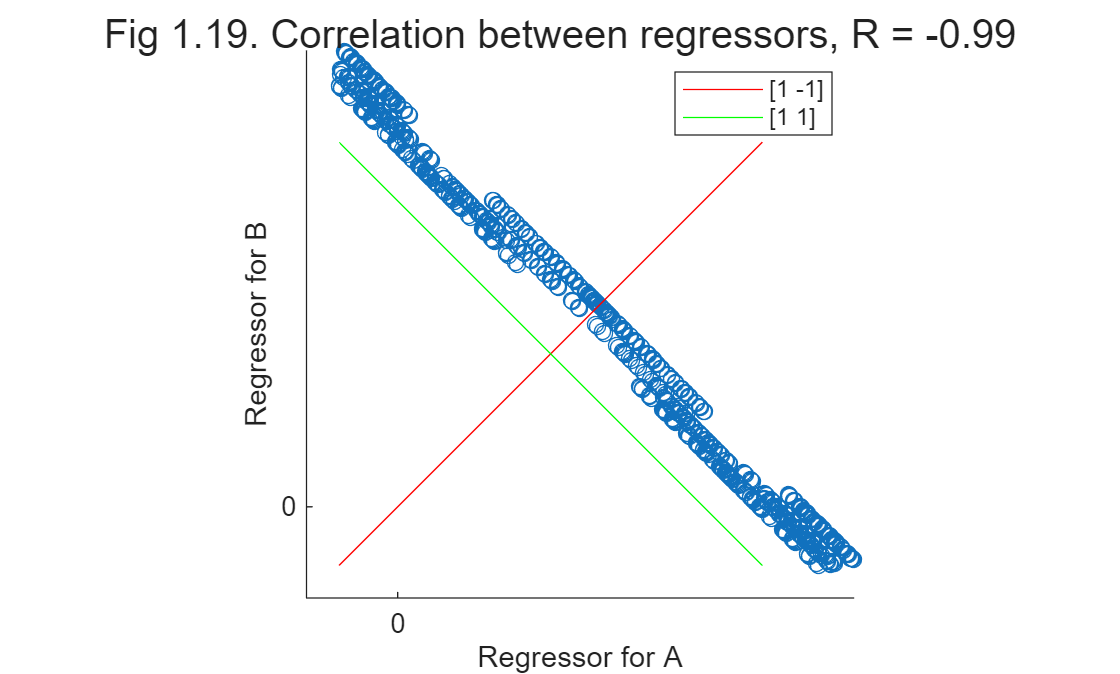

TM = [    0.5 0.5;      % Two event-types in randomised order
          0.5 0.5];     
v = genstim(TM, num_trl); 
X = gen_X(v, 4, HRF, 0.8); % Just ensuring TR is not a factor of SOA to get more variation in sampling
X = X/max(X(:));
figure, sgtitle(sprintf('Fig 1.19. Correlation between regressors, R = %3.2f', corr(X(:,1),X(:,2))))
hold on
plot(X(33:end,1),X(33:end,2),'o') % Ignore transient at start
axis square
set(gca,'XTick',[0],'YTick',[0]); xlabel('Regressor for A'); ylabel('Regressor for B')
l=line([min(X) max(X)-0.2]',[min(X) max(X)-0.2]'); set(l,'Color','r')
l=line([max(X)-0.2 min(X)]',[min(X) max(X)-0.2]'); set(l,'Color','g')
legend({'','[1 -1]','[1 1]'})

The two regressors are highly negatively correlated, because whenever there is high signal for A, there is low signal for B, and vice versa. If we then consider projecting this 2D distribution onto the ''x=-y'' direction shown in green, corresponding to a [1 -1] contrast, it will have a large spread, i.e, high variance, i.e., high efficiency for detecting the difference between A and B. However, if we project the distribution onto the ''x=y'' direction shown in red instead (corresponding to a [+1 +1] contrast), there will be little spread, i.e, low efficiency for detecting the common effect of A and B versus baseline. This reflects the markedly different efficiency for these two contrasts at short SOAs that was shown in Fig 1.15. Likewise, projection onto the ''x'' or ''y'' axes, corresponding to [1 0] or [0 1] contrasts respectively, will have less spread than onto the ''x=-y'' direction, i.e. less efficiency. If we wanted equal efficiency for all such contrasts, then we would need the scatter plot to be a cloud of points with circular symmetry, which would correspond to the regressors for A and B being orthogonal (which is what happens when null events are added).

This example also makes an important general point about correlations between regressors in a GLM. High, absolute correlation between two regressors means that the parameter estimate for each one will be estimated inefficiently, i.e, the parameter estimate itself will have high variance. In other words, if we estimated the parameter many times (with different random noise), we would get wildly different results. This is related to the "variance inflation factor" (VIF) sometimes reported for a regressor in a GLM. However, a high VIF only matters if you want to estimate the parameter for that single regressor; it does NOT matter for certain other contrasts, such as the difference between two correlated regressors considered here.

Indeed, in the extreme case that the regressors were perfectly correlated (correlation of +/-1, ie, collinear), we could not estimate unique values for their parameters (ie, they would have infinite variance). Nonetheless, we could still estimate the difference between them. Thus in short-SOA, randomised designs with no null events, we might detect brain regions showing a reliable difference between event-types, yet when we plot the event-related response, we might find they are all "activations" vs. baseline, all "deactivations" vs. baseline or some activations and some deactivations. However, these impressions are more apparent than real (and should not really be shown): If we tested the reliability of these activations / deactivations, they are unlikely to be significant. This is again because there is high variability associated with each estimate on its own, even if there is low variability for the estimate of their difference. In other words, we cannot estimate baseline reliably in such designs. This is why, for differential contrasts, it does not make sense to plot error bars showing the variability of each condition alone: one should plot error bars pertaining to the variability '''of the difference'''.

#### 1.3.1. Orthogonalisation (digression)

A common misapprehension is that one can overcome the problem of correlated regressors by "orthogonalising" one regressor with respect to the other. This rarely solves the problem. The parameter estimates always pertain to the orthogonal part of each regressor; this is an automatic property of "Ordinary Least Squares" (OLS) estimates of a GLM. Thus the parameter estimate for an orthogonalised regressor will NOT change; rather it is the parameter estimate for the other regressor (that has been orthogonalised aganist) that will change. This is shown for a 2D case in Fig 1.20.

X = [1.00 0.25 ;  % x coords (x1=X(:,1), x2=X(:,2))
     0.25 1.00];  % y coords
B = [0.5 0.5]'

B =     0.5000
    0.5000


y = X*B;          % (y is now data, not dimension!)
Bhat = pinv(X)*y  % OLS estimates (perfect in absence of noise)

Bhat =     0.5000
    0.5000



figure,sgtitle('Fig 1.20. Geometric perspective on orthogonalisation')
subplot(1,2,1), axis([-0.25 1.2 -0.25 1.2]), axis square, set(gca,'XTick',[0:0.5:1],'YTick',[0:0.5:1]); hold on
title('Correlated x1 and x2')
l=line([0 X(1,1)]', [0 X(2,1)]'); set(l,'Color','r','LineStyle',':');
l=line([0 X(1,2)]', [0 X(2,2)]'); set(l,'Color','b','LineStyle',':');
text(X(1,1),X(2,1)+0.04,'x1','FontSize',10)
text(X(1,2)-0.02,X(2,2)+0.04,'x2','FontSize',10)
text(y(1)+0.04,y(2)+0.04,'y','FontSize',10)
l=line([0 Bhat(1)*X(1,1)]', [0 Bhat(1)*X(2,1)]'); set(l,'LineWidth',2); set(l,'Color','r');
l=line(Bhat(1)*X(1,1) + [0 Bhat(2)*X(1,2)]', Bhat(1)*X(2,1) + [0 Bhat(2)*X(2,2)]'); set(l,'LineWidth',2); set(l,'Color','b');
set(gca,'XAxisLocation','origin','YAxisLocation','origin');

X(:,2) = orthog(X(:,2),X(:,1)); % Orthogonalise x2 with respect to x1
Bhat = pinv(X)*y

Bhat =     0.7353
    0.5000


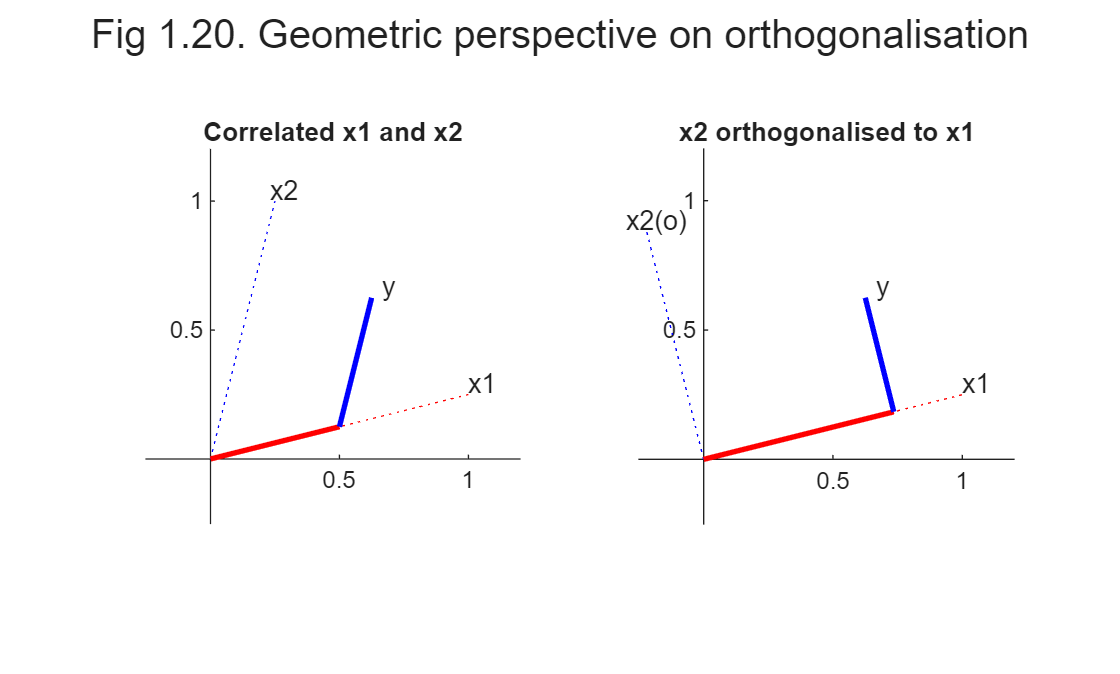

subplot(1,2,2), axis([-0.25 1.2 -0.25 1.2]), axis square, set(gca,'XTick',[0:0.5:1],'YTick',[0:0.5:1]); hold on
title('x2 orthogonalised to x1')
l=line([0 X(1,1)]', [0 X(2,1)]'); set(l,'Color','r','LineStyle',':');
l=line([0 X(1,2)]', [0 X(2,2)]'); set(l,'Color','b','LineStyle',':');
text(X(1,1),X(2,1)+0.04,'x1','FontSize',10)
text(X(1,2)-0.08,X(2,2)+0.04,'x2(o)','FontSize',10)
text(y(1)+0.04,y(2)+0.04,'y','FontSize',10)
l=line([0 Bhat(1)*X(1,1)]', [0 Bhat(1)*X(2,1)]'); set(l,'LineWidth',2); set(l,'Color','r');
l=line(Bhat(1)*X(1,1) + [0 Bhat(2)*X(1,2)]', Bhat(1)*X(2,1) + [0 Bhat(2)*X(2,2)]'); set(l,'LineWidth',2); set(l,'Color','b');
set(gca,'XAxisLocation','origin','YAxisLocation','origin');

The left panel of Fig 1.20 shows two positively correlated regressors x1 and x2 (the angle between them is <90 degrees). To get to the data (y), the most direct path (minimum squared length) is to travel 0.5 along x1 and 0.5 along x2 (ie B=[0.5 0.5]). The right panel shows what happens when x2 is orthogonalisd with respect to x1 (i.e., x2(o) is the orthogonalised version of x2, ie 90 degrees to x1). To get to the same data along these new directions (regressors), see how one still moves 0.5 along the new orthogonalised x2(o), but now has to move further (0.74 in fact) along the original x1.

The result of orthogonalisation is that the common variance will be assigned to the regressor relative to which the other regressor was orthogonalised. However, we must have an a priori reason for assuming this - otherwise we could just as well orthogonalise the other way round (ie, without such prior knowledge, there is no way to determine which of the two correlated regressors caused the common effect). In the absence of such knowledge, there is no need to orthogonalise, since the parameter estimates always reflect the unique variance explained by each regressor.

#### 1.3.2. More complex trials with more than one component

Anyway, returning to the effects of correlations on efficiency, this conception can help with the design of experiments where there is necessarily some degree of correlation between regressors. Two common experimental situations where this arises are: 1) when trials consist of two events, one of which must follow the other (such as a stimulus and then a response to that stimulus), and 2) blocks of events in which one wishes to distinguish transient (event-related) from sustained (epoch-related) effects. In both cases, one wants to estimate each effect separately (ie, [1 0] and [0 1] contrasts).

A common example of the first type of experiment are "working memory" designs, in which a trial consists of a stimulus, a short retention interval, and then a response. We shall ignore the retention interval, and concentrate on how one can separate the effect of the stimulus from that of the response. With short SOAs between each event-type (eg, 4s), the regressors for the stimulus and response will be highly negatively correlated, as shown in the left panel of Fig 1.21.

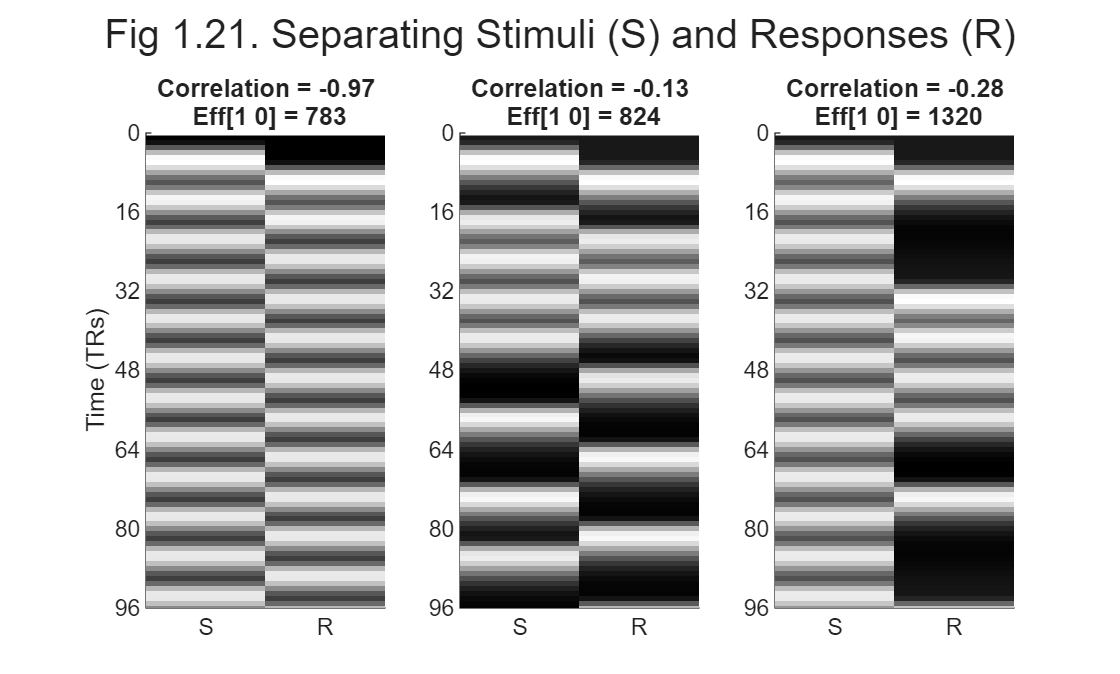

TM = [0 1; 1 0]; % Alternating conditions
stim = genstim(TM, num_trl); 
if stim(1)==2; stim = [1 stim]; end % (just to ensure first event always stimulus!)
X = gen_X(stim, 4);
eff = nan(2,3);
eff(1,1) = efficiency([1 0]', X); % Ignoring highpass
eff(2,1) = efficiency([0 1]', X); % Ignoring highpass

figure, sgtitle('Fig 1.21. Separating Stimuli (S) and Responses (R)')
subplot(1,3,1), hold on
title(sprintf('Correlation = %3.2f\n Eff[1 0] = %d',corr(X(:,1),X(:,2)),round(eff(1,1))))
imagesc(X), colormap('gray'); ylim([0 96]);
set(gca,'Ydir','reverse')
set(gca,'XTick',[1 2],'XTickLabel',{'S','R'}); xlim([0.5 size(X,2)+0.5])
set(gca,'YTick',[0:16:96]), ylabel('Time (TRs)')

rng(1) % Just to get nice example (and case where first event is stimulus for middle plot!)
TM = [0 0.5; 0.5 0]; % Alternating with jittered SOA (through null events)
v = genstim(TM, num_trl); 
if v(1)==2; v = [1 v]; end % (just to ensure first event always stimulus!)
X = gen_X(v, 4);  % Note also half expected number of stimuli
eff(1,2) = efficiency([1 0]', X); % Ignoring highpass
eff(2,2) = efficiency([0 1]', X); % Ignoring highpass

subplot(1,3,2), hold on
title(sprintf('Correlation = %3.2f\n Eff[1 0] = %d',corr(X(:,1),X(:,2)),round(eff(1,2))))
imagesc(X), colormap('gray'); ylim([0 96]);
set(gca,'Ydir','reverse')
set(gca,'XTick',[1 2],'XTickLabel',{'S','R'}); xlim([0.5 size(X,2)+0.5])
set(gca,'YTick',[0:16:96])

TM = [0 0.5 0.5; 1 0 0; 1 0 0]; % Third condition are catch trials (with no response)
v = genstim(TM, num_trl); 
if v(1)==2; v = [1 v]; end % (just to ensure first event always stimulus!)
v(find(v==3)) = NaN; 
X = gen_X(v, 4);
eff(1,3) = efficiency([1 0]', X); % Ignoring highpass
eff(2,3) = efficiency([0 1]', X); % Ignoring highpass

subplot(1,3,3), hold on
title(sprintf('Correlation = %3.2f\n Eff[1 0] = %d',corr(X(:,1),X(:,2)),round(eff(1,3))))
imagesc(X), colormap('gray'); ylim([0 96]);
set(gca,'Ydir','reverse')
set(gca,'XTick',[1 2],'XTickLabel',{'S','R'}); xlim([0.5 size(X,2)+0.5])
set(gca,'YTick',[0:16:96])


round(eff)

ans =          783         824        1320
         782         828         662


One way to improve efficiency is shown in the middle panel of Fig 1.21, which is to randomly vary (jitter) the time between successive stimuli and responses (assuming this is possible). This reduces the correlation between regressors, and therefore the efficiency for estimating (separating) the BOLD response to the stimuli and responses is increased (even though fewer stimuli presented in total). Note this does require jittering over quite a large range, in order to reduce the correlation appreciably.

A second way is to keep the stimulus-response interval fixed at 4s, but only require a response on a random half of trials ("catch trials"), as shown in the right panel of Fig 1.21. This does not reduce the correlation as much as jittering the timings (in this example), but has even higher efficiency by virtue of maintaining the total number of stimuli. It does however reduce the efficiency of estimating the response component, if that is also of interest (the second row of "eff" variable displayed above).

#### 1.3.3. Transient and sustained effects 

The second type of design tries to distinguish transient responses (or so-called "item" effects) from sustained responses (or so-called "state" effects). A lovely example of this is the experiment on visual attention by [[Chawla et al, 1999]](https://doi.org/10.1038/10230), in which the authors showed that attention to motion or colour of moving dots had two effects: it increased both the baseline activity (a "state" effect) and the gain of responses to a change in the attended attribute (an "item" effect). This was true for colour in V4, and for motion in V5. Such separation of transient and sustained effects requires modelling blocks of trials in terms of both individual events within blocks and sustained epochs throughout the blocks (sometimes called a "mixed design"). An example with a fixed SOA=6s between events is shown in Fig 1.22:

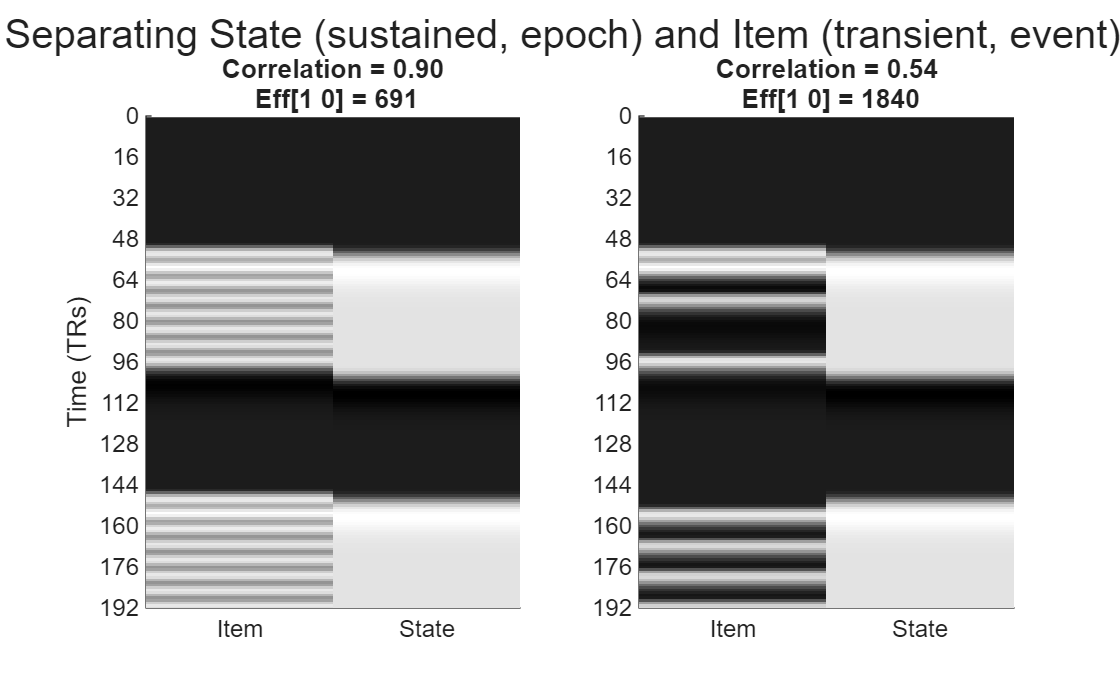

SOAmin = 6; stim_per_block = 8; TR = 1; dt = 0.1; total_time = SOAmin*2^12; 
X = nan(total_time/TR,2);

% Can generate blocked designs with a TM, but TM becomes very high dimensional, so stick with explicit method!
r = kron([NaN 1], ones(1,stim_per_block));
r = repmat(r, 1, ceil(total_time/(length(r)*SOAmin)));
X(:,1) = gen_X(r, SOAmin, HRF, TR);
X(:,1) = X(:,1)/max(X(:,1));

% Epochs equivalent to blocks of events every dt
samp_per_block = stim_per_block*SOAmin/dt;
r = kron([NaN 1], ones(1,samp_per_block));
r = repmat(r, 1, ceil(total_time/(length(r)*dt)));
X(:,2) = gen_X(r, dt, HRF, TR);
X(:,2) = X(:,2)/max(X(:,2)); % to match scaling

eff = nan(2,2);
eff(1,1) = efficiency([1 0]', X); % Ignoring highpass
eff(2,1) = efficiency([0 1]', X); % Ignoring highpass

figure, sgtitle('Fig 22. Separating State (sustained, epoch) and Item (transient, event) effects')
subplot(1,2,1), hold on
title(sprintf('Correlation = %3.2f\n Eff[1 0] = %d',corr(X(:,1),X(:,2)),round(eff(1,1))))
imagesc(X), colormap('gray'); ylim([0 192]);
set(gca,'Ydir','reverse')
set(gca,'XTick',[1 2],'XTickLabel',{'Item','State'}); xlim([0.5 size(X,2)+0.5])
set(gca,'YTick',[0:16:192]), ylabel('Time (TRs)')

% Now jitter fewer events per block
rng(1) % Just to get nice example 
v = []; o  = ones(1,stim_per_block);
for b = 1:ceil(total_time/(2*stim_per_block*SOAmin))
    u = o; 
    r = randperm(stim_per_block);
    u(r(1:(length(r)/2))) = NaN;  % equivalent to 50% nulls within block (note assumes stim_per_block multiple of 2)
    v = [v kron(NaN,o) u];
end

X(:,1) = gen_X(v, SOAmin, HRF, TR);
X(:,1) = X(:,1)/max(X(:,1));
eff(1,2) = efficiency([1 0]', X); % Ignoring highpass
eff(2,2) = efficiency([0 1]', X); % Ignoring highpass

subplot(1,2,2), hold on
title(sprintf('Correlation = %3.2f\n Eff[1 0] = %d',corr(X(:,1),X(:,2)),round(eff(1,2))))
imagesc(X), colormap('gray'); ylim([0 192]);
set(gca,'Ydir','reverse')
set(gca,'XTick',[1 2],'XTickLabel',{'Item','State'}); xlim([0.5 size(X,2)+0.5])
set(gca,'YTick',[0:16:192])


round(eff)

ans =          691        1840
         956        5181


In the left panel of Fig 1.22, with a fixed SOA between events within a block, the correlation between the event and epoch regressors is naturally very high, and the efficiency for detecting either effect alone is low. Once the SOA is jittered however (using 50% probability of null events within a block), the correlation is reduced and efficiency increased, as in right panel (in this case, efficiency for both [1 0] and [0 1] contrasts is increased, as can be seen in the second row of "eff"). (Note however that one perverse psychological side-effect of introducing some long SOAs between events within blocks is that participants may be less able to maintain a specific cognitive "state"...)

This concludes the three attempts to explain the basic ideas behind efficiency in fMRI designs for the mean univariate effect across trials. I hope at least one perspective helped. We now move on to the case where one wants to estimate the response to each individual trial.

## 2. Univariate analysis with trial-to-trial variability (e.g., Beta-series regression)

So far we have assumed that every trial (of the same type) produces the same amount of neural activity, and hence same BIR. It is possible that the neural activity varies from trial-to-trial, e.g., owing to different stimuli (which is particularly relevant to MVPA that we will consider later) and/or variations in attention, etc. Some analyses leverage on this trial-level variability to measure functional connectivity, e.g. "Beta Series Regression" (BSR), which measures to correlation of single-trial estimates between two brain regions [[Rissman et al., 2004]](https://doi.org/10.1016/j.neuroimage.2004.06.035). 

### 2.1. Least-Squares All (LSA)

The obvious way to estimate a separate Beta for each trial is to treat each trial as a separate regressor in the GLM. This approach has been called "Least Squares All" [[Mumford et al., 2012]](http://dx.doi.org/10.1016/j.neuroimage.2011.08.076), and is illustrated in Fig 2.1:

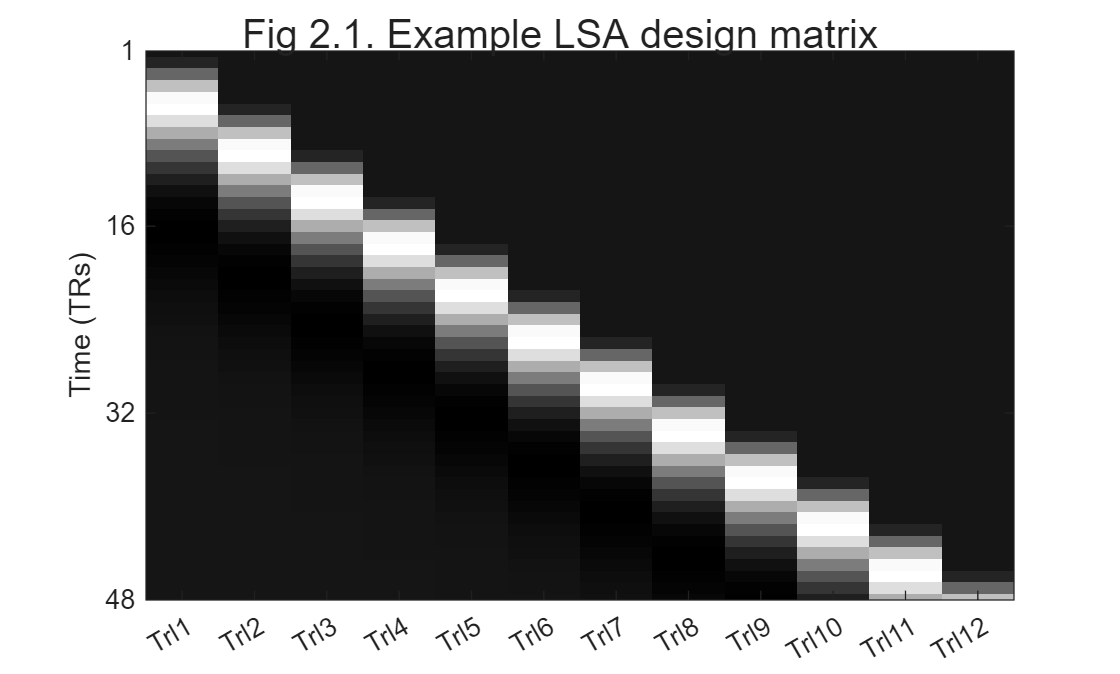

SOAmin = 4; num_trl = 12; total_time = SOAmin*num_trl; 
v = [1:num_trl];
X_LSA = gen_X(v, SOAmin, HRF, TR);

figure, sgtitle('Fig 2.1. Example LSA design matrix')
imagesc(X_LSA), colormap('gray'); ylim([0 total_time]);
trl_lab={}; for n=1:num_trl; trl_lab{end+1} = sprintf('Trl%d',n); end
set(gca,'Ydir','reverse')
set(gca,'XTick',v,'XTickLabel',trl_lab); xlim([0.5 size(X_LSA,2)+0.5]); ylim([1 total_time/TR])
set(gca,'YTick',[1 16:16:total_time]/TR), ylabel('Time (TRs)')

(Note that OLS estimation of LSA models is only possible if the SOA>TR, so X is "taller" than it is "wide", i.e., more knowns than unknowns.) We can model random variance in activity across trials by drawing the true Beta (B) from a Gaussian distribution with a certain mean and standard deviation ("trl_std" below). After convolving with an HRF and downsampling every TR, we can then add random noise to each scan (TR) from another Gaussian with zero mean and a different standard deviation ("scn_std" below). As we will see, what turns out to be critical is the ratio of trial variability to scan variability (ie, trl_std : scn_std).

#### 2.2.1 Simulated Efficiency and Bias

Rather than use the above efficiency equation, we will now use the more general way to estimate efficiency by generating data many times, fitting a GLM to each such simulation, and then examining the variability (and bias) in the Beta estimates that result. For example, for basic efficiency, we can take the inverse of the standard deviation of those estimates across trials (what [[Abdulrahman & Henson, 2016]](https://doi.org/10.1016/j.neuroimage.2015.11.009) called "precision of the sample mean"). However, we can now also examine *bias*: the difference between the mean of those estimates and the mean of true Betas used to generate the data. The LSA approach illustrated above is an "unbiased estimate", so on average the bias will be zero. Other approaches below introduce diffrent types of bias.

Let's start with efficiency for estimating the mean response across trials presented every 2 seconds, and compare the LSA above with separate regressors per trial with the standard Least Squares Unitary (LSU) with one regressor for all trials that we have assumed up until now. In the code below, we prepare two designs matrices, one for each model, and also their pseudoinverses, which are used in OLS estimation. The true mean of the Betas is 2, and we use in the function "gen_y" to generate an fMRI timeseries given a certain standard deviation across trials (signal) and scans (noise).

SOA = 2; TR = 1;   
num_trl = 2^8;
v = [1:num_trl]; % Give each trial a unique type for LSA

% Generate design matrices for LSA and LSU
X_LSA = gen_X(v, SOA); 
X_LSU = gen_X(ones(1,num_trl), SOA);

% Add constant term to both
X_LSA = [X_LSA ones(size(X_LSA,1),1)]; 
X_LSU = [X_LSU ones(size(X_LSU,1),1)];

% Prepare their pseudoinverse for OLS estimation (to speed up loop below)
pX_LSA = pinv(X_LSA);
pX_LSU = pinv(X_LSU);

% Explore a range of ratios of trial variability to scan variability
mean_Beta = 2;
mB = mean_Beta*ones(num_trl,1);
scn_std = 1;
trl_std = [0 1/4 1 4]*scn_std;
num_std = length(trl_std);

% Simulate multiple experiments and store differences in estimated and sample means (may take some time!)
rng(1)
num_exp = 2^12;
est_diff = nan(num_exp, 2, num_std);
for s=1:num_std
    fprintf('Trial:Scan std ratio = %3.2f\n',trl_std(s)/scn_std);
    for e=1:num_exp
        [y,B] = gen_y(mB, SOA, trl_std(s), scn_std);
        B_hat = pX_LSU * y;
        est_diff(e,1,s) = B_hat(1) - mean(B);
        B_hat = pX_LSA * y;
        B_hat = B_hat(1:num_trl); % ignore constant term
        est_diff(e,2,s) = mean(B_hat) - mean(B);
    end
end

Trial:Scan std ratio = 0.00
Trial:Scan std ratio = 0.25
Trial:Scan std ratio = 1.00
Trial:Scan std ratio = 4.00


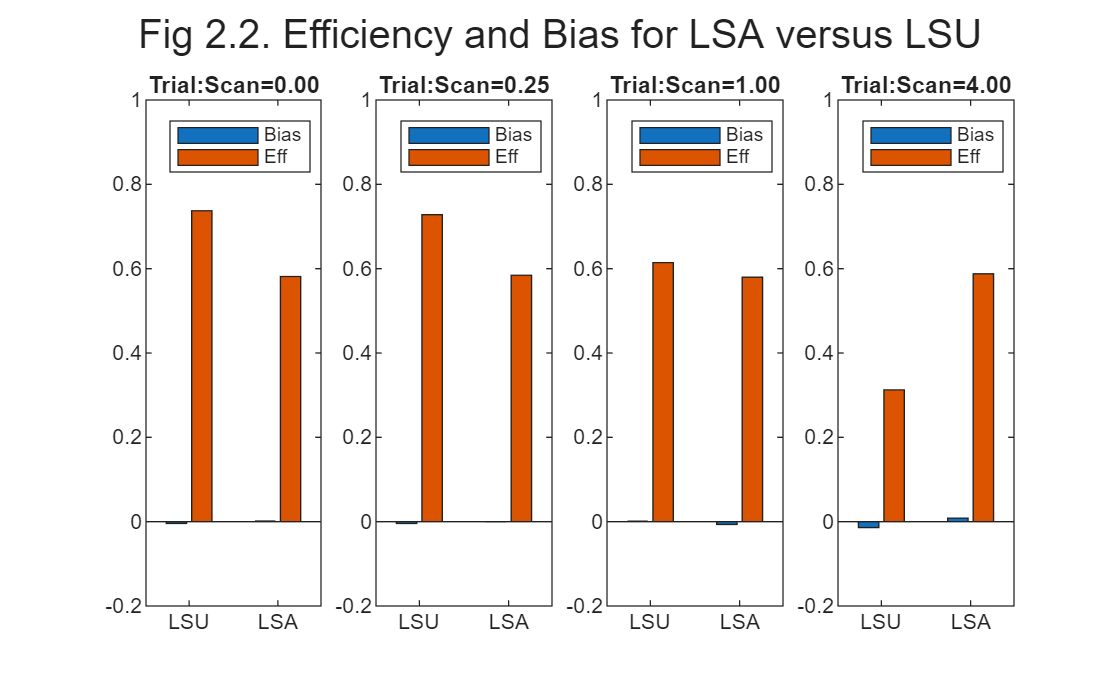

Trial:Scan std ratio = 0.00


	 LSU:     Bias=-0.00 (Z=-0.02), Efficiency=4.46


	 LSA:     Bias=0.00 (Z=0.00), Efficiency=2.81


Trial:Scan std ratio = 0.25


	 LSU:     Bias=-0.00 (Z=-0.02), Efficiency=4.35


	 LSA:     Bias=-0.00 (Z=-0.00), Efficiency=2.84


Trial:Scan std ratio = 1.00


	 LSU:     Bias=0.00 (Z=0.00), Efficiency=3.11


	 LSA:     Bias=-0.01 (Z=-0.02), Efficiency=2.80


Trial:Scan std ratio = 4.00


	 LSU:     Bias=-0.01 (Z=-0.01), Efficiency=1.05


	 LSA:     Bias=0.01 (Z=0.02), Efficiency=2.87



figure, sgtitle('Fig 2.2. Efficiency and Bias for LSA versus LSU')
for s=1:num_std
    fprintf('Trial:Scan std ratio = %3.2f\n',trl_std(s)/scn_std);
    m = mean(squeeze(est_diff(:,1,s)));
    d =  std(squeeze(est_diff(:,1,s)));
    fprintf('\t LSU:     Bias=%3.2f (Z=%3.2f), Efficiency=%3.2f\n', m, m/d, 1/d);
    p = [m log10(1+1/d)]; % Efficiency is inversely related to d (and log is just to put on same scale as bias)

    m = mean(squeeze(est_diff(:,2,s)));
    d =  std(squeeze(est_diff(:,2,s)));
    fprintf('\t LSA:     Bias=%3.2f (Z=%3.2f), Efficiency=%3.2f\n', m, m/d, 1/d);
    p = [p; m log10(1+1/d)];
    subplot(1,num_std,s)
    bar(p); legend({'Bias', 'Eff'},'Location','NorthEast'); 
    set(gca,'XTickLabel',{'LSU','LSA'}); ylim([-0.2 1]);
    title(sprintf('Trial:Scan=%3.2f',trl_std(s)/scn_std))
end

Fig 2.2 shows that, as the ratio of trial variability to scan variability increases, the relative efficiency changes from LSU being best (eg when no trial variability in left panel) to LSA being best (right panel). Both methods are unbiased, in that the blue bars are close to zero in all cases (the Z-score in text output is the ratio of bias to standard deviation, ie a statistic that would not be significantly different from zero in these cases). Note that we are estimating the efficiency of the sample mean, which can differ from the true (population) mean when generating a finite number of trials of randomly varying amplitude.

### 2.2 Regularised Estimation (minimising variance of Betas)

While Fig 2.2 shows that LSA works fine if the trial variability is higher than the scan variability, what if the scan variability (noise) is much higher instead, which may often be the case, and yet we still want to estimate a Beta for each individual trial (so LSU is inappropriate)? One solution is to *regularise* the estimation of the Betas from an LSA model. Regularisation is a departure from OLS, in which we minimise not only the sum of squares of the difference between the data and fitted response, but also some property of the Betas themselves, such as their sum-of-squares. The latter is called the L2-norm and this type of regularisation is often called "ridge regression". As shown below, the benefit of regularisation is that the efficiency is increased even with high levels of noise; the downside is that we pay the price of bias, specifically a negative bias such that the estimates are "shrunk" towards zero, as shown with the code below.

num_TRs = size(X_LSA,1);
R = [[eye(num_trl) zeros(num_trl,1)]; [zeros(1,num_trl) 0]];    % regularise all Betas but not grand mean
lambda = 1; % The regularisation "hyper-parameter" (which can be optimised, but not here)
pX_LSA     = inv(X_LSA'*X_LSA)*X_LSA';              % Normal LSA, equivalent to pinv, but to match below
pX_LSA_reg = inv(X_LSA'*X_LSA + lambda*R)*X_LSA';   % Ridge regression or L2-norm regularisation

est_diff = nan(num_exp, 2, num_std);
est_corr = nan(num_exp, 2, num_std);
rng(1)
for s=1:num_std
    fprintf('Trial:Scan std ratio = %3.2f\n',trl_std(s)/scn_std);
    for e=1:num_exp
        [y,B] = gen_y(mB, SOA, trl_std(s), scn_std);
        B_hat = pX_LSA * y;
        B_hat = B_hat(1:num_trl);
        est_diff(e,1,s) = mean(B_hat) - mean(B);
        est_corr(e,1,s) = corr(B_hat, B);

        B_hat = pX_LSA_reg * y;
        B_hat = B_hat(1:num_trl);
        est_diff(e,2,s) = mean(B_hat) - mean(B);
        est_corr(e,2,s) = corr(B_hat, B);
    end
end

Trial:Scan std ratio = 0.00
Trial:Scan std ratio = 0.25
Trial:Scan std ratio = 1.00
Trial:Scan std ratio = 4.00


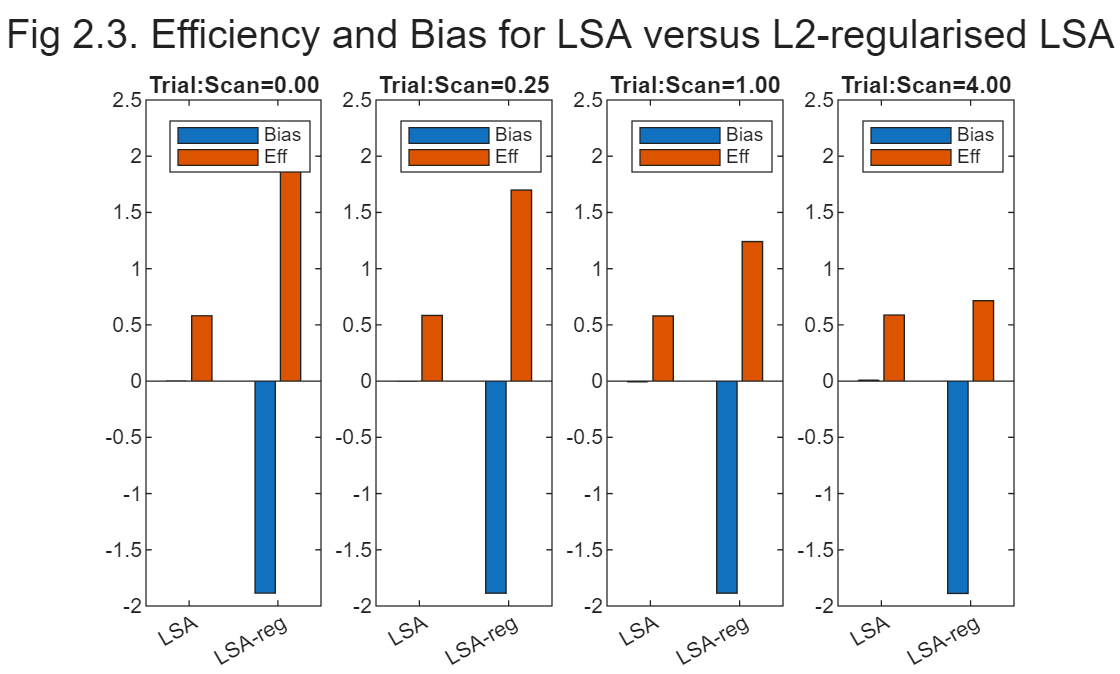

Trial:Scan std ratio = 0.00


	 LSA:     Bias=0.00 (Z=0.00), Efficiency=2.81


	 LSA-reg: Bias=-1.89 (Z=-135.26), Efficiency=71.73


Trial:Scan std ratio = 0.25


	 LSA:     Bias=-0.00 (Z=-0.00), Efficiency=2.84


	 LSA-reg: Bias=-1.89 (Z=-92.36), Efficiency=48.98


Trial:Scan std ratio = 1.00


	 LSA:     Bias=-0.01 (Z=-0.02), Efficiency=2.80


	 LSA-reg: Bias=-1.89 (Z=-30.94), Efficiency=16.41


Trial:Scan std ratio = 4.00


	 LSA:     Bias=0.01 (Z=0.02), Efficiency=2.87


	 LSA-reg: Bias=-1.89 (Z=-7.91), Efficiency=4.19



figure, sgtitle('Fig 2.3. Efficiency and Bias for LSA versus L2-regularised LSA')
for s=1:num_std
    fprintf('Trial:Scan std ratio = %3.2f\n',trl_std(s)/scn_std);
    m = mean(squeeze(est_diff(:,1,s)));
    d =  std(squeeze(est_diff(:,1,s)));
    fprintf('\t LSA:     Bias=%3.2f (Z=%3.2f), Efficiency=%3.2f\n', m, m/d, 1/d);
    p = [m log10(1+1/d)]; 

    m = mean(squeeze(est_diff(:,2,s)));
    d =  std(squeeze(est_diff(:,2,s)));
    fprintf('\t LSA-reg: Bias=%3.2f (Z=%3.2f), Efficiency=%3.2f\n', m, m/d, 1/d);
    p = [p; m log10(1+1/d)]; % Efficiency is inversely related to d (and log is just to put on same scale as bias)
    subplot(1,num_std,s)
    bar(p); legend({'Bias', 'Eff'},'Location','NorthEast'); 
    set(gca,'XTickLabel',{'LSA','LSA-reg'}); ylim([-2 2.5]);
    title(sprintf('Trial:Scan=%3.2f',trl_std(s)/scn_std))
end

As shown by the orange bars in Fig 2.3, efficiency is higher for the regularised estimator, but the downside is now a negative bias (blue bars), with Z-scores indicating significantly smaller estimates of the mean relative to the true mean.

Note that now that both methods LSA (OLS) and LSA-Reg estimate a Beta for every trial, we can introduce a third measure of performance, which is the correlation between those estimates and the true Betas (except for case when ratio is 0, i.e., when there is no trial variability to correlate). The results are shown in Fig 2.4:

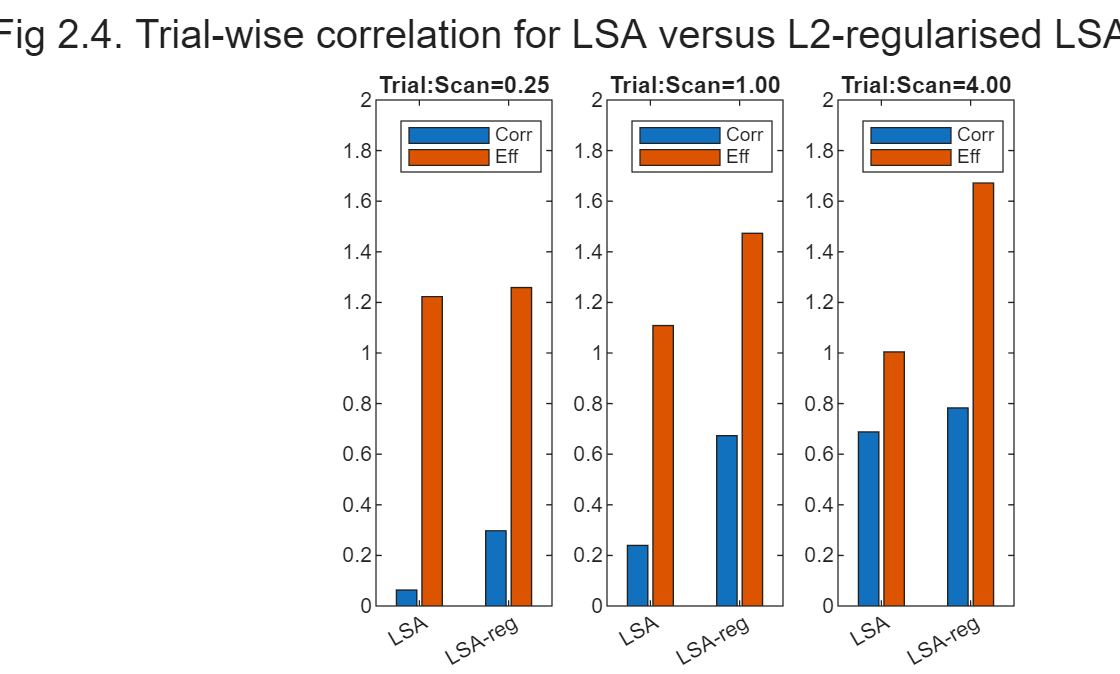

Trial:Scan std ratio = 0.25


	 LSA:     Correlation, M(SD)=0.06(0.06)


	 LSA-reg: Correlation, M(SD)=0.30(0.06)


Trial:Scan std ratio = 1.00


	 LSA:     Correlation, M(SD)=0.24(0.08)


	 LSA-reg: Correlation, M(SD)=0.67(0.03)


Trial:Scan std ratio = 4.00


	 LSA:     Correlation, M(SD)=0.69(0.11)


	 LSA-reg: Correlation, M(SD)=0.78(0.02)


figure, sgtitle('Fig 2.4. Trial-wise correlation for LSA versus L2-regularised LSA')
for s=1:num_std
    if trl_std(s) > 0
        fprintf('Trial:Scan std ratio = %3.2f\n',trl_std(s)/scn_std);
        m = mean(squeeze(est_corr(:,1,s)));
        d =  std(squeeze(est_corr(:,1,s)));
        fprintf('\t LSA:     Correlation, M(SD)=%3.2f(%3.2f)\n', m, d);
        p = [m log10(1+1/d)]; 
    
        m = mean(squeeze(est_corr(:,2,s)));
        d =  std(squeeze(est_corr(:,2,s)));
        fprintf('\t LSA-reg: Correlation, M(SD)=%3.2f(%3.2f)\n', m, d);
        p = [p; m log10(1+1/d)];
        subplot(1,num_std,s)
        bar(p); legend({'Corr', 'Eff'},'Location','NorthEast')
        set(gca,'XTickLabel',{'LSA','LSA-reg'}); ylim([0 2])
        title(sprintf('Trial:Scan=%3.2f',trl_std(s)/scn_std))
    end
end

Note that the regularised estimator produces higher correlations (blue bars) particularly when noise variability is higher than trial variability (estimates that also vary less across simulations, as in orange "efficiency" bars). This is relevant to techniques like BSR that measure the correlation between Beta "series" across two or more brain regions: regularised estimators are likely to produce higher such trial-based "connectivity", in that they are more robust to fMRI scan-level noise.

### 2.3. Least-Squares Separate (LSS) (temporal smoothness regularisation)

Another approach to regularisation is to maximise the smoothness of the parameter estimates across successive trials. This is achieved by another popular technique called "Least Squares Separate" (LSS). In this approach, a different design matrix is fit for each trial, which contains one regressor for that trial, and a second regressor in which all other trials (of the same type) are modelled together. Some examples are shown below:

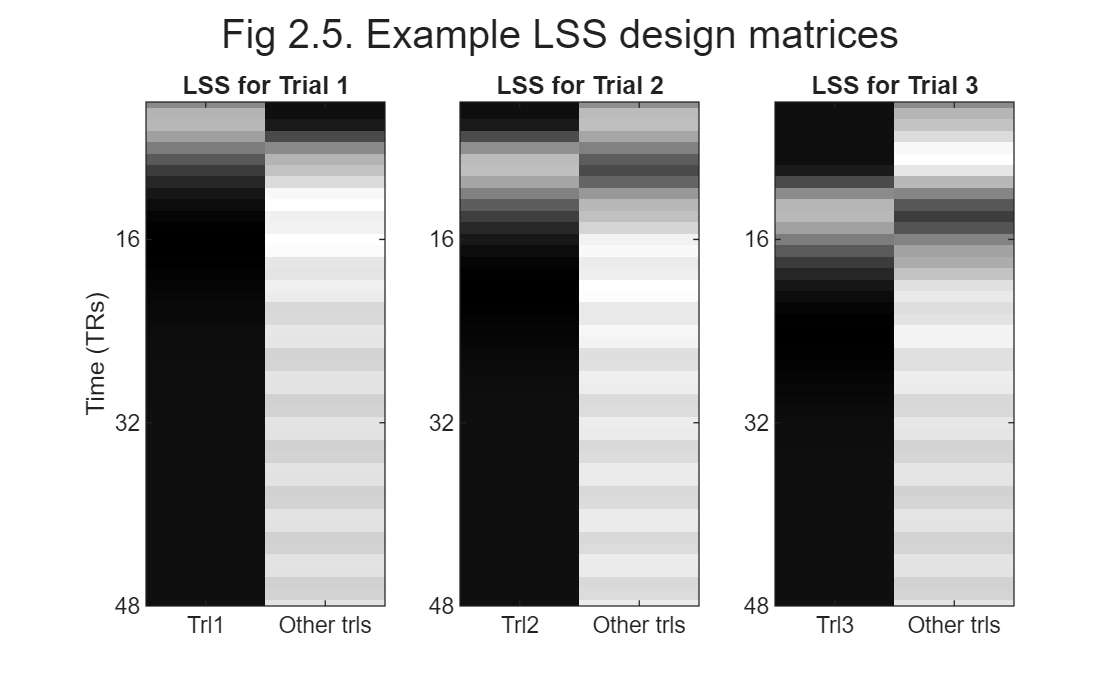

figure, sgtitle('Fig 2.5. Example LSS design matrices')
trl_lab = {};
for t = 1:3 % would normally run to num_trl
    v = 2*ones(1,num_trl);
    v(t) = 1;
    X_LSS = gen_X(v, SOAmin, HRF, TR);
    subplot(1,3,t)
    imagesc(X_LSS), colormap('gray'); ylim([0 total_time]);
    set(gca,'Ydir','reverse')
    trl_lab{1} = sprintf('Trl%d',t); trl_lab{2} = sprintf('Other trls');
    set(gca,'XTick',[1 2],'XTickLabel',trl_lab); xlim([0.5 size(X_LSS,2)+0.5]); ylim([4 total_time/TR])
    set(gca,'YTick',[1 16:16:total_time]/TR)
    if t==1, ylabel('Time (TRs)'); end
    title(sprintf('LSS for Trial %d',t));
end

The function "fit_lss" fits an LSS model to data (starting with an LSA model). Note that because this involves fitting the GLM as many times as there are trials of interest, LSS can take a while to fit (and is often performed on a handful of ROIs rather than every voxel). We can now compare LSS to LSA in terms of both efficiency for estimating the mean, and also the correlation between the true and estimated Betas:

% Because it takes a while to run, just compare two cases...
scn_std = [0.2 0.1]; % ... one where trial variability > scan variability
trl_std = [0.1 0.4]; % ... and one where scan variabilty > trial variability

num_std = length(trl_std);

% Need to reduce for speed purposes
num_trl = 2^7; 
mB = mean_Beta*ones(num_trl,1);
v = ones(num_trl,1);
SOA = 2;

X_LSA = gen_X(1:num_trl, SOA); 
X_LSA = [X_LSA ones(size(X_LSA,1),1)];
pX_LSA = pinv(X_LSA);

% Note that, because we are now simulating shorter sequences of trials (to
% save time), we need to remove transients at start and end of each sequence
% that would only reduce differences between LSA and LSS
transient = ceil(32/SOA); % Must be less than half num_trl!
num_exp = 2^8;
est_diff = nan(num_exp, 2, num_std);
est_corr = nan(num_exp, 2, num_std);
rng(1)
for s=1:num_std
    fprintf('Computing with Trial:Scan std ratio = %3.2f...\n',trl_std(s)/scn_std(s));
    for e=1:num_exp
        [y,B] = gen_y(mB, SOA, trl_std(s), scn_std(s));
        B = B((transient+1):(end-transient));

        B_hat_LSA = pX_LSA * y;
        B_hat_LSA = B_hat_LSA((transient+1):(end-transient-1));        
        est_diff(e,1,s) = mean(B_hat_LSA) - mean(B);
        est_corr(e,1,s) = corr(B_hat_LSA, B);

        B_hat_LSS = fit_lss(X_LSA, v, y, transient);
        est_diff(e,2,s) = mean(B_hat_LSS) - mean(B);
        est_corr(e,2,s) = corr(B_hat_LSS, B);
    end
end

Computing with Trial:Scan std ratio = 0.50...
Computing with Trial:Scan std ratio = 4.00...


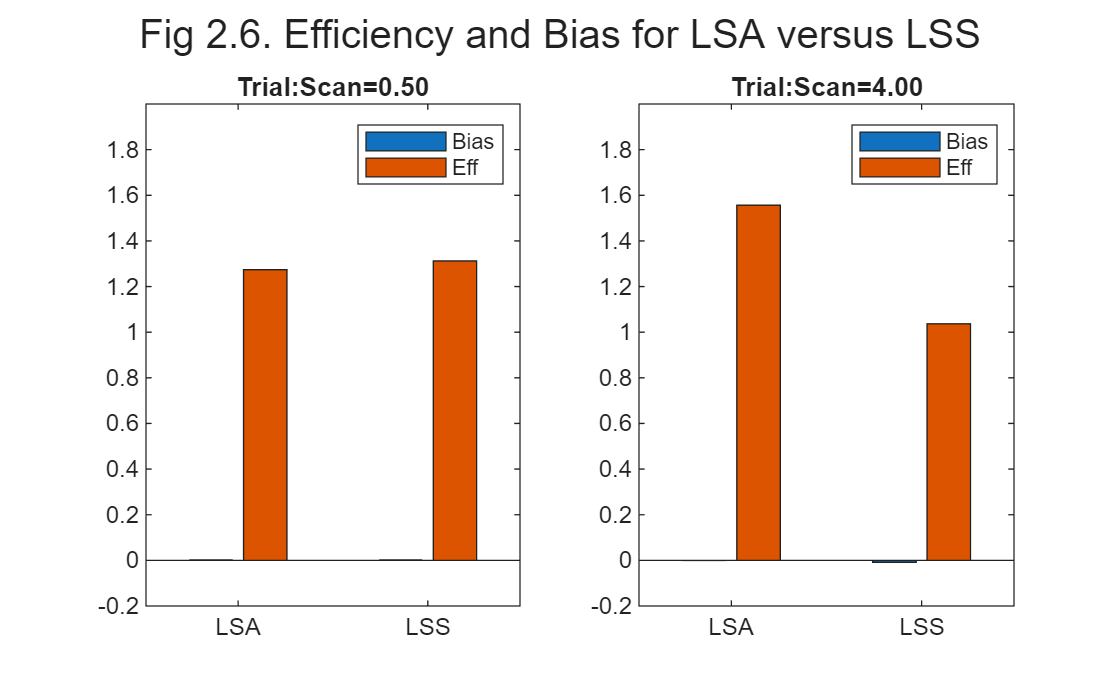

Trial:Scan std ratio = 0.50


	 LSA:     Bias=0.00 (Z=0.04), Efficiency=17.79


	 LSS:     Bias=0.00 (Z=0.03), Efficiency=19.53


Trial:Scan std ratio = 4.00


	 LSA:     Bias=-0.00 (Z=-0.01), Efficiency=35.02


	 LSS:     Bias=-0.01 (Z=-0.09), Efficiency=9.88



figure, sgtitle('Fig 2.6. Efficiency and Bias for LSA versus LSS')
for s=1:num_std
    fprintf('Trial:Scan std ratio = %3.2f\n',trl_std(s)/scn_std(s));
    m = mean(squeeze(est_diff(:,1,s)));
    d =  std(squeeze(est_diff(:,1,s)));
    fprintf('\t LSA:     Bias=%3.2f (Z=%3.2f), Efficiency=%3.2f\n', m, m/d, 1/d);
    p = [m log10(1+1/d)]; 

    m = mean(squeeze(est_diff(:,2,s)));
    d =  std(squeeze(est_diff(:,2,s)));
    fprintf('\t LSS:     Bias=%3.2f (Z=%3.2f), Efficiency=%3.2f\n', m, m/d, 1/d);
    p = [p; m log10(1+1/d)];
    subplot(1,num_std,s), 
    bar(p); legend({'Bias', 'Eff'},'Location','NorthEast')
    set(gca,'XTickLabel',{'LSA','LSS'}); ylim([-0.2 2]);
    title(sprintf('Trial:Scan=%3.2f',trl_std(s)/scn_std(s)))
end

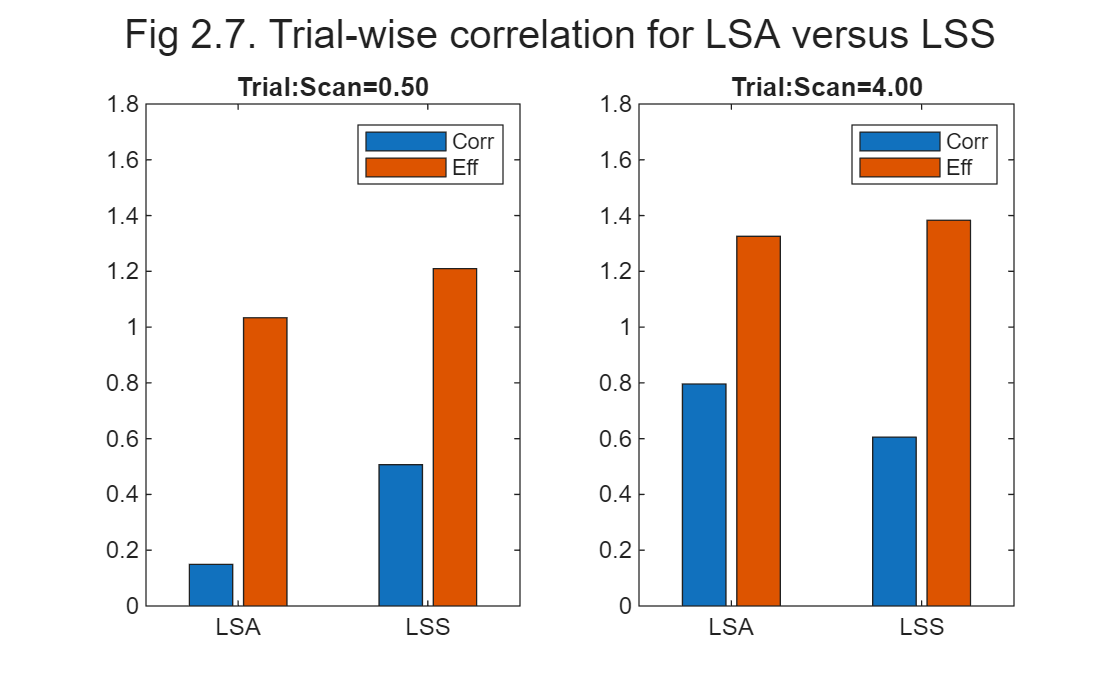

Trial:Scan std ratio = 0.50


	 LSA:     Correlation, M(SD)=0.15(0.10)


	 LSS:     Correlation, M(SD)=0.51(0.07)


Trial:Scan std ratio = 4.00


	 LSA:     Correlation, M(SD)=0.80(0.05)


	 LSS:     Correlation, M(SD)=0.61(0.04)



figure, sgtitle('Fig 2.7. Trial-wise correlation for LSA versus LSS')
for s=1:num_std
    fprintf('Trial:Scan std ratio = %3.2f\n',trl_std(s)/scn_std(s));
    m = mean(squeeze(est_corr(:,1,s)));
    d =  std(squeeze(est_corr(:,1,s)));
    fprintf('\t LSA:     Correlation, M(SD)=%3.2f(%3.2f)\n', m, d);    
    p = [m log10(1+1/d)]; 

    m = mean(squeeze(est_corr(:,2,s)));
    d =  std(squeeze(est_corr(:,2,s)));
    fprintf('\t LSS:     Correlation, M(SD)=%3.2f(%3.2f)\n', m, d);
    p = [p; m log10(1+1/d)];
    subplot(1,num_std,s), 
    bar(p); legend({'Corr', 'Eff'},'Location','NorthEast')
    set(gca,'XTickLabel',{'LSA','LSS'}); ylim([0 1.8])
    title(sprintf('Trial:Scan=%3.2f',trl_std(s)/scn_std(s)))
end

From Fig 2.6, we can see that LSS is more efficient than LSA at the low SNR (low trial:scan ratio) for estimating the mean, while LSA is more efficient at high SNR (and both methods are unbiased estimates of the mean). However, we rarely care about the mean across trials when we are estimating individual trials (e.g., for BSR), so more relevant are the results in Fig 2.7, which show that LSS produces higher correlations in low SNR (blue bars in left panel), while LSA performs better at higher SNR.

The reason why LSS is more robust to scan noise is that it results in smoother estimates across trials. This can be seen in Fig 2.8, which plots example Beta estimates (in dotted blue or red) for the first 32 trials (after transient) against the true Betas (in solid green):

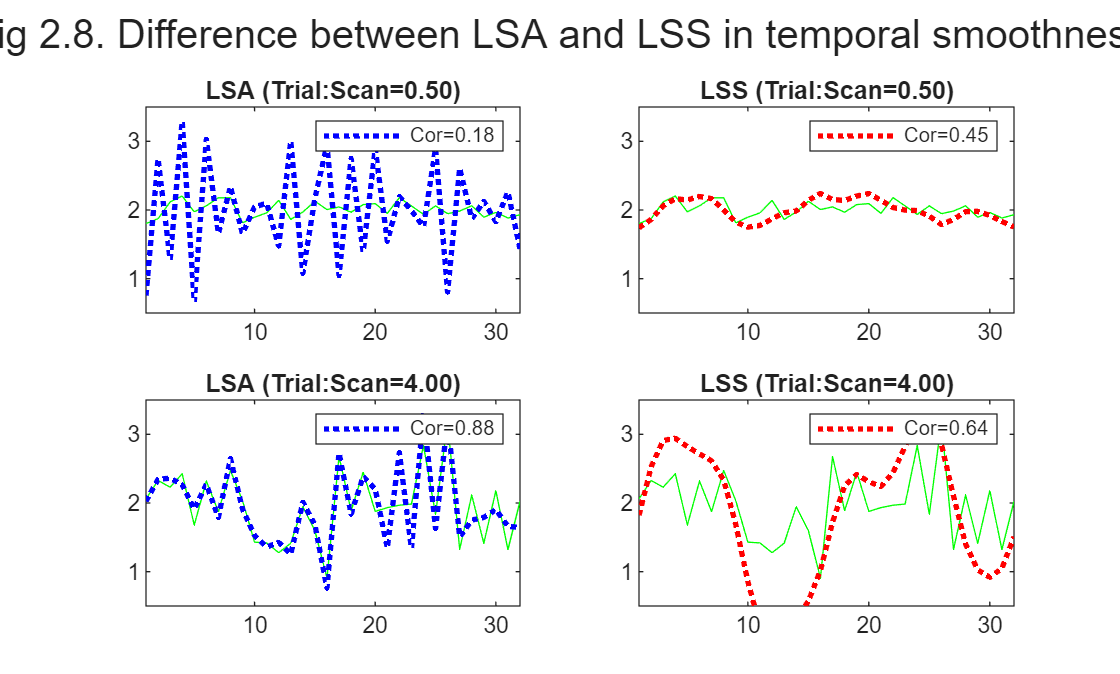

figure, sgtitle('Fig 2.8. Difference between LSA and LSS in temporal smoothness')
t = 1:32; % assumes num_trl>(48+2*transient)
rng(1)
for s=1:num_std
    [y,B] = gen_y(mB, SOA, trl_std(s), scn_std(s));
    B = B((transient+1):(end-transient));

    B_hat_LSA = pX_LSA * y;
    B_hat_LSA = B_hat_LSA((transient+1):(end-transient-1));

    B_hat_LSS = fit_lss(X_LSA, v, y, transient);

    subplot(2,2,1+(s-1)*2); plot(t,B(t),'g-'); hold on, plot(t,B_hat_LSA(t),'b:','LineWidth',2);
    title(sprintf('LSA (Trial:Scan=%3.2f)',trl_std(s)/scn_std(s))); axis([min(t) max(t) 0.5 3.5]); set(gca,'YTick',[1:3])
    legend({'', sprintf('Cor=%3.2f', corr(B_hat_LSA,B))})
    subplot(2,2,2+(s-1)*2); plot(t,B(t),'g-'); hold on, plot(t,B_hat_LSS(t),'r:','LineWidth',2);
    title(sprintf('LSS (Trial:Scan=%3.2f)',trl_std(s)/scn_std(s))); axis([min(t) max(t) 0.5 3.5]); set(gca,'YTick',[1:3])
    legend({'', sprintf('Cor=%3.2f', corr(B_hat_LSS,B))})
end

The top two panels of Fig 2.8 show the high-noise case (low trial:scan ratio). The top left panel shows the LSA estimates, which are highly variable (indeed, show a sawtooth pattern owing to the high positive correlation between regressors for adjacent trials). As a result, the correlation with the true Betas (shown in Legend) is low. The top right panel shows the LSS estimates for the same true Betas. You can see that the estimates vary less across trials (are smoother), and the correlation is higher as a consequence.

The bottom left and right panels of Fig 2.8 show the opposite low-noise case (high trial:scan ratio), where the LSA estimates track the true values very well, but the LSS estimates do not track them as well. Thus whether LSA or LSS models are better depends on the ratio of trial:scan variability. With real data, we do not know this ratio unfortunately (and do not know the true Betas), though my experience with real data is that LSS generally produces better results (suggesting that trial variance is normally lower than scan noise). 

Finally, note that we have not considered the temporal autocorrelation of the noise (scan-to-scan). This is normally estimated by an AR(p) model, which is then inverted in order to pre-whiten the data and model [[Corbin et al., 2018]](https://doi.org/10.1002/hbm.24218). The choice of model (e.g, LSA vs LSS) will affect this estimation, but is beyond the present scope (though I would suspect its influence to be small).

## 3. Multivariate analysis (MVPA/RSA)

So far we have focused on a single voxel. In multi-voxel pattern analysis (MVPA), or its special case of Representational Similarity Analysis (RSA), we care about how well we can estimate patterns across voxels. Indeed, we normally want to estimate one pattern per trial. As will be shown later, we do not care so much about the absolute Betas in each voxel, but rather about the relative Betas across voxels.

Let's assume we have 16 voxels, and two trial-types (A and B), which produce orthogonal patterns over those voxels (but which are randomly intermixed every 4s):

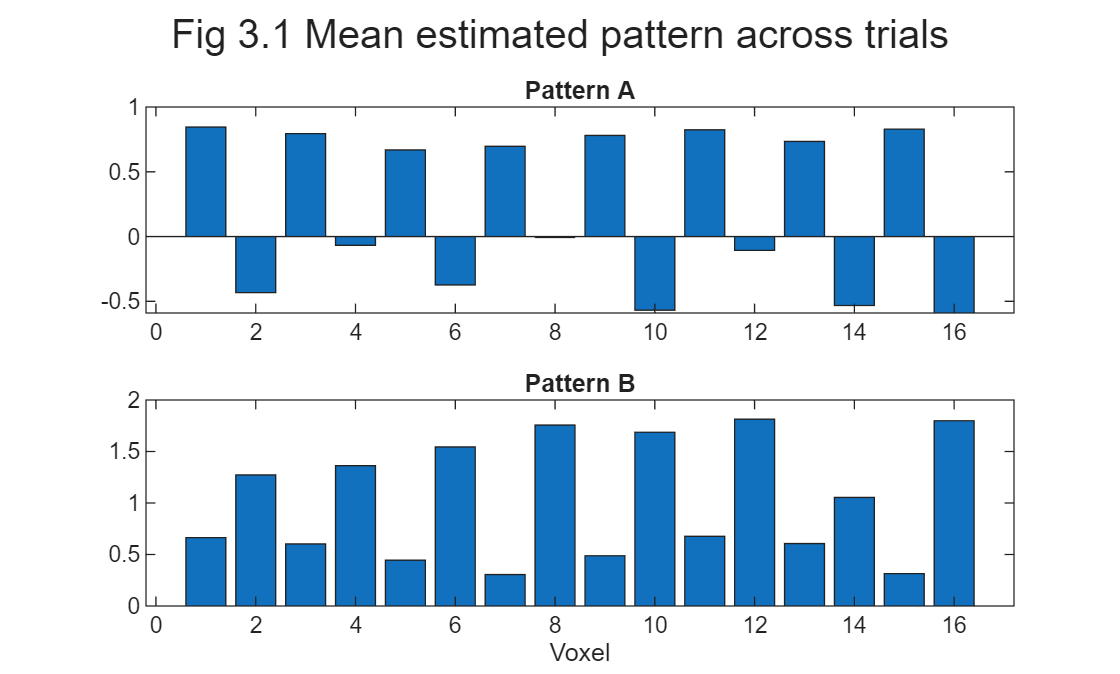

num_vox = 16;  % Assume multiple of 2
% Generate orthogonal base patterns:
pat_A = repmat([1 0], 1, round(num_vox/2)); 
pat_B = repmat([0 1], 1, round(num_vox/2));

num_trl = 160; % (per trial-type)
mB = [repmat(pat_A, num_trl, 1); repmat(pat_B, num_trl, 1)];

trl_std = 1; % Scaling (std) of trial (co)variability
c_trl   = 1; % Covariance across voxels of trial variability (1=all voxels vary same way)
S_trl   = c_trl * ones(num_vox) + (1-c_trl)*eye(num_vox); % Covariance matrix for mvnrnd

rng(1)
B = trl_std * mvnrnd(mB, S_trl); % Start by concatenating patterns...

r = randperm(2*num_trl); % ...then permute their order of randomly
%r = 1:(2*num_trl);
mB = mB(r,:);
B = B(r,:); 
v = floor((r-1)/num_trl)+1;  % (ordered labels for each stimulus-type)

% Generate LSA design matrix based on trial orders
TR = 1; SOA = 2;
X_LSA = gen_X(1:(2*num_trl), SOA, HRF, TR); 
X_LSA = [X_LSA ones(size(X_LSA,1),1)];
pX_LSA = pinv(X_LSA);

% Now generate data (similar to code above)
dt = 0.1;
num_smp = 2*num_trl*SOA/dt;
u = zeros(num_smp, num_vox);
u(1:(SOA/dt):num_smp, :) = B;

s = lconv(u, HRF);
s = s(1:(TR/dt):num_smp,:); % downsample each TR
num_TRs = size(s,1);

scn_std = 1; % Scaling (std) of noise (co)variability (trl_std/scn_std = SNR)
c_scn   = 0.75; % Covariance across voxels of scan variability (noise)
S_scn   = c_scn * ones(num_vox) + (1-c_scn)*eye(num_vox);

y = s + scn_std * mvnrnd(zeros(num_TRs, num_vox), S_scn); % Add zero-mean multivariate Gaussian noise

B_hat = pX_LSA*y; % (Note GLM OLS still works if y is matrix, ie fits all voxels simultaneously)
B_hat = B_hat(1:(end-1),:); % Ignore constant term

labels = {'A','B'};
B_con = cell(1,2);
mB_hat = nan(2,num_vox);
figure,sgtitle('Fig 3.1 Mean estimated pattern across trials')
for c = 1:2
    B_con{c} = B_hat(v==c, :);
    mB_hat(c,:) = mean(B_con{c});
    subplot(2,1,c), bar(mB_hat(c,:));
    title(sprintf('Pattern %s',labels{c}))
    if c==2, xlabel('Voxel'); end
end


fprintf('Correlation between true (generating) patterns = %3.2f\n',corr(pat_A', pat_B'))

Correlation between true (generating) patterns = -1.00


fprintf('Correlation between mean estimated patterns = %3.2f\n',corr(mB_hat(1,:)', mB_hat(2,:)'))

Correlation between mean estimated patterns = -0.86


Fig 3.1 shows the two estimated patterns across voxels after averaging across trials, which reasonably well reproduce the true patterns (which are alternating 1s and 0s that just in anti-phase for the two patterns, as indicated by the negative correlations between them).

### 3.1. Within-Between Similarity

For MVPA, we want to classify each single trial as an A or a B. There are many different types of machine-learning algorithms that do this, but assuming they use a correlational measure of similarity, their performance ultimately depends on the correlation between trials of the same type, relative to the correlation between trials of different types - the "within - between similarity" (W-B). In this case, more efficient MVPA designs maximise this difference metric, which is calculated by the function "wbc" below, and which we can plot as a function of the covariance of trial and scan variability across voxels (may take a while...):

trl_std = 0.5; % Scaling (std) of trial (co)variability 
scn_std = 0.5; % Scaling (std) of noise (co)variability (trl_std/scn_std = SNR)

c_trl = [1 1 0 0];
c_scn = [1 0 1 0];

transient = ceil(32/SOA); % Must be less than half num_trl!
sv = v((transient+1):(end-transient));

num_cov = length(c_trl);
est_wbc = nan(num_exp, 2, num_cov);
for s=1:num_cov
    fprintf('Computing with c_trl = %d and c_scn = %d...\n', c_trl(s), c_scn(s));
    for e=1:num_exp
        y = gen_y(mB, SOA, trl_std, scn_std, HRF, TR, c_trl(s), c_scn(s));

        B_hat_LSA = pX_LSA * y;
        B_hat_LSA = B_hat_LSA((transient+1):(end-transient-1),:); % remove transients and constant term       
        
        for c = 1:2; B_con{c} = B_hat_LSA(sv==c, :); end % reassign trial number to condition
        est_wbc(e,1,s) = wbc(B_con);

        B_hat_LSS = fit_lss(X_LSA, v, y, transient); % sv is v without transients

        for c = 1:2; B_con{c} = B_hat_LSS(sv==c, :); end % reassign trial number to condition
        est_wbc(e,2,s) = wbc(B_con);
    end
end

Computing with c_trl = 1 and c_scn = 1...
Computing with c_trl = 1 and c_scn = 0...
Computing with c_trl = 0 and c_scn = 1...
Computing with c_trl = 0 and c_scn = 0...


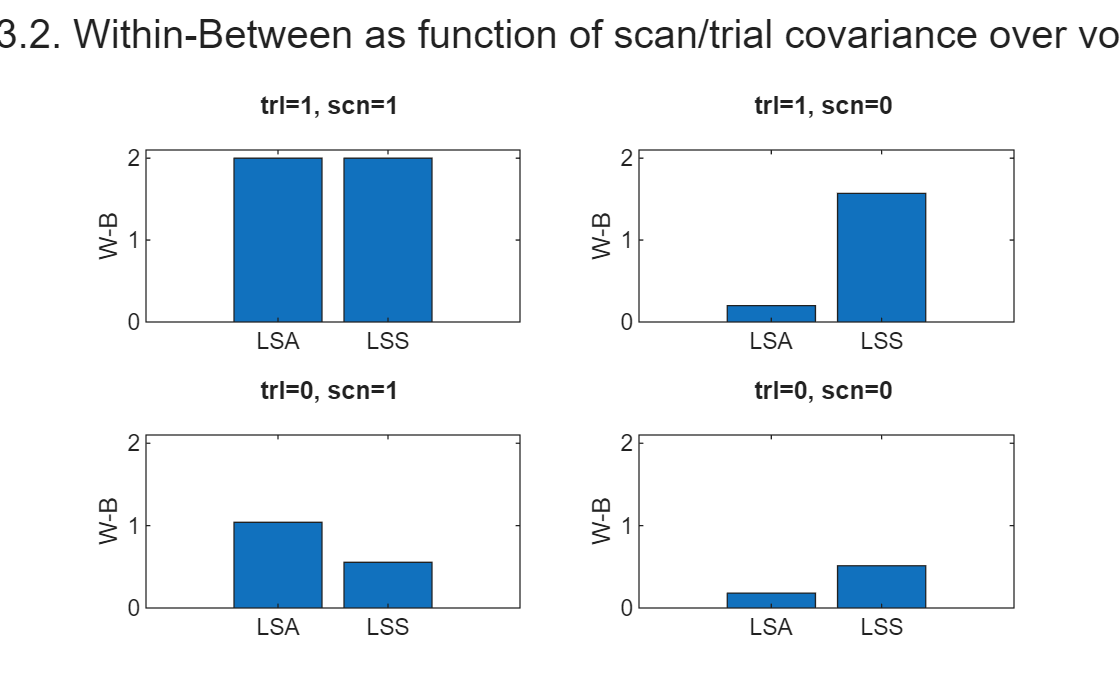

c_trl = 1 and c_scn = 1...


	 LSA:     W-B=2.00 (Z=Inf)


	 LSS:     W-B=2.00 (Z=Inf)


c_trl = 1 and c_scn = 0...


	 LSA:     W-B=0.20 (Z=11.32)


	 LSS:     W-B=1.57 (Z=61.85)


c_trl = 0 and c_scn = 1...


	 LSA:     W-B=1.04 (Z=52.51)


	 LSS:     W-B=0.55 (Z=20.57)


c_trl = 0 and c_scn = 0...


	 LSA:     W-B=0.18 (Z=10.50)


	 LSS:     W-B=0.51 (Z=17.64)



figure, sgtitle('Fig 3.2. Within-Between as function of scan/trial covariance over voxels')
rng(1)
for s=1:num_cov
    fprintf('c_trl = %d and c_scn = %d...\n', c_trl(s), c_scn(s));
    m = mean(squeeze(est_wbc(:,1,s)));
    d =  std(squeeze(est_wbc(:,1,s)));
    fprintf('\t LSA:     W-B=%3.2f (Z=%3.2f)\n', m, m/d);
    p = m; 

    m = mean(squeeze(est_wbc(:,2,s)));
    d =  std(squeeze(est_wbc(:,2,s)));
    fprintf('\t LSS:     W-B=%3.2f (Z=%3.2f)\n', m, m/d);
    p = [p; m];

    subplot(2,2,s)
    bar(p); %legend({'W-B'},'Location','NorthEast')
    set(gca,'XTickLabel',{'LSA','LSS'}); ylim([0 2.1])
    title(sprintf('trl=%d, scn=%d \n', c_trl(s), c_scn(s)))
    ylabel('W-B')
end

The top left plot of Fig 3.2 shows that when trial and scan variability covary perfectly across voxels (ie, same amount added to every voxel), the W-B value is 2, as expected (since correlation within pattern A or B is 1, and between A and B is -1, so their difference is 2). When the scan noise is independent across voxels (top right), then LSS does better than LSA, while when trial variability is independent across voxels but scan noise is perfectly correlated across voxels (bottom left), then LSA does better than LSS. The bottom right shows the case of independence across voxels for both trial and scan variability, where LSS happens to do better, though which estimator does better in general will depend on the ratio of the total variability (ie, of trl_std:scn_std, as demonstrated in the Section 2.3; a ratio that just happens to be 1 in the above example).

To understand why the covariance of trial and scan variability across voxels matters for the W-B measure, and MVPA classification more generally, let's plot just the first 16 trials of each condition (first 16 Beta estimates for condition A followed by first 16 Beta estimates for condition B), averaged across all odd and all even voxels (since patterns A and B differ in the odd/even ordering of 1s and 0s across voxels). This is shown in Fig 3.3 below for LSA and in Fig 3.4 for LSS:

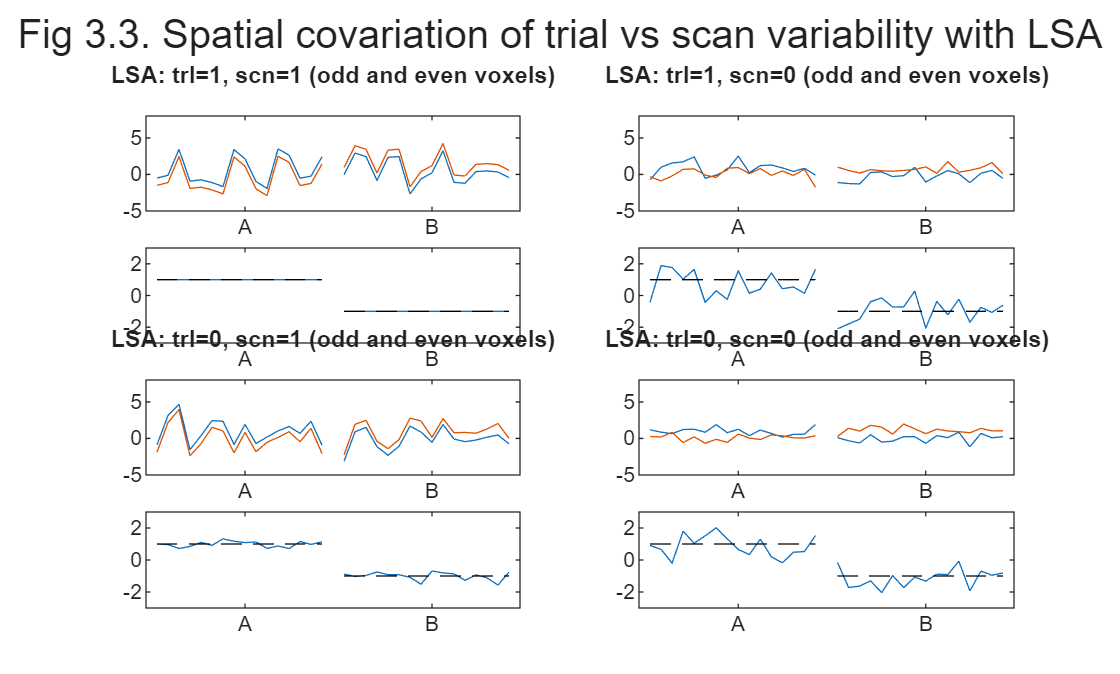

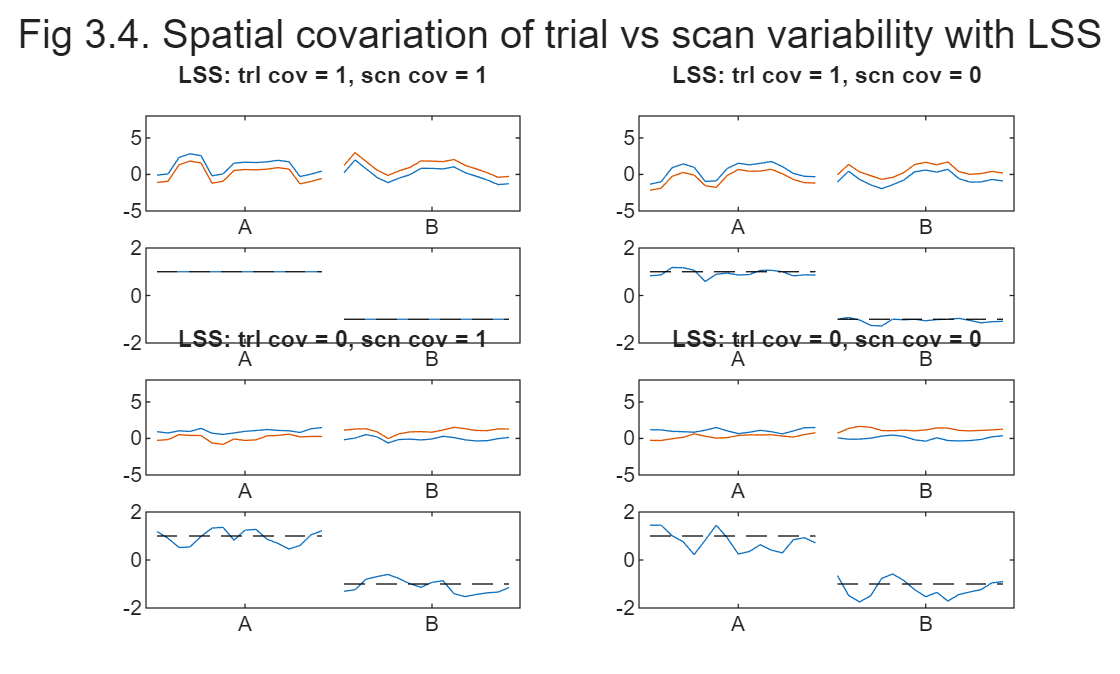

f1 = figure; sgtitle('Fig 3.3. Spatial covariation of trial vs scan variability with LSA')
f2 = figure; sgtitle('Fig 3.4. Spatial covariation of trial vs scan variability with LSS')
sp1 = [1 2 5 6];
sp2 = [3 4 7 8];
rng(1)
for s=1:num_cov
    y = gen_y(mB, SOA, trl_std, scn_std, HRF, TR, c_trl(s), c_scn(s));

    B_hat_LSA = pX_LSA * y;
    B_hat_LSA = B_hat_LSA((transient+1):(end-transient-1),:); % remove transients and constant term       
        
    show_trl = [1:16]; % Subset of trials of each condition to show
    for c = 1:2
        B_con{c} = B_hat_LSA(sv==c, :); % reassign trial number to condition
        B_con{c} = [mean(B_con{c}(show_trl,1:2:end),2) mean(B_con{c}(show_trl,2:2:end),2)]; % Average over odd/even voxels 
    end    
    mB_hat = [B_con{1}; nan(1,2); B_con{2}]; % Concatenate conditions, with NaN gap inbetween for plotting
    
    figure(f1), subplot(4,2,sp1(s))
    plot(mB_hat), axis([0 34 -5 8]), set(gca, 'XTick', [9 26], 'XTickLabel', {'A', 'B'})
    title(sprintf('LSA: trl=%d, scn=%d (odd and even voxels)\n', c_trl(s), c_scn(s)));

    subplot(4,2,sp2(s))
    plot(mB_hat(:,1) - mB_hat(:,2)), axis([0 34 -3 3]), set(gca, 'XTick', [9 26], 'XTickLabel', {'A', 'B'})
    hold on, plot([ones(max(show_trl),1); nan(1); ones(max(show_trl),1)*-1], 'k--')

    B_hat_LSS = fit_lss(X_LSA, v, y, transient);

    for c = 1:2
        B_con{c} = B_hat_LSS(sv==c, :); % reassign trial number to condition
        B_con{c} = [mean(B_con{c}(show_trl,1:2:end),2) mean(B_con{c}(show_trl,2:2:end),2)]; % Average over odd/even voxels 
    end 
    mB_hat = [B_con{1}; nan(1,2); B_con{2}]; % Concatenate conditions, with gap inbetween for plotting
    
    figure(f2), subplot(4,2,sp1(s))
    plot(mB_hat), axis([0 34 -5 8]), set(gca, 'XTick', [9 26], 'XTickLabel', {'A', 'B'})
    title(sprintf('LSS: trl cov = %d, scn cov = %d\n', c_trl(s), c_scn(s)));

    subplot(4,2,sp2(s))
    plot(mB_hat(:,1) - mB_hat(:,2)), axis([0 34 -2 2]), set(gca, 'XTick', [9 26], 'XTickLabel', {'A', 'B'})
    hold on, plot([ones(max(show_trl),1); nan(1); ones(max(show_trl),1)*-1], 'k--')
end

Fig 3.3 and Fig 3.4 have the same 2x2 layout of the 4 cases as in Fig 3.2 (i.e., from perfect covariance across voxels for both trials and scans in top left, to total independence in bottom right), but within each one if the 4 cells is plotted the odd and even voxels separately (in red and blue in top plot) and below that is plotted their difference, along with black dashed lines for the mean pattern values. The key idea is that better classification performance is achieved when the odd-even voxel difference between A and B is clearer, ie the variability across trials of this difference is small within a condition, relative to the mean difference between conditions (ie, 2). In other words, what matters for pattern classification is not the overall scaling across all voxels, but the relative difference between voxels. 

For LSA (Fig 3.3), when the scan noise is identical across voxels (bottom left cell), while the Beta estimates vary considerably across trials for both red (even) and blue (odd) voxels, they vary in the same way, so that the difference between red and blue in the plot below does not vary much between trials of the same type, so that the mean difference between A and B trial types is large relative to the variance within types. This means A and B will be well classified. For the two cells on the right, when scan noise is independent across voxels, the red and blue voxels vary differently, so their difference varies a lot within trials of the same type, which will reduce the ability to classify trials as A or B.

Conversely, for LSS (Fig 3.3), when the trial variability is identical across voxels (top right cell), the variability of the difference is smaller (ie classification is better) than when the trial variability is independent across voxels (bottom two cells).

Thus in summary, whether LSS or LSA is a better estimator for MVPA depends on not just the ratio of trial variance to scan variance, but also the relative degree of covariance across voxels of trial variability and scan variability. While we may not always know or be able to measure these ratios independently, there might be a priori reason to suspect whether each ratio is bigger or smaller than one.

Finally, note that the presence of spatially-correlated noise every TR is likely to be the main reason why MVPA has been performed successfully even with short SOAs of a few seconds: even though estimating the mean across voxels for individual trials at such short SOAs is very inefficient (Section 1.1), one can still estimate relative differences across voxels (i.e, patterns) well.

## Common Questions 

Below are a collection of various related questions that are often raised.

### I. What is the minimum number of events I need? 

Unfortunately, there is no answer to this, other than "the more, the better". The statistical power depends on the effect size and variability, and this is normally unknown. People who say "you cannot do an event-related fMRI analysis with less than N events" are talking rubbish, unless they have a specific effect size in mind (which is a function of the experimental effect, the brain region, the scanner strength, the sequence optimization, etc, etc...). Note it is even possible that fewer trials are required (for a given power) than for an equivalent contrast of behavioural data (the noise in, e.g, response times (RTs) may exceed that of the BIR in a specific cortical region contributing to those RTs). Furthermore, it is not even the number of events per se that is relevant: it is also the SOA and event-ordering (as demonstrated above).

### II. Doesn't shorter SOAs mean more power simply because of more trials?

It is not simply the number of trials: the temporal distribution of those trials is vital (as explained above). Thus 400 stimuli every 3s is LESS efficient than 40 stimuli every 30s for detecting a single event-related response versus interstimulus baseline (since a fixed SOA of 3s produces little experimental variability after convolution by the BIR). Indeed, 200 stimuli occurring with a 50% probably every 3s (i.e, pseudorandomly mixed with 200 null events) is much more efficient than either, though note again, if you have a limited number of trials (eg, stimuli), but plenty of scan time, long SOAs can be more efficient than short SOAs simply by virtue of allowing more volumes to be acquired in total (ie longer experiment, ie more df's). The efficiency arguments above are predicted on having a fixed scan time, over which an effectively unlimited number of trials can be distributed (eg, a sufficiently large stimulus set).

### III. What is the maximum number of conditions I can have?

A common interpretation of the general advice above - not to contrast trials that are too far apart in time - is not to design experiments with too many experimental conditions. More conditions necessarily mean that replications of a particular condition will be further apart in time. However, the critical factor is not the number of conditions per se, but the specific contrasts performed over those conditions. For pairwise comparisons of only 2 of, say, 8 blocked conditions (e.g, a [1 -1 0 0 0 0 0 0] contrast), the above caveat would apply: if there were equal numbers of blocks of each condition, blocks longer than 12.5s (100s/8) are likely to entail a substantial loss of signal when using a highpass cutoff of 0.01Hz. However, this caveat would not apply if the contrasts of interest included ("spanned") all 8 conditions, as would be the case if the experimenter were only interested in the two main effects and the interaction within a 2x4 factorial design (i.e, contrasts like [1 1 1 1 -1 -1 -1 -1] ). If you must compare only a subset of many such blocked conditions, you should consider presenting those blocks in a fixed order, rather than random or counter-balanced order, which will minimise the time between replications of each condition, i.e, maximise the frequency of the contrast (as always, assuming no psychological caveats with a non-random ordering of conditions). 

### IV. Should I use null events? 

Null events are simply a convenient means of achieving a stochastic distribution of SOAs, in order to allow estimation of the response vs. interstimulus baseline, by randomly intermixing them with the events of interest. However, the "baseline" may not always be meaningful. It may be well-defined for V1, in terms of visual flashs versus a dark background. It becomes less well-defined for "higher" regions associated with cognition however, because it is often unclear what these regions are "doing" during the interstimulus interval. The experimenter normally has little control over this. Also note that the baseline is only as good as it controls for aspects of the events of interest (e.g, a fixation cross hair does not control for visual size when used as a baseline for words). Moreover, it does not control for the fact that the events are impulsive (rapid changes) whereas the baseline is sustained (and may entail, e.g, adaptation or reduced attention). For this reason, it is often better to forget about baseline and add an extra low-level control event instead.

Another problem with null events is that, if they are too rare (e.g, less than approx 33%), they actually become "true" events in the sense that participants may be expecting an event at the next SOAmin and so be surprised when it does not occur (the so-called "missing stimulus" or "omission" effect that is well-known in ERP research). One solution is to replace randomly intermixed null events with periods of baseline between blocks of events. This will increase the efficiency for detecting the common effect vs. baseline, at a slight cost in efficiency for detecting differences between the randomised event-types within each block.

Yet another problem is that sometimes the unpredictability of the occurrence of true events (caused by the randomly intermixed null events) can cause delayed or even missed processing of the events of interest. If participants must respond quickly to each event, for example, it is often advantageous if they know roughly when each event will occur, and so prepare for it.

So to answer the question, null events are probably only worthwhile if 1) you think the mean activity during the constant interstimulus interval is meaningful to contrast against, 2) you don't mind null events being reasonably frequent (to avoid "missing stimulus" effects) and 3) you don't mind the stimulus occurrence being unpredictable (as far as the participant is concerned). Having said this, some form of baseline can often serve as a useful "safety net" (e.g, if you fail to detect differences between two visual event-types of interest, you can at least examine V1 responses and check that you are seeing a basic evoked response to both event-types; if not, you can question the quality of your data or accuracy of your model). But then again, that baseline might be better estimated from "blocked" periods of baseline, rather than randomly intermixed null events.

Remember that randomly intermixed null events are not NECESSARY to analyse event-related responses if you have a rough idea what form the BOLD impulse response takes. If however you do want to estimate the precise shape of the BIR, then they do become necessary, as detailed in the Section on Detection Power vs Estimation Efficiency.

### V. Should I generate multiple random designs and choose the most efficient one?

This is certainly possible, though be wary that such designs are likely to converge on designs with some structure (e.g, blocked designs, given that they tend to be optimal, as explained above). This may be problematic if such structure affects participants' behaviour (particularly if they notice the structure). Note however that there are software tools available that optimise designs at the same time as allowing users to specify a certain level of counterbalancing (to avoid fully blocked designs): e.g, [[Wager & Nichols, 2003]](https://doi.org/10.1016/s1053-8119(02)00046-0), or the ["OptSeq"](http://surfer.nmr.mgh.harvard.edu/optseq/) program developed by Doug Greve.

### VI. Should I treat my trials as events or epochs?

If all trials are of the same duration, and that duration were below ~2s, then they can be effectively modelled as events (i.e, delta functions with zero duration). This is because, after convolution with an HRF, a difference in the duration of a trial causes a difference in the scaling (size) of the predicted response, but has little effect on its shape (see Fig 4 below, where the numbers refer to different durations of neural activity, and the correlations are shown for the resulting BIRs with the BIR from the initial duration of 0.2s). Since it is the scaling of the predicted response that is being estimated in the statistical models discussed above, changing the duration of all trials (from 0-2s) changes the size of the resulting parameter estimates, but has little effect on the statistical inferences (given that statistics are scaled by std of those estimates). This is despite the fact that the efficiency, as calculated by equation above, will increase with longer durations (ie, with greater scaling of the regressors in X). This increase is correct, in the sense that a larger signal would be easier to detect in the presence of the same noise, but misleading in the sense that our statistics depend on the ratio of signal to noise, and the data themselves are unaffected by how we model the trials. 

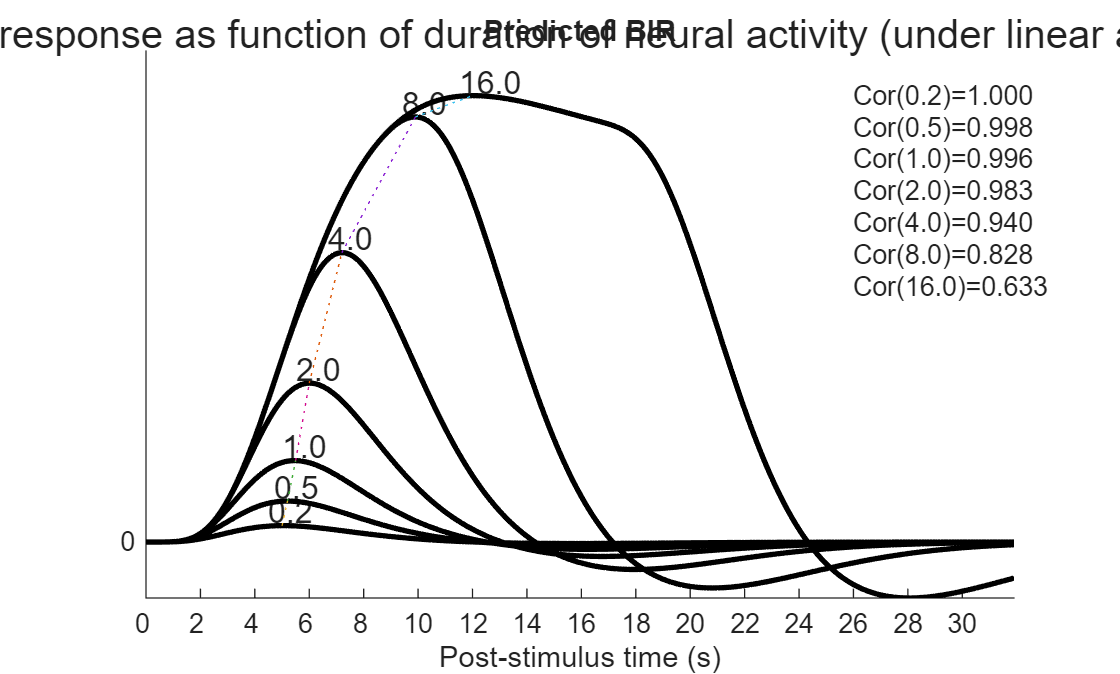

dt = 0.1; HRF = canonical_HRF(dt);
pst = dt*[1:length(HRF)]' - dt;
z = zeros(size(pst));

durations = [0.2 0.5 1 2 4 8 16];

figure, sgtitle('Fig 4. BOLD response as function of duration of neural activity (under linear assumptions)')
hold on
BIRs = nan(length(pst),length(durations));
m = nan(size(durations)); t = m; c = ones(size(durations));
for d = 1:length(durations)
    u = z;
    u(1:round(durations(d)/dt)) = dt;
    BIRs(:,d) = lconv(u,HRF);
    %plot(pst,u,'LineWidth',1,'Color','k');
    plot(pst,BIRs(:,d),'LineWidth',2,'Color','k');
    [m(d),t(d)] = max(BIRs(:,d));
    t(d) = pst(t(d));
    text(t(d)-0.5, m(d)+0.16, sprintf('%2.1f',durations(d)),'FontSize',12);
    if d>1; 
         l=line([t(d-1) t(d)], [m(d-1) m(d)]); set(l,'LineStyle',':'); 
         c(d)=corr(BIRs(:,d), BIRs(:,d-1)); 
    end
end
axis([0 max(pst) min(BIRs(:)) 1.1*max(BIRs(:))])
set(gca,'YTick',[0],'XTick',[0:2:max(pst)],'XTickLabel',[0:2:max(pst)])
xlabel('Post-stimulus time (s)'); title('Predicted BIR')
% Show correlations
for d = 1:length(durations); 
    text(26, (1 - (d-1)/(2*length(durations)))*max(BIRs(:)), sprintf('Cor(%2.1f)=%4.3f',durations(d),c(d)));
end

For longer duration trials, the response begins to plateau, meaning that an "epoch model" can be a better model. More important however, is the case of trials that vary in duration from trial to trial within a condition, or across conditions. To appreciate this, consider trials consisting of a stimulus followed by a response. Whether these trials are better modelled as events, or as epochs of different durations (e.g, with duration equal to the RT for each trial), is debatable. For example, if the stimulus duration were constant and only RTs varied, then the activity in V1 may not be expected to vary with RT, so an "event model" might fit better (and in this case, the parameter estimate can be interpreted as the BOLD response ''per trial''). For activity in premotor cortex on the other hand, greater activity might be expected for trials with longer RTs, so a "varying-epoch model" might fit better (and in this case, the parameter estimate can be interpreted as the BOLD response ''per unit time''). So the answer depends on your assumptions about the duration of neural activity in the particular brain regions of interest (and one solution can be to model each trial as both a delta function at trial onset AND an epoch of trial duration, assuming the range of trial durations is sufficient to decorrelate the resulting regressors to some extent; see also [[Mumford et al., 2023]](https://doi.org/10.1038/s41562-023-01760-0)). 

## Glossary

Here are the meanings of the most common variables used in code above:

u = neural timeseries (every dt) of assumed neural activity (e.g., delta function every SOA)

v = vector of trial-types every SOAmin (e.g., 12--2-1--112), regardless of their timing

y = fMRI timeseries, ie BOLD response every TR (possibly with noise added)

X = design matrix (TRs by regressors/predictors)

pX = pseudo-inverse of X (for OLS estimation)

B = parameter of X (one per column of X)

B_hat = estimated parameter value

c = contrast (vector for T-contrast; matrix for F-contrast)

## General Functions

function HRF = canonical_HRF(dt); 
% Generate a canonical HRF (based on SPM's difference of two gamma functions)
    p   = [6 16 1 1 6 0 32];
    u   = [0:ceil(p(7)/dt)] - p(6)/dt;
    HRF = gampdf(u,p(1)/p(3),p(3)/dt) - gampdf(u,p(2)/p(4),p(4)/dt)/p(5);
    HRF = HRF(1:(end-1))'/max(HRF);
end

function s = lconv(u,h);
% convolve each column of u by each column of h (and trim left)
    [n,Np] = size(u);
    Nq     = size(h,2);
    s      = zeros(n,Np*Nq);
    for p = 1:Np
        for q = 1:Nq
            tmp = conv(u(:,p),h(:,q));
            s(:,(p-1)*Nq + q) = tmp(1:n);
        end
    end
end

function [a,f] = amp_spec(t, dt, padding);
% Amplitude spectrum for timeseries sampled every dt (ignoring mean)
    %t = detrend(t,0);
    if nargin < 3
        padding = 0;
    end
    t = [zeros(padding,1); t; zeros(padding,1)]; % pad to handle edge effects and increase freq res
    a = abs(fft(t));
    f = [1:(length(a)/2)-1];
    f = (1/(2*dt))*f/max(f);
    a = a(1:length(f));
end

function s = genstim(TM,N);
% Use a transition matrix TM to generate sequence of Ni stimuli
    
    Nh = length(size(TM))-1; % length of history (ie dimensionality of TM)
    Np = size(TM,Nh+1);
    
    subs = cell(1,Nh+1); subs(:)={':'};
    s=[];
    for n=1:N
        pp = zeros(1,Np);
        for p=1:Np
            subs{end} = p;
            ps = TM(subs{:});
            pp(p) = mean(ps(:));
        end
        s(end+1) = selectp(pp);

        if ~isnan(s(end))
            for h=1:(Nh-1)
                subs{h} = subs{h+1};
            end
            subs{end-1} = s(end);
        end
    end
end

function r = selectp(pp);
% Select one outcome from set of probabilities pp (NA if nothing)    
    r = rand(1);
    
    if r>sum(pp)
        r = nan;
    else
        pp = cumsum(pp);
        r = pp - r;
        r(find(r<0)) = 1;
        [~,r] = min(r);
    end
end

function [X,K,KX] = gen_X(stim, SOA, BFs, TR, H0);
% Generate design matrix for stimulus train given SOA, temporal basis
% functions BFs, TR and highpass cut-off H0 in Hz
    dt = 0.1; 
    if nargin < 5
        H0 = 0.01;
        if nargin < 4
            TR = 1;
            if nargin < 3
                BFs = canonical_HRF(dt);
            end
        end
    end

    us = unique(stim(~isnan(stim)));
    num_types = length(us);             % Number of conditions
    num_smp = length(stim)*SOA/dt;
    
    u = zeros(num_smp,num_types);   % hypothetical neural activity
    for s = 1:num_types
        ind = find(stim==us(s))-1;
        u(round(ind*SOA/dt)+1,s) = 1;
    end

    s = lconv(u,BFs);                   % predicted BOLD signal timeseries

    TR_bins = round(TR/dt);
    X = s(round(TR_bins/2):TR_bins:end,:);   % downsample each TR (at middle of TR, eg middle slice in time)
    
    N = size(X,1);
    K = dct(N, H0, TR); % Highpass filter
    KX = (eye(N) - K*pinv(K))*X;
end

function HPF = dct(N, H0, TR);
% Create discrete cosine transform set up to highpass cutoff H0 Hz
    n = (0:(N-1))';
    K = fix(2*(N*TR)*H0+1);

    HPF(:,1)     = ones(size(n,1),1);
    for k=2:K
        HPF(:,k) = sqrt(2/N)*cos(pi*(2*n+1)*(k-1)/(2*N));
        HPF(:,k) = HPF(:,k)/std(HPF(:,k));
    end
end

function xo = orthog(x,y);
    B = pinv(y)*x;
    R = eye(size(y,1)) - y*pinv(y);
    xo = R*x;
end

function [y,B] = gen_y(mB, SOA, trl_std, scn_std, HRF, TR, trl_cov, scn_cov);
% Generate matrix of fMRI data (y) across scans (rows) and voxels (columns)
% These come from the matrix "Betas" of patterns across voxels for each 
% trial, to which variability is added across trials, before convolving 
% with an HRF, down-sampling every TR, and adding noise each TR. 
% Both trial and scan variability are drawn from multivariate Gaussians 
% with std of "trl_std" and "scn_std" respectively, and covariance across 
% voxels of "trl_cov" and "scn_cov" respectively. 

    dt = 0.1;
    if nargin < 8
        scn_cov = 0;
        if nargin < 7
            trl_cov = 0;
            if nargin < 6
                TR = 1;
                if nargin < 5                   
                    if TR < dt; error('TR must be greater than 0.1s'); end
                    HRF = canonical_HRF(dt);
                end
            end
        end
    end

    num_trl = size(mB,1);
    num_vox = size(mB,2);

    trl_cov = trl_cov*ones(num_vox) + (1-trl_cov)*eye(num_vox); 

    B = mB + trl_std*mvnrnd(zeros(num_trl, num_vox), trl_cov); 

    num_TRs = round(num_trl*SOA/TR);
    TRs  = round(TR/dt);
    SOAs = round(SOA/dt);

    u = zeros(num_TRs*TRs, num_vox);

    u(1:SOAs:(num_trl*SOAs), :) = B;

    y = lconv(u,HRF);

    y = y(round(TRs/2):TRs:(num_TRs/dt), :);

    scn_cov = scn_cov*ones(num_vox) + (1-scn_cov)*eye(num_vox); 

    y = y + scn_std*mvnrnd(zeros(num_TRs, num_vox), scn_cov); 
end

function [B_hat, sv] = fit_lss(X_LSA, v, y, transient);
% Fits LSS-N model (where N = number of conditions)
    N = size(X_LSA,2)-1; % assumes last column is constant
    B_hat = nan(N-(2*transient), size(y,2));

    uc = unique(v);
    nc = length(uc);
    X_all = cell(1,nc);
    for c = 1:nc
        X_all{c} = sum(X_LSA(:,v==uc(c)),2);
    end
    
    for t = 1:size(B_hat,1)
        X = X_LSA(:,transient+t); % trial of interest

        Xr = []; % all other trials of same or different type
        for c = 1:nc
            if v(transient+t) == uc(c)
                Xr = [Xr X_all{uc(c)}-X];
            else
                Xr = [Xr X_all{uc(c)}];
            end
        end

        X = [X Xr X_LSA(:,N+1)];
        B = pinv(X)*y;
        B_hat(t,:) = B(1,:);
    end

    sv = v((transient+1):(end-transient));
end

function s = wbc(B);
% Calculate mean within vs between correlation across voxels for 
% cell array of Betas from two conditions
    wc = 0;
    for c = 1:2
        cor = corr(B{c}');
        ind = find(triu(cor,1));
        wc = wc + mean(cor(ind));
    end
    wc = wc/2;

    cor = corr(B{1}', B{2}');
    ind = find(triu(cor,1));
    bc = mean(cor(ind));

    s = wc - bc;
end